# Trabalho final de "Propagação de ondas eletromagnéticas"

**Análise e exemplo da ITU-R-P-1546-6**

Arthur - 12111ETE021

Mateus Flausino - 

Olavo Caetano Inácio - 11911ETE012

## 1. Objetivos da Norma

The role of the Radiocommunication Sector is to ensure the rational, equitable, efficient and economical use of the radiofrequency spectrum by all radiocommunication services, including satellite services, and carry out studies without limit  of frequency range on the basis of which Recommendations are adopted. The regulatory and policy functions of the Radiocommunication Sector are performed by World and Regional  Radiocommunication Conferences and Radiocommunication Assemblies supported by Study Groups

This Recommendation describes a method for point-to-area radio propagation predictions for terrestrial  services in the frequency range 30 MHz to 4 000 MHz. It is intended for use on tropospheric radio circuits  over land paths, sea paths and/or mixed land-sea paths up to 1 000 km length for effective transmitting antenna  heights less than 3 000 m. The method is based on interpolation/extrapolation from empirically derived  field-strength curves as functions of distance, antenna height, frequency and percentage time. The calculation  procedure also includes corrections to the results obtained from this interpolation/extrapolation to account for  terrain clearance and terminal clutter obstructions.

## Definindo constantes

skip_step_9         = 0;
skip_step_10        = 0;
skip_step_11        = 1; %#ok<NASGU> 
skip_step_8_1_5     = 0;
sikp_to_step_17     = 0;

skip_step_12        = 0; %AQUI AINDA PRECISA VER ONDE USA
skip_step_15        = 0;
skip_step_16        = 0;
skip_step_8_1_6     = 0;

## Entrada das variáveis

caminho_misto           = true;
primeira_parte          = "Cold Sea"; % No caso,a  primeira parte será a única, porque não existe caminho misto. O nome foi usado para facilitar verificações
wanted_time_percentage  = 1
frequency_mhz           =30
distancia               =475.8; % Distância em quilômetros

tca                     = true;
ha                      = 20; % Altura transmissor 
h2                      = 20; % Altura receptor

heff                    = 10; % Altura média do terreno entre 3 e 15 km

Como  para esse exemplo não estamos usando informações de terreno, não estamos fazendo o cálculo de heff, estamos colocando ele como um parâmetro de entrada.

htter                   = 20; %Altura transmissor acima do nível do mar
hrter                   = 20; %Altura transmissor acima do nível do mar

incluir_perdas          = true;

if(tca == 1)
    skip_step_12 = 0;
    theta_eff           =29.88
    tca_receptor        =0.55
else
    skip_step_12 = 1
end
if caminho_misto
    primeira_parte      = "Cold Sea";
    segunda_parte       = "Cold Sea";
    ponto_troca         =0 
    skip_step_11 = 0;

    if primeira_parte ~= "land" && segunda_parte == "land"
        dsea = ponto_troca;
    elseif segunda_parte ~= "land" && primeira_parte == "land"
        dsea = distancia - ponto_troca;
    elseif primeira_parte ~= "land" && segunda_parte ~= "land"
        dsea = distancia;
    else
        dsea = 0;
    end
    
    dland = distancia - dsea;
end
if primeira_parte == "land" || segunda_parte == "land"
    tipo_terreno        = "Urban"; %Em caso de caminho por terra
    clutter_height_R2   = 20; %Altura da obstrução do receptor
    clutter_height_R1   = 20; %Altura da obstrução do transmissor

    if(clutter_height_R1 == 0)
        skip_step_15 = 1;
    end

    if(distancia >= 1)
        skip_step_16 = 1;
    end
else
    skip_step_15 = 1;
end

If the required horizontal distance is 0.04 km or less, start at Step 17. If the required horizontal  distance is greater than 0.04 km and less than 1 km, steps 1 to 16 should be followed with d set to  1 km, after which the remaining steps should be followed with d set to the required value. Otherwise all steps should be followed with d set to the required value.

if distancia < 1
    if distancia < 0.04
        sikp_to_step_17 = 1;
    end
    distancia = 1;
end

if distancia <= 3
    h1 = ha
elseif distancia > 3 && distancia < 15
    h1 = ha + (heff-ha)*(distancia-3)/12
elseif distancia > 15
    h1 = heff
end

## Resultados da simulação

## IMPLEMENTAÇÃO DA NORMA

## Passo 2. Verificação dos limites de interpolação da porcentagem

Step 2: For any given percentage of time (in the range 1% to 50% time) determine two nominal time  percentages as follows: – wanted time percentage > 1 and < 10, the lower and higher nominal percentages are 1 and 10,  respectively; – wanted time percentage > 10 and < 50, the lower and higher nominal percentages are 10 and  50, respectively. If the required percentage of time is equal to 1% or 10% or 50%, this value should be regarded as the  lower nominal percentage time and the interpolation process of Step 10 is not required.

if wanted_time_percentage > 1 && wanted_time_percentage < 10
    lower_percentage = 1
    higher_percentage = 10

elseif wanted_time_percentage > 10 && wanted_time_percentage < 50 
    lower_percentage = 10
    higher_percentage = 50

elseif wanted_time_percentage == 1 || wanted_time_percentage == 10 || wanted_time_percentage ==50
    lower_percentage = wanted_time_percentage
    skip_step_10 = 1
end

## Passo 3. Verificação dos limites de interpolação da frequência

For any wanted frequency (in the range 30 to 4 000 MHz) determine two nominal frequencies  as follows: – where the wanted frequency < 600 MHz, the lower and higher nominal frequencies are 100  and 600 MHz, respectively; – where the wanted frequency > 600 MHz, the lower and higher nominal frequencies are 600  and 2 000 MHz, respectively.

if frequency_mhz < 600
    lower_frequency = 100
    higher_frequency = 600

else
    lower_percentage = 600
    higher_percentage = 2000
end

If the wanted frequency equals 100 or 600 or 2 000 MHz, this value should be regarded as the lower nominal frequency and the interpolation/extrapolation process of Step 9 is not required

if frequency_mhz == 100 || frequency_mhz == 600 || frequency_mhz == 2000 
    lower_frequency = frequency_mhz
    skip_ste_9 = 1
end

## Passo 4. Dados para regressão da distância

% Step 4: Determine the lower and higher nominal distances from Table 1 closest to the required 
% distance. If the required distance coincides with a value in Table 1, this should be regarded as the 
% lower nominal distance and the interpolation process of Step 8.1.5 is not required.

distancesKm_table = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100 110 120 130 140 150 160 170 180 190 200 225 250 275 300 325 350 375 400 425 450 475 500 525 550 575 600 625 650 675 700 725 750 775 800 825 850 875 900 925 950 975 1000];

for i = 1:length(distancesKm_table)
    if distancia == distancesKm_table(i)
        skip_step_8_1_5 = 1;
        return
    end

    if distancia > distancesKm_table(i) && distancia < distancesKm_table(i+1)
        lower_distance = distancesKm_table(i)
        highest_distance = distancesKm_table(i+1)
        return
    end
end

## Passo 8. Cálculo do Campo

### 8.1 Definindo Índice para os caminhos

if(primeira_parte == "land")
    path = 1;
elseif (primeira_parte == "cold_sea") %nas tabelas possue o sea
    path = 3;
else
    path = 4;
end

### 8.2 Verificação dos limites de interpolação da altura da antena transmissora

height1smeters_table = [10 20 37.5 75 150 300 600 1200];

if ((ismember (h1,height1smeters_table)) == true)
        lower_height = h1;
        skip_step_8_1_6 = 1;
    else
        for i = 1:length(height1smeters_table)
            h1 > height1smeters_table(i) && h1 < height1smeters_table(i+1)
            lower_height = height1smeters_table(i)
            highest_height = height1smeters_table(i+1)
        end     
end

### 8.3 Calculando o campo para altura da antena transmissora maior que 10 metros

if (h1 >= 10)

    %Calcula o campo 

    E = calculate_field_strength(lower_distance,lower_height,lower_frequency,path, lower_percentage)

### 4.4 Calculando o campo para altura da antena transmissora menor que 10 metros

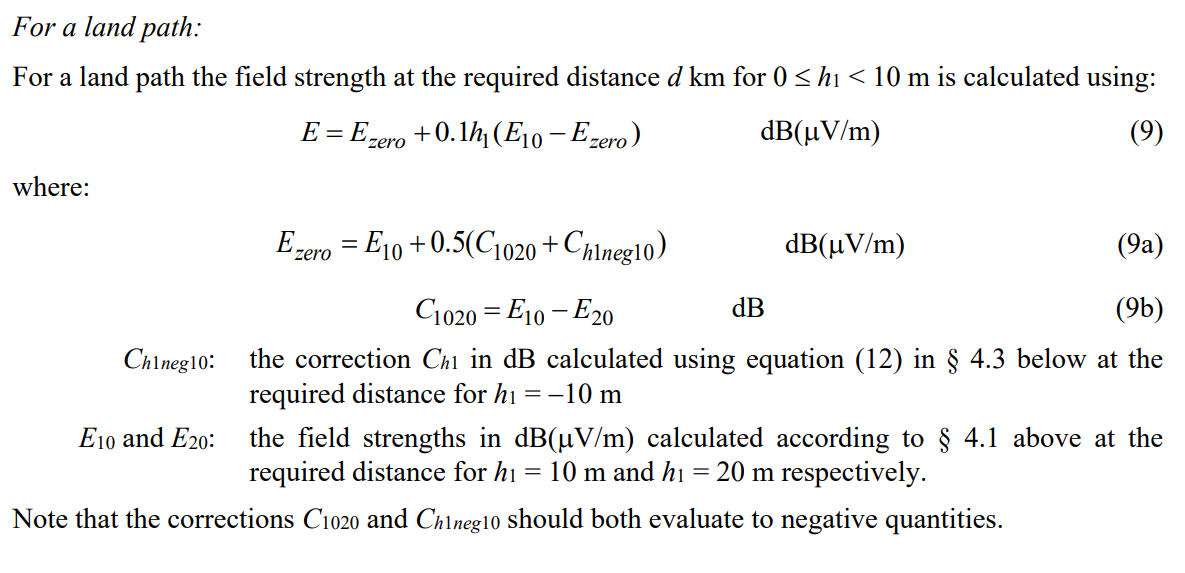

else
    E10 = calculate_field_strength(lower_distance,10,lower_frequency,path, lower_percentage)
    E20 = calculate_field_strength(lower_distance,20,lower_frequency,path, lower_percentage)  

    v = V(lower_frequency,-10);

    if v>-0.7806
        J = 6.9+20*log10(sqrt((v-0.1)^2+1)+v-0.1);  % equ'n (12a)
    else
        J=0;
    end

    Ch1neg10 = 6.03-J;                          % equ'n (12)
    C1020 = E10 - E20;                          % equ'n (9b)
    Ezero = E10 + 0.5*(C1020 + Ch1neg10);       % equ'n (9a)

    if (path ==1)  %Land
        if (h >= 0)
            E = Ezero + 0.1*h1*(E10 - Ezero);
        elseif h1 < 0          
            v = V(lower_frequency,h1);
            if v>-0.7806
                J = 6.9+20*log10(sqrt((v-0.1)^2+1)+v-0.1);  % equ'n (12a)
            else
                J=0;
            end
            E = Ezero+6.03-J;  % equ'n (12)
            return        
        end

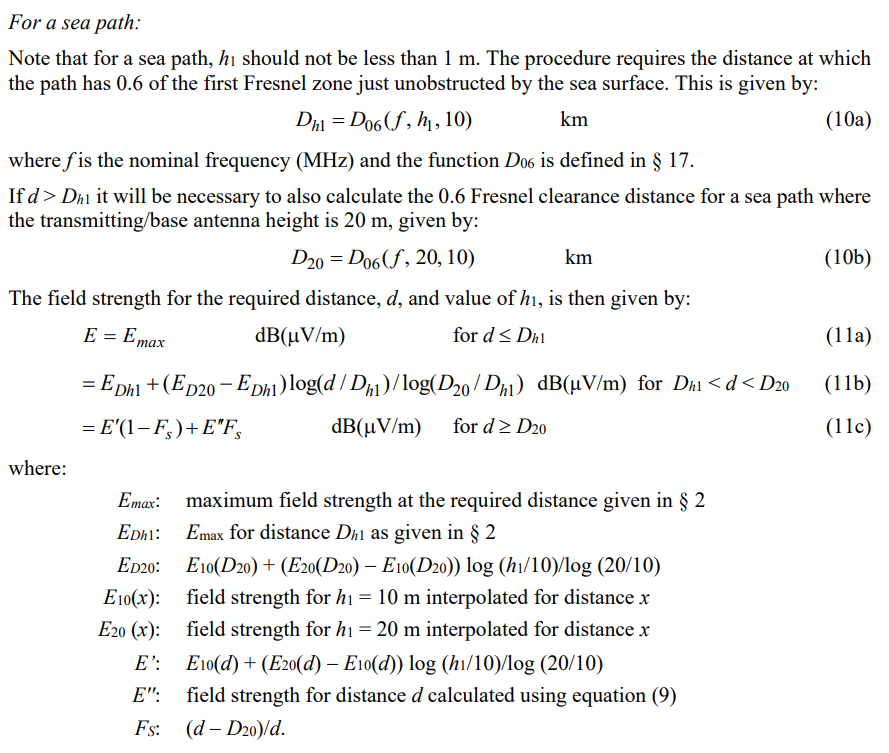

    else   %Sea
        Dh1 = D06(lower_frequency,h1,10);             % equ'n (10a)
        D20 = D06(lower_frequency,20,10);             % equ'n (10b)
        if d <= Dh1
            E = Step_19a(lower_percentage, 0, distancia);                   % equ'n (11a)
            return
        elseif (distancia >Dh1) && (distancia < D20)
            
            E10D20 = calculate_field_strength(D20,10,lower_frequency,path, lower_percentage)
            E20D20 = calculate_field_strength(D20,20,lower_frequency,path, lower_percentage)
            
            ED20 = E10D20+(E20D20 - E10D20)*log10(h1/10)/log10(20/10);
            %EDh1 = Emax(t, dland, dsea);
            EDh1 = Step_19a(lower_percentage, 0, Dh1);
            E=EDh1+(ED20 - EDh1)*log10(d/Dh1)/log10(D20/Dh1);
            return
        elseif d >= D20
            E1 = E10+(E20-E10)*log10(h1/10)/log(20/10);
            v = V(lower_frequency,-10);
            if v>-0.7806
                J = 6.9+20*log10(sqrt((v-0.1)^2+1)+v-0.1);  % equ'n (12a)
            else
                J=0;
            end
            Ch1neg10 = 6.03-J;                          % equ'n (12)
            C1020 = E10 - E20;                          % equ'n (9b)
            Ezero = E10 + 0.5*(C1020 + Ch1neg10);       % equ'n (9a)
            E2 = Ezero + 0.1*h1*(E10 - Ezero);          % equ'n (9)
            Fs = (d - D20)/d;
            E = E1*(1-Fs)+E2*Fs;                        % equ'n (11c)
            return
        end
    end
end

## 5. Interpolações

### 5.1 Interpolação da distâcia

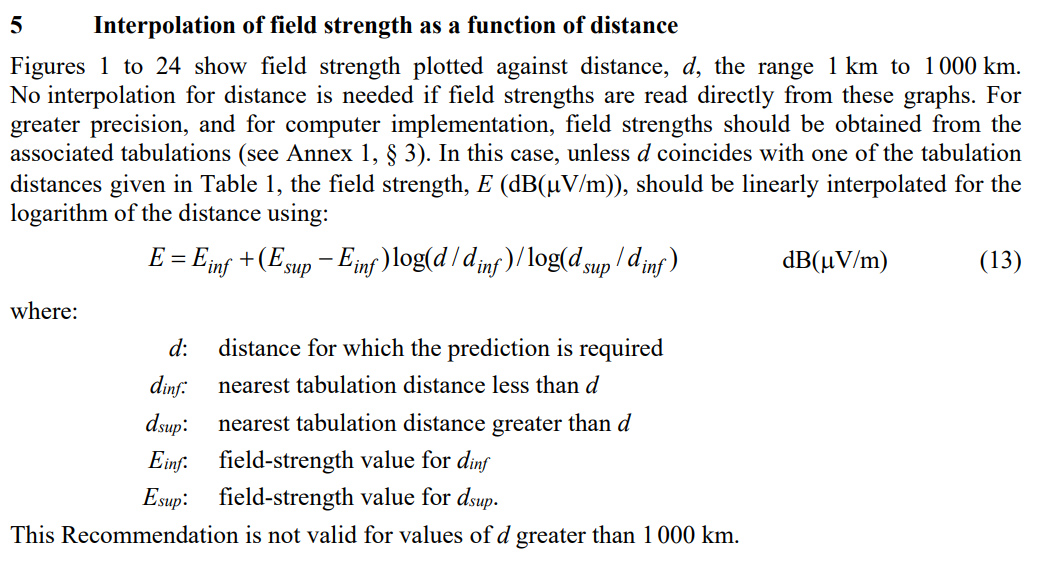

if(skip_step_8_1_5 == 0)
    Esup = calculate_field_strength(highest_distance,lower_height,lower_frequency,path, lower_percentage)
    E = E + (Esup - E)*(log10(distancia/lower_distance)/log10(highest_distance/lower_distance))
end

### 5.2  Interpolação da altura

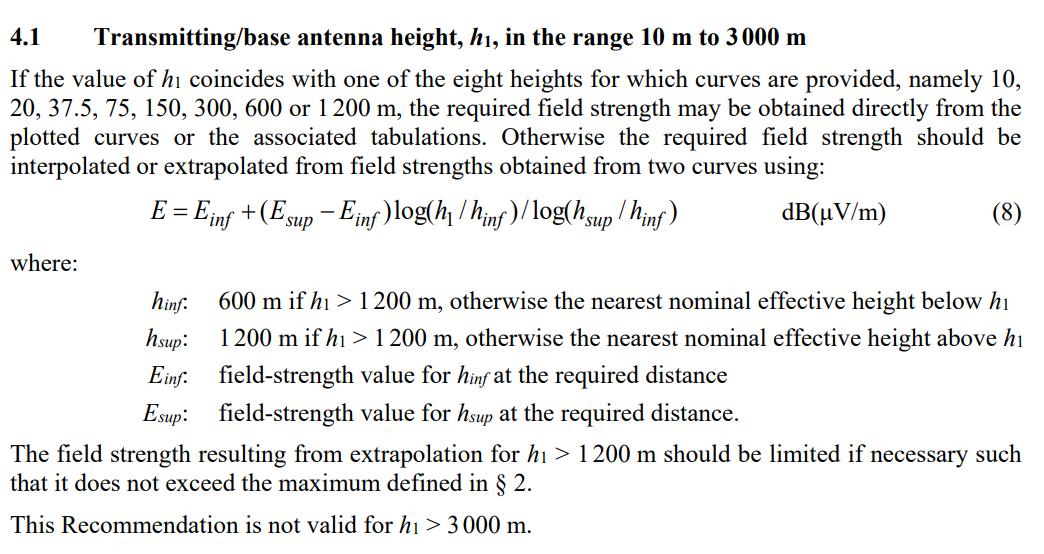

if(skip_step_8_1_6 == 0)
    Esup = calculate_field_strength(lower_distance,highest_height,lower_frequency,path, lower_percentage)
    if(h1>1200)
        hinf = 600
        hsup = 1200
    else
        hinf = lower_height
        hsup = highest_height
    end
    E = E + (Esup - E) * (log10(h1/hinf)/log10(hsup/hinf))
end

### 5.3  Interpolação da frequência

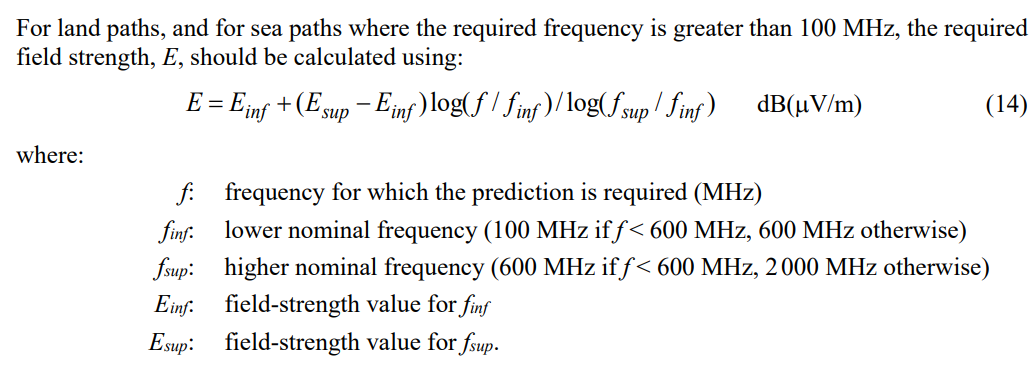

if (frequency_mhz >= 100)
        if(frequency_mhz<600)
            finf = 100
            fsup = 600
        else
            finf = 600
            fsup = 2000
        end
    Esup = calculate_field_strength(lower_distance,lower_height,fsup,path, lower_percentage)
    E = E + (Esup - E) * (log10(frequency_mhz/finf)/log10(fsup/finf))

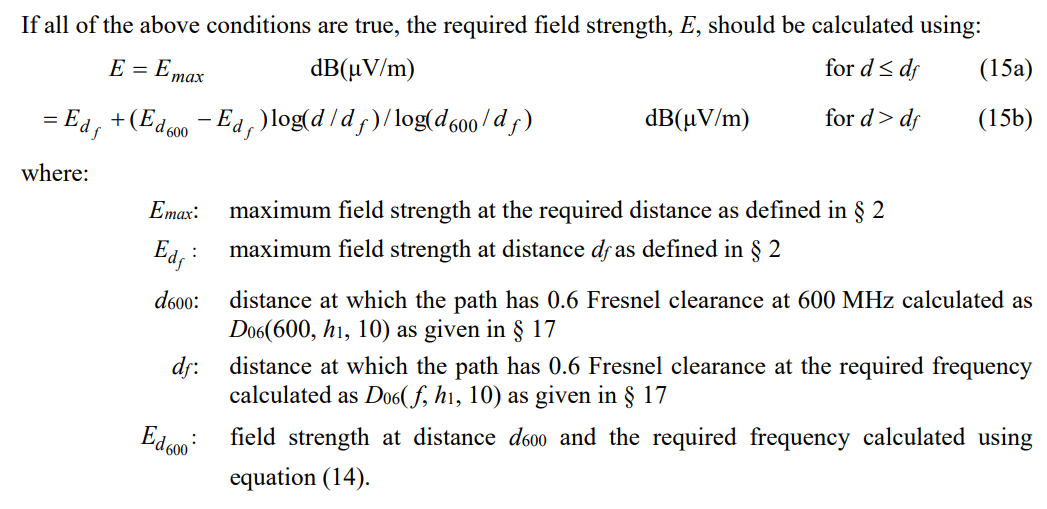

elseif(path >=3 && frequency_mhz< 100 && distancia<D06(600, h1, 10))
    d600 = D06(600, h1, 10);
    df = D06(frequency_mhz,h1,10);
        if(distance <= df)
            E = Step_19a(lower_percentage, 0 , distancia)  
        else
            Edf = Step_19a(lower_percentage, 0 , df);
            Ed600 = calculate_field_strength(d600,lower_height,fsup,path, lower_percentage)
            E = Edf + (Ed600-Edf)*(log10(distancia/df)/log10(d600/df))   
        end
end

## Passo 11. Procedimento para caminho misto

% Note that if different sections of the path exist classified as both cold and warm sea, all sea sections should be classified as warm sea.
if caminho_misto == 1
    if (primeira_parte == segunda_parte)
        primeira_parte = "warm_sea";
        segunda_parte = "warm_sea";

    % If the path contains both warm sea and cold sea portions, the warm sea curves should be used when calculating Esea(d).
    elseif ((primeira_parte == "warm_sea" && segunda_parte == "cold_sea") || (primeira_parte == "cold_sea" && segunda_parte == "warm_sea"))
        h1 = 10 % Usar anexo 5 $3
    end
end

CONTINUAÇÃO NO FINAL -> LINHA: 567 (LEGAL REFERENCIAR AS FUNÇÕES AQUI EM CIMA)

## 5. Correções (Verde)

    Para caminhos terrestres, é importante levar em conta as obstruções no meio do caminhos

    Para comunicação quando há obstrução na linha de visada, devido às alturas das antenas, é necessário realizar a correção do campo devido a isso. O ângulo em questão é o *terrain clearance angle - tca*, este por sua vez representa a inclinação da linha da antena de transmissão que limpa todos os obstáculos até uma deistância de 15 km. 

    Neste caso, o enlace não deve estender mais do que 16 km, além disso, não é necessário elvar em conta a curvatura da terra. O ângulo tca deve estar entre 0,55º e 40º.

    A correção é dada por:


$$Correção = J(v') - J(v)$$
  
$$\textrm{dB}$$


Além do mais,


$$v = 0.036\sqrt{f}$$



$$v' = 0.065\theta_{tca}\sqrt{f}$$


    Podemos observar também o gráfico de correção em função do ângulo em questão:

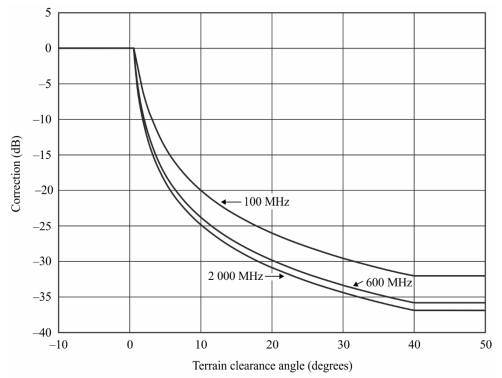


% Step 12: If information on the terrain clearance angle at a receiving/mobile antenna adjacent to land
% is available, correct the field strength for terrain clearance angle at the receiver/mobile using the
% method given in Annex 5, § 11.

if skip_step_12 == 0
    vl = 0.036*sqrt(frequency_mhz);
    v = 0.065*tca_receptor*sqrt(frequency_mhz);
    Correction12 = Jl(vl) -Jl(v);
end

%Deve ser incluido A conta de J e adicioná-lo na correção


Temos também, o espalhamento troposférico, que se refere ao campo disperso na troposfera.

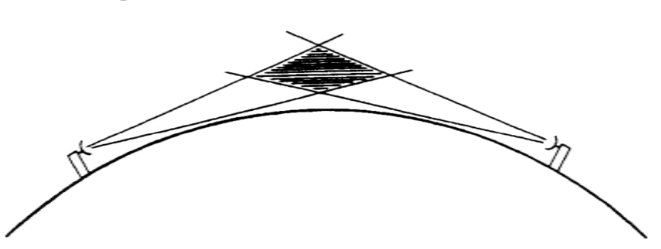

Este espalhamento tem como consequência uma perda que deve ser inserida no cálculo do campo elétrico final.

Tal perda é dada por:


$$E_{ts}=24.4-20log(d)-10\theta_{s}-L_{f}+0.15N_{0}+Gt dB     $$
  
$$(\mu V/m)$$


onde

$d$ = distância em km;

$L_{f}=5log(f)-2.5(log(f)-3.3)^2$ = Perda de frequência dependente 

$N_{0}=325$ = Refratividade superficial mediana;


$$G_{t}=10.1(-log(0.02t))^{0.7}$$
 

$t$ = Porcentagem de tempo requerida.

Para o valor de $\theta_{s}$:


$$\theta_{s}=\frac_{180d}{k\pi a}+\theta_{eff}+\theta$$


onde

$\theta_{eff}$ = Ângulo tca do terminal transmissor;

$\theta$ = Ângulo tca do terminal receptor;

$a$ = Raio da Terra (6 370 km);

$k=\frac{4}{3}$ = Fator de raio da Terra efetivo para condições de refratitividade medianas; 

% Step 13: Calculate the estimated field strength due to tropospheric scattering using the method given
% in Annex 5 § 13, and take the maximum of E and Ets.

if(tca == 1)
    theta_s = (180*distancia)/(pi*(4/3)*6370)+theta_eff+tca_receptor;
else
    theta_s = (180*distancia)/(pi*(4/3)*6370);
end

if(theta_s <= 0)
    E_ts = 24.4-20*log10(distancia)-(5*log10(frequency_mhz)-2.5*(log10(frequency_mhz)-3.3)^2)+0.15*325+10.1*(-log10(0.02))^(0.7)
else
    E_ts = 24.4-20*log10(distancia)-10*theta_s-(5*log10(frequency_mhz)-2.5*(log10(frequency_mhz)-3.3)^2)+0.15*325+10.1*(-log10(0.02))^(0.7)
end

%%%Somar o campo E com Ets


Agora, deverá ser feita uma correção devido à altura da antena receptora considerando as obstruções próximas. Vejamos a seguir um diagrama de procedimento para o cálculo de correção:

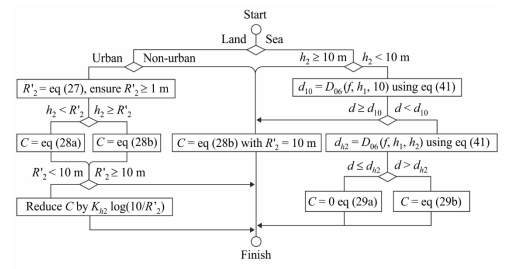

    Como visto acima, é necessário dividir o caso em duas partes diferentes: O caminho por mar ou por terra.

    Isso é importante porque as condições de obstrução são diferentes para cada caso.

    Antes dos cálculos, definimos as seguintes variáveis:


$$v = K_{nu} \sqrt{h_{dif2}\theta_{clut2}}$$



$$h_{dif2}=R'_{2} - h_{2}$$



$$\theta_{clut2}=arctan(\frac{h_{dif2}}{27})$$



$$K_{h2}=3.2+6.2log(f)$$



$$K_{nu}=0.0108\sqrt{f}$$



$$f=\textrm{frequência}\;\left(\textrm{MHz}\right)$$


### 1º Caso (Terra):

    Sendo $R'_{2}$ a altura da obstrução "representativa", que por sua vez é calculada por:


$$R'_{2} = (1000dR_{2}-15h_{1})/(1000d-15)$$
  
$$m$$


    Considerando que não hajam objetos que obstruem a linha divisada, a correção será:

$C = K_{h2}*log(h_2/R'_2)$  $\textrm{dB}$ (REC ITU-R P.1546-6 eq.28b)

    Caso hajam objetos que obstruam a linha de visada, a correção agora deve ser calculada por:

$C = 6.03-J(v)$  $\textrm{dB}$ (REC ITU-R P.1546-6 eq.28a)

    Observe que no diagrama a questão de obstrução é definida pelas relações entre $R'_{2}$ e $h_{2}$.

### 2º Caso (Mar):

    Neste caso, mesmo não havendo obstruções claras como em propagação terrestre, é necessário verificar se há obstrução na primeira zona de Fresnel pela superfície do mar (neste caso, a obstrução é limitada a 60%).

    Para isto, calculamos tal distância necessária:


$$D_{06}=\frac{D_f*D_h}{D_f+D_h}$$
   
$$\textrm{km}$$


    Onde:


$$Df = 0.0000389fh_1h_2$$
  
$$\textrm{km}$$



$$Dh = 4.1(\sqrt{h_1}+\sqrt{h_2})$$
  
$$\textrm{km}$$


    Perceba então que $D_{06}$ é função das alturas das antenas receptora, transmissora e também da frequência ($D_{06}(f,h_1,h_2)$).

    Desta forma, a distância $D_{06}$ será dada considerando a $h_2 = 10$ $m$, ($d_{10}$).

    Caso a distância real do enlace seja menor que necessária para não obstrução, é deve ser utilizada a equação 28b, considerando uma obstrução de $10\;m$. 

    Caso seja menor, é calculada outra distância $D_{06}$ para obstrução de 60% da zona de Fresnel utilizando os dados das alturas reais das antenas. ($d_{h2}$). Se esta distância necessária for maior que a distância do enlace, significa que não há correção a ser feita, entretanto se for maior, é necessário utilizar a seguinte equação:


$$C=C_{10} \;\log \frac{d}{d_{\textrm{h2}} }\;\log \frac{d_{10} }{d_{\textrm{h2}} }$$
   
$$\textrm{dB}$$


    Onde $C_{10}$ é a correção utilizando a equação 28b com $R_2^{\prime } =10\;m$.

%Step 14: Correct the field strength for receiving/mobile antenna height h2 using the method given in
%Annex 5, § 9.

if(primeira_parte == "Cold Sea" || primeira_parte == "Warm Sea")
    if(h2 >= 10)
        Correction14 = (3.2+6.2*log10(frequency_mhz))*log(h2/10);
    else
        d10 = (0.0000389*frequency_mhz*h1*10*4.1*(sqrt(h1)+sqrt(10)))/(0.0000389*frequency_mhz*h1*10+4.1*(sqrt(h1)+sqrt(10)));
        if(distancia >= d10)
            Correction14 = (3.2+6.2*log10(frequency_mhz))*log(h2/10);
        else
            dh2 = (0.0000389*frequency_mhz*h1*h2*4.1*(sqrt(h1)+sqrt(h2)))/(0.0000389*frequency_mhz*h1*h2+4.1*(sqrt(h1)+sqrt(h2)));
            if(d <= dh2)
                Correction14 = 0;
            else
                C10 = (3.2+6.2*log10(frequency_mhz))*log10(h2/R2l);
                Correction14 = C10*log10(distancia/dh2)/log10(d10/dh2);
            end
        end
    end
else
    if(tipo_terreno == "Urban")
        R2l = (1000*distancia*clutter_height_R2-15*h1)/(1000*distancia-15);
        if(R2l < 1)
            R2l = 1;
        end
        if(h2 < R2l)
            Correction14 = 6.03 - Jl(v);
        else
            Correction14 = (3.2+6.2*log10(frequency_mhz))*log10(h2/R2l);
        end
        if(R2l < 10)
            Correction14 = Correction14 - (3.2+6.2*log10(frequency_mhz)*log10(10/R2l));
        end
    elseif tipo_terreno == "Not Urban"
        Correction14 = (3.2+6.2*log10(frequency_mhz))*log(h2/10);
    end
end

    Agora, será feita a correção para obstrução no terminal transmissor. Perceba que, ao contrário do terminal receptor visto antes, se não houver obstrução não é necessário realizar a correção, pois tal correção para esse caso já é feita no receptor.

    Para isto, o cálculo feito é similar ao utilizado no caso anterior, entretanto com as alturas do lado transmissor.


$$C=-J\left(v\right)\;\;\;\textrm{dB}$$


$v=K_{\textrm{nu}} \sqrt{h_{\textrm{dif1}} \theta_{\textrm{clut1}} }$                para         $R_1 \ge h_a$

$v=-K_{\textrm{nu}} \sqrt{h_{\textrm{dif1}} \theta_{\textrm{clut1}} }\;$            para         $R_1 <h_a$


$$h_{\textrm{dif1}} =h_a -R_1$$



$$\theta_{\textrm{clut1}} =\arctan \left(\frac{h_{\textrm{dif1}} }{27}\right)$$



$$K_{\textrm{nu}} =0\ldotp 0108\sqrt{f}$$


%Step 15: If there is clutter around the transmitting/base terminal, even if at a lower height above
%ground than the antenna, correct for its effect using the method given in Annex 5, § 10.

if(skip_step_15 == 0)

    K_nu = 0.0108*sqrt(frequency_mhz);
    h_dif1 = ha - clutter_height_R1;
    theta_clut1 = (180/pi)*(atan(h_dif1/21));
    v = K_nu*sqrt(h_dif1*theta_clut1);

    Correction15 = -Jl(v)

end

    Agora, supondo que o caminho de propagação seja inclinado, a correção se dá por:


$$C=20\log \left(\frac{d}{d_{\textrm{slope}} }\right)\;\;\;\textrm{dB}$$



$$d_{\textrm{slope}} =\sqrt{d^2 +{10}^{-6} {\left\lbrack \left(h_a +h_{\textrm{tter}} \right)-\left(h_2 +h_{\textrm{rter}} \right)\right\rbrack }^2 }$$


%Step 16: Apply the slope-path correction given in Annex 5, § 14.

d_slope = sqrt(distancia^2+(10^-6)*((ha+htter)-(hb+hrter))^2);
Correction16 = 20*log10(d/d_slope);

## 6. Caminhos menores que 1 km (Verde)

%Step 17: Annex 5, § 15, gives the method for paths less than 1 km. As noted immediately before Step
%1 above, it may first be necessary to follow Steps 1 to 16 for d = 1 km.

if(skip_step_16 == 0)
    if(distancia <= 0.04)
        %Menor que 0.04 km
        E = 106.9 - 20*log10(d_slope);
    else
        %Entre 0.04 e 1 km
        d_inf = sqrt(0.04^2+(10^-6)*((ha+htter)-(hb+hrter))^2);
        d_sup = sqrt(1^2+(10^-6)*((ha+htter)-(hb+hrter))^2);
        E_inf = 106.9 - 20*log10(d_slope);

        %OBS: E_sup abaixo é o campo encontrado dos passos 1 ao 16!!
        % E = E_inf + (E_sup - E_inf)*log10(d_slope/d_inf)*log10(d_sup/d_inf);
    end
end

## Passo 20. Perdas básicas

% Step 20: If required, convert field strength to equivalent basic transmission loss for the path using the method given in Annex 5, § 17.

function Lb = perdas_transm(E)
    Lb = 139.3 - E + 20*log10*(frequency_mhz); % E: field strength (dB(V/m)) for 1 kW e.r.p.
end


## X. Funções

### Função do cálculo do campo tabelado

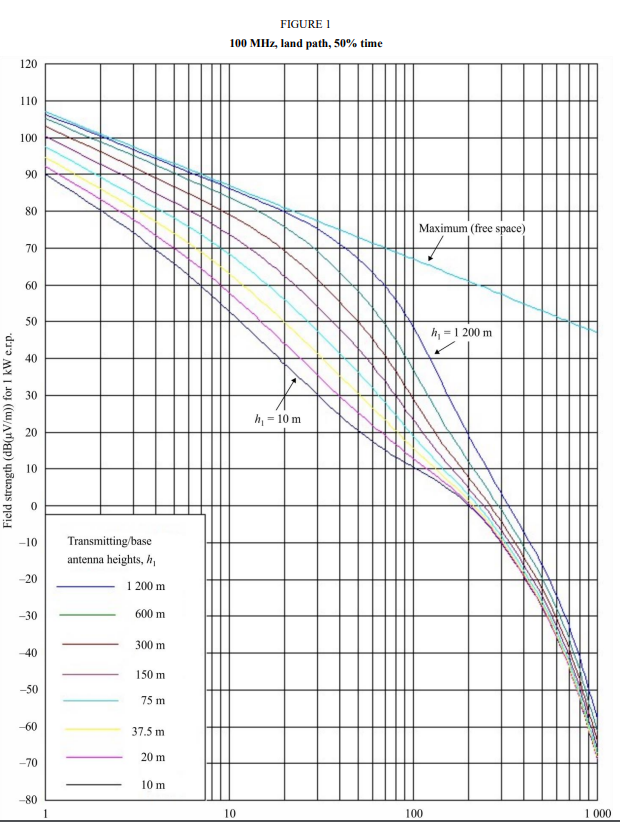

function E = calculate_field_strength(d,h1,f,path, time)

    exceltables = ...
   {[78,10,20,37.5,75,150,300,600,1200,0;1,89.9759,92.1812,94.6355,97.3845,100.3181,103.1205,105.2426,106.3566,106.9;2,80.2751,83.0908,86.0014,89.2076,92.6742,96.1197,98.8577,100.2846,100.8794;3,74.1662,77.5296,80.8234,84.3504,88.1427,91.9686,95.0958,96.7306,97.3576;4,69.5184,73.3548,77.0149,80.8312,84.885,88.9934,92.4125,94.2077,94.8588;5,65.6994,69.9206,73.9248,78.0214,82.3137,86.6601,90.3203,92.2498,92.9206;6,62.4359,66.9578,71.2723,75.6407,80.1635,84.7271,88.6005,90.6489,91.337;7,59.5803,64.3322,68.9161,73.5423,78.2915,83.0633,87.1352,89.294,89.998;8,57.0412,61.9673,66.7783,71.6424,76.6127,81.5891,85.8531,88.1186,88.8382;9,54.756,59.814,64.8127,69.8903,75.0733,80.2524,84.7074,87.0797,87.8152;10,52.6796,57.8377,62.9896,68.2548,73.6382,79.0175,83.6656,86.1477,86.9;11,50.7782,56.0126,61.2886,66.7156,72.2842,77.8593,82.704,85.3015,86.0721;12,49.0255,54.3183,59.6945,65.2592,70.9957,76.7598,81.8047,84.5251,85.3164;13,47.4007,52.7385,58.1954,63.8762,69.7625,75.7062,80.9539,83.8065,84.6211;14,45.8873,51.2596,56.7816,62.5595,68.5777,74.6895,80.141,83.1361,83.9774;15,44.4715,49.8704,55.4448,61.3035,67.4365,73.7034,79.3576,82.5061,83.3782;16,43.1423,48.5613,54.1779,60.1035,66.3356,72.7438,78.5971,81.9102,82.8176;17,41.8902,47.3243,52.9746,58.9555,65.2725,71.8079,77.8546,81.3432,82.291;18,40.7074,46.1523,51.8294,57.8559,64.2452,70.894,77.1264,80.8006,81.7946;19,39.5871,45.0395,50.7377,56.8014,63.2518,70.0011,76.4098,80.2786,81.3249;20,38.5237,43.9806,49.695,55.7889,62.291,69.1285,75.7029,79.7742,80.8794;25,33.9069,39.3532,45.097,51.2676,57.9231,65.0574,72.2902,77.4302,78.9412;30,30.1811,35.5753,41.2901,47.4593,54.1611,61.4361,69.0821,75.247,77.3576;35,27.1022,32.4093,38.0527,44.1712,50.8594,58.1943,66.0991,73.1376,76.0186;40,24.5178,29.7039,35.239,41.2678,47.9017,55.2511,63.3319,71.0823,74.8588;45,22.3242,27.3561,32.7481,38.6526,45.199,52.5325,60.7465,69.0829,73.8358;50,20.4457,25.2917,30.5082,36.2563,42.6853,49.9783,58.3013,67.139,72.9206;55,18.8242,23.456,28.4679,34.0304,40.3142,47.5432,55.9575,65.2431,72.0927;60,17.4138,21.8079,26.5907,31.9423,38.0553,45.1964,53.6839,63.3818,71.337;65,16.1775,20.3164,24.8512,29.9716,35.891,42.9195,51.4583,61.5403,70.6417;70,15.0848,18.9575,23.232,28.1062,33.813,40.7044,49.2674,59.7052,69.998;75,14.1104,17.7128,21.721,26.3401,31.8196,38.5503,47.1059,57.8662,69.3988;80,13.2334,16.5674,20.3094,24.6703,29.9126,36.4612,44.9742,56.017,68.8382;85,12.4361,15.5089,18.9902,23.0948,28.0952,34.4436,42.8775,54.1554,68.3116;90,11.7041,14.5267,17.757,21.612,26.3701,32.5044,40.8233,52.2826,67.8152;95,11.0249,13.6116,16.6037,20.2192,24.7389,30.6498,38.8202,50.4029,67.3455;100,10.3885,12.7552,15.5241,18.9127,23.2014,28.8839,36.8766,48.5226,66.9;110,9.2115,11.1888,13.56,16.5389,20.3971,25.6248,33.1954,44.7914,66.0721;120,8.121,9.775,11.8136,14.4442,17.9235,22.7202,29.8173,41.1534,65.3164;130,7.0818,8.4718,10.2372,12.578,15.733,20.1389,26.7509,37.666,64.6211;140,6.0704,7.2464,8.7898,10.8924,13.7749,17.8372,23.9815,34.3703,63.9774;150,5.0717,6.0747,7.4382,9.3465,12.0024,15.7687,21.4807,31.2885,63.3782;160,4.0764,4.9392,6.157,7.9069,10.3756,13.8901,19.2138,28.4266,62.8176;170,3.0791,3.8278,4.9273,6.5481,8.8623,12.1644,17.1458,25.7785,62.291;180,2.0772,2.7325,3.7355,5.2507,7.4373,10.5609,15.2444,23.3302,61.7946;190,1.0699,1.6483,2.5723,4.0007,6.0818,9.0554,13.4815,21.0635,61.3249;200,0.0578,0.5723,1.4312,2.7879,4.7814,7.629,11.8338,18.9592,60.8794;225,-2.4856,-2.0889,-1.3489,-0.1229,1.7093,4.3216,8.101,14.2872,59.8564;250,-5.0264,-4.7076,-4.0446,-2.9035,-1.1768,1.2793,4.7672,10.2631,58.9412;275,-7.539,-7.2732,-6.6619,-5.5778,-3.922,-1.5725,1.7131,6.7063,58.1133;300,-10.0034,-9.7747,-9.1991,-8.1543,-6.5478,-4.2726,-1.1303,3.4955,57.3576;325,-12.4069,-12.2047,-11.6545,-10.6375,-9.0661,-6.844,-3.8052,0.5494,56.6623;350,-14.7435,-14.5606,-14.0287,-13.0321,-11.4862,-9.303,-6.3403,-2.1885,56.0186;375,-17.0125,-16.844,-16.3258,-15.3442,-13.8173,-11.6631,-8.7573,-4.7594,55.4194;400,-19.2175,-19.0598,-18.5518,-17.5816,-16.0691,-13.9369,-11.0746,-7.1948,54.8588;425,-21.3647,-21.2152,-20.7152,-19.7537,-18.2523,-16.137,-13.3083,-9.5205,54.3322;450,-23.4623,-23.3193,-22.8254,-21.8708,-20.378,-18.276,-15.4736,-11.7583,53.8358;475,-25.5199,-25.3819,-24.8928,-23.9436,-22.4577,-20.3662,-17.5847,-13.9273,53.3661;500,-27.5473,-27.4133,-26.9281,-25.9832,-24.5028,-22.4197,-19.655,-16.0441,52.9206;525,-29.5545,-29.4237,-28.9417,-28.0003,-26.5243,-24.448,-21.6969,-18.1239,52.4968;550,-31.5512,-31.423,-30.9435,-30.005,-28.5327,-26.462,-23.722,-20.1801,52.0927;575,-33.5464,-33.4204,-32.943,-32.0069,-30.5376,-28.4715,-25.7407,-22.2245,51.7066;600,-35.5483,-35.424,-34.9484,-34.0142,-32.5474,-30.4851,-27.762,-24.2673,51.337;625,-37.5636,-37.4409,-36.9667,-36.0342,-34.5695,-32.5104,-29.7938,-26.317,50.9824;650,-39.5981,-39.4765,-39.0036,-38.0725,-36.6095,-34.5532,-31.842,-28.3805,50.6417;675,-41.6555,-41.5349,-41.0631,-40.1331,-38.6717,-36.6177,-33.9111,-30.4626,50.3139;700,-43.738,-43.6183,-43.1474,-42.2184,-40.7582,-38.7062,-36.0036,-32.5662,49.998;725,-45.8459,-45.727,-45.2568,-44.3287,-42.8696,-40.8193,-38.12,-34.6922,49.6932;750,-47.9774,-47.8591,-47.3896,-46.4623,-45.0042,-42.9553,-40.259,-36.8394,49.3988;775,-50.1288,-50.0111,-49.5421,-48.6155,-47.1582,-45.1106,-42.4168,-39.0044,49.114;800,-52.2942,-52.177,-51.7086,-50.7825,-49.3259,-47.2794,-44.5879,-41.1817,48.8382;825,-54.4659,-54.3492,-53.8812,-52.9555,-51.4996,-49.4541,-46.7645,-43.3639,48.5709;850,-56.6344,-56.518,-56.0504,-55.1252,-53.6698,-51.6252,-48.9373,-45.5415,48.3116;875,-58.7885,-58.6724,-58.2052,-57.2804,-55.8255,-53.7816,-51.0952,-47.7037,48.0598;900,-60.916,-60.8002,-60.3332,-59.4088,-57.9543,-55.9111,-53.2261,-49.8383,47.8152;925,-63.0036,-62.888,-62.4213,-61.4972,-60.0431,-58.0005,-55.3167,-51.9323,47.5772;950,-65.0378,-64.9225,-64.456,-63.5322,-62.0784,-60.0363,-57.3536,-53.9722,47.3455;975,-67.0053,-66.8902,-66.4239,-65.5003,-64.0469,-62.0052,-59.3234,-55.9447,47.1199;1000,-68.8933,-68.7783,-68.3123,-67.3889,-65.9357,-63.8945,-61.2136,-57.8373,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,89.9759,92.1812,94.6355,97.3845,100.3181,103.1205,105.2426,106.3566,106.9;2,80.2751,83.0908,86.0014,89.2076,92.6742,96.1197,98.8577,100.2846,100.8794;3,74.1662,77.5296,80.8234,84.3504,88.1427,91.9686,95.0958,96.7306,97.3576;4,69.5184,73.3548,77.0149,80.8312,84.885,88.9934,92.4125,94.2077,94.8588;5,65.6994,69.9206,73.9248,78.0214,82.3137,86.6601,90.3203,92.2498,92.9206;6,62.4359,66.9578,71.2723,75.6407,80.1635,84.7271,88.6005,90.6489,91.337;7,59.5803,64.3322,68.9161,73.5423,78.2915,83.0633,87.1352,89.294,89.998;8,57.0412,61.9673,66.7783,71.6424,76.6127,81.5891,85.8531,88.1186,88.8382;9,54.756,59.814,64.8127,69.8903,75.0733,80.2524,84.7074,87.0797,87.8152;10,52.6796,57.8377,62.9896,68.2548,73.6382,79.0175,83.6656,86.1477,86.9;11,50.7782,56.0126,61.2886,66.7156,72.2842,77.8593,82.704,85.3015,86.0721;12,49.1805,54.3636,59.7455,65.2859,70.9957,76.7598,81.8047,84.5251,85.3164;13,47.7587,52.9466,58.3666,63.9883,69.7889,75.7062,80.9539,83.8065,84.6211;14,46.4469,51.6299,57.0738,62.7592,68.6638,74.6895,80.141,83.1361,83.9774;15,45.231,50.4013,55.8571,61.5908,67.5841,73.7268,79.3576,82.5061,83.3782;16,44.0999,49.2508,54.7085,60.4768,66.5444,72.8073,78.5971,81.9102,82.8176;17,43.0444,48.1701,53.6211,59.4123,65.5405,71.9123,77.8613,81.3432,82.291;18,42.0566,47.1523,52.5893,58.3928,64.5693,71.0385,77.1586,80.801,81.7946;19,41.1301,46.1915,51.6082,57.4149,63.6282,70.1832,76.4694,80.2888,81.3249;20,40.2594,45.2826,50.6735,56.4754,62.7151,69.3449,75.7909,79.7964,80.8794;25,36.5944,41.383,46.5836,52.2717,58.5199,65.3728,72.4961,77.5464,78.9412;30,33.8032,38.3097,43.255,48.7333,54.8516,61.7351,69.3036,75.4938,77.3576;35,31.6347,35.8355,40.4928,45.712,51.6242,58.4176,66.224,73.5021,76.0186;40,29.923,33.8117,38.1691,43.107,48.7736,55.4053,63.3319,71.5012,74.8588;45,28.5508,32.133,36.1925,40.8439,46.2477,52.6764,60.7465,69.469,73.8358;50,27.4316,30.7209,34.4937,38.8646,44.0024,50.2056,58.3013,67.4142,72.9206;55,26.5003,29.5155,33.0182,37.1215,41.9989,47.9667,55.9575,65.3596,72.0927;60,25.7074,28.4699,31.7224,35.5748,40.2029,45.9341,53.6839,63.3818,71.337;65,25.015,27.5472,30.5704,34.1908,38.5841,44.0829,51.4583,61.5403,70.6417;70,24.3943,26.7182,29.533,32.9406,37.1153,42.3901,49.4406,59.7052,69.998;75,23.8233,25.96,28.5866,31.8003,35.773,40.8347,47.67,57.8662,69.3988;80,23.2855,25.2546,27.7115,30.7494,34.5367,39.3975,46.0173,56.017,68.8382;85,22.7684,24.5877,26.8922,29.7709,33.3886,38.0617,44.4695,54.1554,68.3116;90,22.2629,23.9485,26.116,28.8509,32.314,36.8124,43.0143,52.3908,67.8152;95,21.7622,23.3286,25.3728,27.9778,31.3001,35.6368,41.641,50.8049,67.3455;100,21.2618,22.7213,24.6547,27.1424,30.3366,34.524,40.3396,49.2819,66.9;110,20.2494,21.5271,23.27,25.5555,28.5273,32.4504,37.9192,46.41,66.0721;120,19.2111,20.3404,21.927,24.0462,26.8338,30.5335,35.6958,43.7453,65.3164;130,18.1422,19.1487,20.6055,22.5872,25.2216,28.7323,33.6267,41.2598,64.6211;140,17.0436,17.9469,19.2949,21.1621,23.6684,27.0192,31.6803,38.929,63.9774;150,15.9189,16.7343,17.9905,19.7616,22.1604,25.3752,29.8338,36.7323,63.3782;160,14.7727,15.513,16.6911,18.3811,20.6889,23.7879,28.0705,34.6528,62.8176;170,13.6105,14.2861,15.3976,17.0187,19.2491,22.2488,26.3783,32.6766,62.291;180,12.4375,13.0574,14.1116,15.674,17.8383,20.7525,24.7484,30.7923,61.7946;190,11.2587,11.8305,12.8355,14.3474,16.4548,19.2951,23.1743,28.9906,61.3249;200,10.0789,10.6091,11.5716,13.04,15.0982,17.8742,21.651,27.2636,60.8794;225,7.1497,7.5987,8.4779,9.8608,11.822,14.4704,18.0408,23.2324,59.8564;250,4.2851,4.6765,5.496,6.8173,8.7083,11.2632,14.6804,19.5497,58.9412;275,1.5113,1.8606,2.6365,3.9122,5.7508,8.2357,11.5367,16.1562,58.1133;300,-1.1618,-0.844,-0.101,1.1401,2.9388,5.37,8.5812,13.0044,57.3576;325,-3.7357,-3.4421,-2.7244,-1.51,0.2576,2.6468,5.7875,10.0543,56.6623;350,-6.2185,-5.9439,-5.246,-4.0528,-2.3099,0.0461,3.1303,7.2711,56.0186;375,-8.6223,-8.3628,-7.6809,-6.5046,-4.7815,-2.4525,0.5862,4.6241,55.4194;400,-10.9609,-10.7138,-10.0448,-8.8823,-7.1754,-4.8683,-1.8671,2.086,54.8588;425,-13.2487,-13.0119,-12.3534,-11.2023,-9.5087,-7.2198,-4.2496,-0.3672,54.3322;450,-15.4996,-15.2712,-14.6216,-13.48,-11.7975,-9.5238,-6.5795,-2.7566,53.8358;475,-17.7264,-17.5053,-16.8631,-15.7295,-14.0563,-11.7954,-8.8731,-5.1005,53.3661;500,-19.9407,-19.7256,-19.0897,-17.9629,-16.2977,-14.0477,-11.1441,-7.4146,52.9206;525,-22.1523,-21.9424,-21.3119,-20.1909,-18.5325,-16.2918,-13.4042,-9.7118,52.4968;550,-24.3691,-24.1636,-23.5378,-22.4218,-20.7693,-18.5366,-15.6629,-12.0027,52.0927;575,-26.597,-26.3955,-25.7737,-24.662,-23.0147,-20.789,-17.9273,-14.2951,51.7066;600,-28.8402,-28.642,-28.0237,-26.9159,-25.273,-23.0534,-20.2023,-16.5946,51.337;625,-31.1003,-30.9052,-30.29,-29.1855,-27.5465,-25.3323,-22.4905,-18.9043,50.9824;650,-33.3772,-33.1848,-32.5723,-31.4707,-29.8352,-27.6258,-24.7921,-21.2251,50.6417;675,-35.6687,-35.4786,-34.8685,-33.7696,-32.1371,-29.9319,-27.1056,-23.5555,50.3139;700,-37.9706,-37.7825,-37.1746,-36.078,-34.4483,-32.2468,-29.4269,-25.892,49.998;725,-40.2767,-40.0905,-39.4846,-38.39,-36.7627,-34.5646,-31.7506,-28.2293,49.6932;750,-42.5795,-42.395,-41.7907,-40.6981,-39.073,-36.8779,-34.0691,-30.56,49.3988;775,-44.8698,-44.6868,-44.0841,-42.9931,-41.37,-39.1777,-36.3736,-32.8755,49.114;800,-47.1374,-46.9558,-46.3545,-45.265,-43.6437,-41.4539,-38.654,-35.1659,48.8382;825,-49.3712,-49.1908,-48.5908,-47.5027,-45.8831,-43.6954,-40.8994,-37.4204,48.5709;850,-51.5597,-51.3804,-50.7816,-49.6947,-48.0765,-45.8909,-43.0984,-39.6276,48.3116;875,-53.6911,-53.5128,-52.915,-51.8293,-50.2125,-48.0287,-45.2394,-41.7762,48.0598;900,-55.754,-55.5766,-54.9798,-53.8952,-52.2796,-50.0975,-47.3111,-43.8548,47.8152;925,-57.7376,-57.5611,-56.9652,-55.8815,-54.2671,-52.0865,-49.3029,-45.8528,47.5772;950,-59.6323,-59.4566,-58.8615,-57.7787,-56.1653,-53.9862,-51.205,-47.7607,47.3455;975,-61.4296,-61.2546,-60.6603,-59.5783,-57.9658,-55.788,-53.0091,-49.5702,47.1199;1000,-63.1227,-62.9485,-62.3548,-61.2736,-59.662,-57.4854,-54.7086,-51.2747,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,89.9759,92.1812,94.6355,97.3845,100.3181,103.1205,105.2426,106.3566,106.9;2,80.2751,83.0908,86.0804,89.4069,92.913,96.3309,98.9814,100.3265,100.8794;3,74.1662,77.5296,80.8983,84.623,88.4947,92.2978,95.2961,96.7966,97.3576;4,69.5184,73.3548,77.0492,81.1099,85.2792,89.3842,92.6604,94.2887,94.8588;5,65.6994,69.9206,73.9419,78.2871,82.714,87.0769,90.5957,92.3397,92.9206;6,62.4359,66.9578,71.3181,75.9006,80.5545,85.1471,88.8884,90.7434,91.337;7,59.6477,64.3322,69.04,73.8179,78.6719,83.4731,87.4242,89.3896,89.998;8,57.4622,62.1663,67.0245,71.961,76.9905,81.9827,86.135,88.2125,88.8382;9,55.541,60.276,65.2164,70.2803,75.4623,80.6296,84.9768,87.1698,87.8152;10,53.8305,58.5796,63.5772,68.7419,74.0555,79.3829,83.9196,86.2324,86.9;11,52.2925,57.0431,62.0785,67.3218,72.7475,78.221,82.9421,85.3798,86.0721;12,50.8985,55.6409,60.6986,66.0017,71.522,77.1281,82.0287,84.5966,85.3164;13,49.6271,54.3533,59.4208,64.7677,70.3668,76.0927,81.1676,83.8713,84.6211;14,48.4613,53.1646,58.2316,63.6088,69.2725,75.1058,80.3499,83.1949,83.9774;15,47.3878,52.0625,57.1201,62.5159,68.2315,74.1608,79.5684,82.5602,83.3782;16,46.3956,51.0366,56.0774,61.4817,67.2378,73.2523,78.8175,81.9616,82.8176;17,45.4757,50.0784,55.0959,60.4999,66.2863,72.3758,78.0928,81.3943,82.291;18,44.6205,49.181,54.1694,59.5653,65.3728,71.528,77.3905,80.8544,81.7946;19,43.8236,48.3381,53.2925,58.6736,64.4938,70.7059,76.7078,80.3386,81.3249;20,43.0795,47.5448,52.4605,57.8207,63.6463,69.9071,76.0421,79.8443,80.8794;25,40.004,44.1826,48.8533,54.0388,59.8016,66.2012,72.907,77.6202,78.9412;30,37.7291,41.5769,45.9457,50.8779,56.4721,62.8741,69.9951,75.6752,77.3576;35,36.0039,39.5036,43.5451,48.1831,53.5444,59.8502,67.2389,73.887,76.0186;40,34.6672,37.8222,41.5341,45.8633,50.9567,57.0964,64.6186,72.1757,74.8588;45,33.6089,36.4369,39.8327,43.8571,48.6692,54.5959,62.1363,70.4886,73.8358;50,32.751,35.2784,38.3815,42.1169,46.6493,52.3351,59.8006,68.7959,72.9206;55,32.0373,34.2942,37.1326,40.6017,44.8663,50.2988,57.6184,67.0869,72.0927;60,31.4265,33.4436,36.047,39.2754,43.2902,48.4685,55.592,65.3661,71.337;65,30.8881,32.6948,35.0918,38.1058,41.8917,46.8231,53.7182,63.6471,70.6417;70,30.3994,32.0229,34.24,37.0646,40.6435,45.3407,51.9897,61.9468,69.998;75,29.9437,31.4084,33.4695,36.1276,39.521,43.9998,50.3962,60.2808,69.3988;80,29.5085,30.8359,32.7621,35.2744,38.5026,42.7801,48.9254,58.6618,68.8382;85,29.0848,30.2938,32.1034,34.4881,37.5695,41.6633,47.5649,57.0983,68.3116;90,28.6659,29.773,31.4816,33.7548,36.7061,40.633,46.3021,55.5954,67.8152;95,28.2473,29.2668,30.8878,33.0631,35.8992,39.6753,45.1251,54.1551,67.3455;100,27.8259,28.7699,30.3146,32.4041,35.138,38.7781,44.023,52.7772,66.9;110,26.9674,27.7901,29.2093,31.1563,33.719,37.1263,42.0052,50.2009,66.0721;120,26.0832,26.8139,28.1347,29.9696,32.3964,35.6152,40.1836,47.843,65.3164;130,25.1727,25.8315,27.0731,28.8184,31.1365,34.2019,38.509,45.6743,64.6211;140,24.2379,24.8384,26.0148,27.6876,29.9178,32.8577,36.9455,43.6664,63.9774;150,23.2816,23.8337,24.9553,26.5686,28.7269,31.5637,35.4671,41.794,63.3782;160,22.3066,22.818,23.893,25.457,27.5561,30.3073,34.0553,40.0356,62.8176;170,21.3159,21.7929,22.828,24.3507,26.4006,29.0805,32.697,38.3736,62.291;180,20.3124,20.7607,21.7615,23.2493,25.258,27.8779,31.3828,36.7938,61.7946;190,19.2991,19.7237,20.6949,22.1533,24.1272,26.6964,30.1059,35.2845,61.3249;200,18.2792,18.6842,19.6301,21.0634,23.0078,25.5338,28.8614,33.8366,60.8794;225,15.719,16.0893,16.9866,18.3719,20.2597,22.7025,25.8708,30.439,59.8564;250,13.1734,13.5217,14.386,15.738,17.5864,19.9709,23.0258,27.2958,58.9412;275,10.6669,10.9999,11.8414,13.1699,14.99,17.3322,20.3044,24.3519,58.1133;300,8.2112,8.5328,9.3581,10.6694,12.4686,14.7795,17.6898,21.5682,57.3576;325,5.809,6.1216,6.9351,8.2336,10.017,12.3041,15.1671,18.9148,56.6623;350,3.4573,3.7627,4.5674,5.856,7.6273,9.8959,12.7221,16.3671,56.0186;375,1.1498,1.4493,2.2471,3.5281,5.2899,7.5439,10.3409,13.9041,55.4194;400,-1.1217,-0.8271,-0.0347,1.2403,2.9944,5.2368,8.0104,11.5076,54.8588;425,-3.3663,-3.0757,-2.2876,-1.0176,0.7304,2.9634,5.718,9.1612,54.3322;450,-5.593,-5.3056,-4.5211,-3.2551,-1.5122,0.713,3.4519,6.8506,53.8358;475,-7.8104,-7.5258,-6.7443,-5.4815,-3.7428,-1.5241,1.2019,4.5634,53.3661;500,-10.0263,-9.7441,-8.965,-7.7051,-5.9699,-3.7565,-1.0415,2.2888,52.9206;525,-12.2477,-11.9675,-11.1905,-9.9329,-8.2006,-5.9918,-3.286,0.0178,52.4968;550,-14.4801,-14.2015,-13.4263,-12.1707,-10.441,-8.2361,-5.5381,-2.257,52.0927;575,-16.7277,-16.4506,-15.6769,-14.423,-12.6954,-10.4939,-7.8027,-4.541,51.7066;600,-18.9934,-18.7175,-17.9451,-16.6927,-14.967,-12.7683,-10.083,-6.8381,51.337;625,-21.2784,-21.0036,-20.2323,-18.9812,-17.2571,-15.061,-12.3807,-9.1505,50.9824;650,-23.5825,-23.3086,-22.5384,-21.2883,-19.5657,-17.3717,-14.6959,-11.4785,50.6417;675,-25.9039,-25.6309,-24.8615,-23.6124,-21.891,-19.699,-17.0271,-13.821,50.3139;700,-28.2394,-27.9671,-27.1985,-25.9503,-24.23,-22.0397,-19.3712,-16.1751,49.998;725,-30.5843,-30.3127,-29.5447,-28.2973,-26.578,-24.3892,-21.7238,-18.5365,49.6932;750,-32.9326,-32.6616,-31.8943,-30.6475,-28.9291,-26.7416,-24.0789,-20.8995,49.3988;775,-35.2772,-35.0067,-34.2399,-32.9938,-31.2761,-29.0898,-26.4296,-23.2572,49.114;800,-37.6099,-37.3398,-36.5735,-35.3279,-33.6109,-31.4257,-28.7676,-25.6016,48.8382;825,-39.9215,-39.6519,-38.886,-37.641,-35.9246,-33.7403,-31.0842,-27.9238,48.5709;850,-42.2027,-41.9334,-41.1679,-39.9233,-38.2075,-36.0241,-33.3698,-30.2145,48.3116;875,-44.4432,-44.1743,-43.4092,-42.165,-40.4497,-38.2671,-35.6143,-32.4638,48.0598;900,-46.6332,-46.3646,-45.5998,-44.356,-42.6411,-40.4592,-37.808,-34.6616,47.8152;925,-48.7627,-48.4944,-47.7299,-46.4864,-44.772,-42.5907,-39.9408,-36.7983,47.5772;950,-50.8223,-50.5542,-49.79,-48.5468,-46.8328,-44.6521,-42.0034,-38.8644,47.3455;975,-52.8032,-52.5353,-51.7714,-50.5285,-48.8148,-46.6347,-43.9871,-40.8513,47.1199;1000,-54.6976,-54.43,-53.6663,-52.4236,-50.7102,-48.5307,-45.884,-42.7512,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,97.9306,102.2627,105.6108,106.7395,106.889,106.8996,106.9,106.9,106.9;2,88.3787,92.5718,96.9796,99.9909,100.7902,100.8745,100.8792,100.8794,100.8794;3,82.6476,86.6248,91.1362,95.2488,97.0622,97.3375,97.3568,97.3576,97.3576;4,78.4824,82.2984,86.7461,91.3484,94.1925,94.8049,94.8564,94.8587,94.8588;5,75.1674,78.8694,83.2339,88.032,91.7194,92.8052,92.9149,92.9204,92.9206;6,72.3836,76.0071,80.3,85.1676,89.4705,91.1242,91.3254,91.3366,91.337;7,69.9618,73.5338,77.7725,82.658,87.3835,89.6447,89.9769,89.9974,89.998;8,67.8014,71.3434,75.5448,80.429,85.4365,88.2963,88.8027,88.8369,88.8382;9,65.8384,69.3675,73.5467,78.4249,83.6191,87.035,87.7592,87.813,87.8152;10,64.0296,67.5598,71.7299,76.6036,81.9225,85.8333,86.8161,86.8966,86.9;11,62.3445,65.8876,70.0597,74.9332,80.3372,84.6749,85.9514,86.0669,86.0721;12,60.7612,64.3269,68.5106,73.389,78.8532,83.5509,85.1486,85.3085,85.3164;13,59.2632,62.8599,67.0632,71.9516,77.4605,82.4569,84.3945,84.6099,84.6211;14,57.8383,61.4727,65.7024,70.6058,76.1496,81.3915,83.679,83.9617,83.9774;15,56.4767,60.1547,64.4164,69.3392,74.9122,80.3542,82.9939,83.3566,83.3782;16,55.1712,58.8974,63.1958,68.1418,73.7404,79.3453,82.3324,82.7888,82.8176;17,53.9158,57.6941,62.0329,67.0053,72.6275,78.3649,81.689,82.2531,82.291;18,52.7058,56.5391,60.9214,65.9228,71.5675,77.413,81.0595,81.7455,81.7946;19,51.5374,55.428,59.8559,64.8884,70.555,76.4891,80.4404,81.2624,81.3249;20,50.4077,54.357,58.8321,63.8972,69.5854,75.5925,79.829,80.8006,80.8794;25,45.2875,49.5269,54.2382,59.4711,65.2627,71.4917,76.8414,78.7303,78.9412;30,40.8768,45.3652,50.2812,55.6642,61.548,67.8872,73.9176,76.8957,77.3576;35,37.1078,41.7585,46.8096,52.2946,58.2455,64.6526,71.086,75.1515,76.0186;40,33.912,38.619,43.7193,49.2453,55.2295,61.6829,68.371,73.4151,74.8588;45,31.1999,35.8627,40.9297,46.4358,52.4173,58.9001,65.7671,71.6434,73.8358;50,28.941,33.4601,38.41,43.8318,49.7696,56.2637,63.2721,69.8376,72.9206;55,27.0419,31.3434,36.1111,41.3954,47.2519,53.7374,60.8636,67.9995,72.0927;60,25.4331,29.4654,34.0016,39.1049,44.8456,51.3007,58.5257,66.1388,71.337;65,24.0517,27.784,32.0556,36.9444,42.5395,48.9414,56.2464,64.2638,70.6417;70,22.8443,26.2633,30.2511,34.9021,40.3267,46.6525,54.0174,62.3812,69.998;75,21.7665,24.8731,28.5697,32.9685,38.2028,44.4308,51.8342,60.4964,69.3988;80,20.7837,23.5882,26.9955,31.1353,36.1649,42.2754,49.6949,58.614,68.8382;85,19.8692,22.3886,25.5151,29.3953,34.2106,40.1864,47.5997,56.7386,68.3116;90,19.0033,21.2582,24.1171,27.7419,32.3375,38.1641,45.5498,54.8748,67.8152;95,18.1718,20.1846,22.7918,26.1689,30.5432,36.2092,43.5472,53.0271,67.3455;100,17.3649,19.1583,21.5312,24.6709,28.8251,34.3217,41.5938,51.1999,66.9;110,15.8004,17.2196,19.1777,21.8791,25.6062,30.7483,37.8425,47.6238,66.0721;120,14.2796,15.4017,17.0139,19.3301,22.658,27.4392,34.3085,44.1751,65.3164;130,12.791,13.6806,15.0093,16.9939,19.9582,24.3857,30.9987,40.8749,64.6211;140,11.3318,12.0417,13.1416,14.8457,17.4861,21.5771,27.9155,37.7356,63.9774;150,9.9033,10.476,11.3938,12.8648,15.2224,19.001,25.057,34.7629,63.3782;160,8.5084,8.9775,9.7526,11.0331,13.1486,16.6437,22.4179,31.9574,62.8176;170,7.1502,7.5423,8.2071,9.3347,11.2469,14.4898,19.9894,29.3161,62.291;180,5.8312,6.1667,6.7479,7.7549,9.4996,12.5225,17.7597,26.8334,61.7946;190,4.5527,4.8474,5.3664,6.2803,7.8897,10.7237,15.7143,24.5024,61.3249;200,3.3147,3.5809,4.0547,4.8983,6.4004,9.0749,13.8366,22.3149,60.8794;225,0.3873,0.6184,1.0326,1.7748,3.1049,5.4885,9.76,17.4148,59.8564;250,-2.3346,-2.1064,-1.7041,-0.9947,0.2563,2.462,6.3514,13.2094,58.9412;275,-4.8982,-4.6558,-4.2402,-3.5274,-2.3048,-0.2082,3.3876,9.5546,58.1133;300,-7.3438,-7.0791,-6.6388,-5.9063,-4.6878,-2.6608,0.7112,6.3206,57.3576;325,-9.7008,-9.4113,-8.9431,-8.1859,-6.9615,-4.9812,-1.7788,3.4004,56.6623;350,-11.9885,-11.6752,-11.1804,-10.3992,-9.1658,-7.2183,-4.1434,0.7117,56.0186;375,-14.2197,-13.8851,-13.367,-12.5646,-11.3222,-9.3982,-6.419,-1.8055,55.4194;400,-16.4028,-16.0501,-15.5123,-14.6923,-13.4419,-11.5351,-8.6276,-4.194,54.8588;425,-18.544,-18.1764,-17.6225,-16.7881,-15.5309,-13.6369,-10.7832,-6.484,54.3322;450,-20.6491,-20.2693,-19.7025,-18.8564,-17.5937,-15.7091,-12.8962,-8.698,53.8358;475,-22.7239,-22.3343,-21.7569,-20.9016,-19.6343,-17.7567,-14.9749,-10.8533,53.3661;500,-24.7745,-24.3769,-23.7911,-22.9283,-21.6573,-19.785,-17.0269,-12.964,52.9206;525,-26.8071,-26.4031,-25.8106,-24.9417,-23.6676,-21.7993,-19.0596,-15.0421,52.4968;550,-28.8281,-28.4189,-27.8209,-26.9472,-25.6705,-23.8052,-21.0798,-17.0976,52.0927;575,-30.8436,-30.4301,-29.8276,-28.9499,-27.6712,-25.8082,-23.094,-19.1396,51.7066;600,-32.8589,-32.4419,-31.8358,-30.9549,-29.6744,-27.8131,-25.1078,-21.1755,51.337;625,-34.8788,-34.459,-33.8499,-32.9663,-31.6843,-29.8244,-27.1261,-23.2115,50.9824;650,-36.9072,-36.485,-35.8735,-34.9876,-33.7044,-31.8456,-29.153,-25.2525,50.6417;675,-38.9468,-38.5227,-37.9091,-37.0214,-35.7371,-33.8791,-31.191,-27.3022,50.3139;700,-40.9992,-40.5735,-39.9582,-39.0689,-37.7838,-35.9264,-33.2421,-29.3626,49.998;725,-43.065,-42.6379,-42.0212,-41.1306,-39.8447,-37.9879,-35.3066,-31.4349,49.6932;750,-45.1435,-44.7152,-44.0973,-43.2057,-41.9191,-40.0627,-37.384,-33.5187,49.3988;775,-47.2329,-46.8037,-46.1848,-45.2922,-44.0051,-42.149,-39.4724,-35.6125,49.114;800,-49.3305,-48.9005,-48.2807,-47.3874,-46.0998,-44.244,-41.5691,-37.7138,48.8382;825,-51.4324,-51.0017,-50.3812,-49.4873,-48.1993,-46.3437,-43.6703,-39.8188,48.5709;850,-53.5341,-53.1028,-52.4817,-51.5871,-50.2988,-48.4435,-45.7713,-41.923,48.3116;875,-55.6299,-55.1982,-54.5765,-53.6815,-52.3929,-50.5377,-47.8666,-44.021,48.0598;900,-57.7139,-57.2817,-56.6596,-55.7642,-54.4753,-52.6203,-49.9501,-46.1069,47.8152;925,-59.7794,-59.3468,-58.7243,-57.8285,-56.5395,-54.6845,-52.0152,-48.1739,47.5772;950,-61.8193,-61.3864,-60.7636,-59.8675,-58.5783,-56.7234,-54.0548,-50.2153,47.3455;975,-63.8266,-63.3934,-62.7703,-61.8739,-60.5846,-58.7298,-56.0617,-52.2238,47.1199;1000,-65.7939,-65.3605,-64.7371,-63.8406,-62.5511,-60.6964,-58.0288,-54.1922,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,97.9346,102.2995,105.7249,106.9047,107.0624,107.0735,107.074,107.074,107.076;2,88.3787,92.5824,97.0592,100.2034,101.0645,101.156,101.1612,101.1614,101.2129;3,82.6476,86.6248,91.1954,95.4771,97.4677,97.7799,97.8019,97.8027,97.8318;4,78.4824,82.2984,86.7887,91.5488,94.6704,95.3843,95.4453,95.4481,95.4589;5,75.1674,78.8694,83.2648,88.2018,92.2107,93.4915,93.6249,93.6317,93.6332;6,72.3836,76.0071,80.3228,85.3166,89.9388,91.8874,92.1369,92.1502,92.1502;7,69.9618,73.5338,77.7894,82.7959,87.816,90.4568,90.8735,90.8995,90.9013;8,67.8014,71.3434,75.5574,80.5631,85.8356,89.1327,89.7706,89.8146,89.8219;9,65.8384,69.3675,73.5563,78.5604,83.9936,87.8758,88.7864,88.856,88.8708;10,64.0296,67.5598,71.7376,76.7443,82.2825,86.6643,87.8922,87.9965,88.02;11,62.3445,65.8876,70.0666,75.0817,80.6917,85.4879,87.067,87.2166,87.2497;12,60.7612,64.3269,68.5179,73.5474,79.2096,84.343,86.2953,86.502,86.5453;13,59.2632,62.8599,67.072,72.1216,77.8246,83.2293,85.5651,85.8419,85.8961;14,57.8383,61.4727,65.7141,70.7888,76.5259,82.1479,84.8671,85.2276,85.2935;15,56.4767,60.1547,64.4325,69.5364,75.3041,81.0999,84.1941,84.6526,84.731;16,55.1712,58.8974,63.2177,68.3543,74.1506,80.0861,83.5404,84.1111,84.2033;17,53.9158,57.6941,62.0624,67.2342,73.058,79.1064,82.9017,83.5988,83.7061;18,52.7058,56.5391,60.9603,66.1692,72.0199,78.1605,82.2747,83.1118,83.236;19,51.5374,55.428,59.9062,65.1535,71.0307,77.2473,81.6569,82.6469,82.7898;20,50.4077,54.357,58.896,64.1822,70.0856,76.3655,81.0467,82.2014,82.3653;25,45.2875,49.5269,54.4068,59.8756,65.8984,72.3788,78.0866,80.1916,80.5032;30,40.8768,45.505,50.6347,56.237,62.347,68.9295,75.2518,78.4086,78.9631;35,37.4471,42.2332,47.437,53.0943,59.2401,65.8707,72.5569,76.7339,77.649;40,34.8466,39.5793,44.7355,50.3528,56.4698,63.104,70.0112,75.1032,76.5034;45,32.8843,37.442,42.445,47.9364,53.9624,60.5589,67.6002,73.4778,75.4885;50,31.4279,35.7233,40.4936,45.7911,51.6731,58.194,65.3099,71.8391,74.578;55,30.3404,34.3246,38.8138,43.8716,49.5697,55.9828,63.1282,70.1807,73.7528;60,29.5019,33.1586,37.3455,42.1394,47.6277,53.9073,61.0453,68.5042,72.9985;65,28.9219,32.2313,36.0919,40.5955,45.8488,51.974,59.0851,66.8665,72.3041;70,28.2261,31.2626,34.8574,39.113,44.1507,50.1125,57.1481,65.1244,71.6609;75,27.6781,30.4429,33.7691,37.7705,42.5841,48.3736,55.3235,63.4392,71.0619;80,27.1468,29.6703,32.7525,36.5169,41.1145,46.7289,53.576,61.7691,70.5015;85,26.6153,28.9272,31.7908,35.3375,39.7304,45.1706,51.9019,60.1217,69.975;90,26.0739,28.2019,30.8714,34.2202,38.4213,43.6911,50.2972,58.5031,69.4786;95,25.5183,27.4869,29.985,33.1552,37.1781,42.283,48.7578,56.9178,69.009;100,24.947,26.7776,29.1247,32.1341,35.9925,40.9393,47.2794,55.3688,68.5635;110,23.7601,25.367,27.4633,30.1978,33.7651,38.4186,44.488,52.3859,67.7357;120,22.5247,23.9606,25.8595,28.3706,31.6912,36.0825,41.8888,49.557,66.9799;130,21.2538,22.5564,24.2975,26.6248,29.7356,33.8937,39.4513,46.8747,66.2847;140,19.9588,21.1553,22.7682,24.9425,27.8735,31.8245,37.1503,44.3268,65.641;150,18.6486,19.7592,21.2664,23.3118,26.0874,29.8541,34.9657,41.9008,65.0417;160,17.3184,18.3624,19.7849,21.7231,24.3639,27.9621,32.8647,39.5438,64.4811;170,15.9449,16.9484,18.3134,20.1701,22.6957,26.131,30.8039,37.1596,63.9546;180,14.6022,15.5657,16.8762,18.6589,21.084,24.3829,28.8703,34.9742,63.4581;190,13.2816,14.2075,15.4681,17.1841,19.5201,22.7002,27.0293,32.9225,62.9885;200,11.9743,12.8811,14.1133,15.7876,18.0628,21.1545,25.3558,31.0646,62.5429;225,8.8069,9.632,10.7572,12.2918,14.3847,17.2391,21.1319,26.4409,61.5199;250,5.7675,6.5457,7.6058,9.0501,11.0177,13.6981,17.3497,22.3242,60.6047;275,2.8763,3.622,4.6352,6.0116,7.8817,10.4223,13.8741,18.5636,59.7769;300,0.1358,0.8588,1.8375,3.1622,4.9551,7.382,10.6669,15.1131,59.0211;325,-2.4627,-1.7557,-0.8027,0.4817,2.2128,4.5459,7.6904,11.9286,58.3259;350,-4.9352,-4.2394,-3.3059,-2.0533,-0.3726,1.8824,4.9082,8.968,57.6822;375,-7.301,-6.6133,-5.6947,-4.4676,-2.8285,-0.6391,2.2855,6.1921,57.0829;400,-9.5805,-8.8985,-7.9915,-6.7852,-5.1808,-3.0471,-0.2092,3.5652,56.5223;425,-11.7932,-11.1153,-10.2175,-9.0283,-7.4532,-5.367,-2.6039,1.0558,55.9958;450,-13.9568,-13.2818,-12.3912,-11.2162,-9.6661,-7.6209,-4.9227,-1.3628,55.4993;475,-16.0862,-15.4132,-14.5285,-13.3655,-11.8368,-9.8272,-7.1855,-3.7129,55.0297;500,-18.1939,-17.5222,-16.6423,-15.4895,-13.9793,-12.0007,-9.4086,-6.0128,54.5841;525,-20.2893,-19.6186,-18.7426,-17.5985,-16.1044,-14.1531,-11.6047,-8.2765,54.1604;550,-22.3797,-21.7095,-20.8367,-19.7002,-18.2202,-16.2929,-13.7832,-10.5151,53.7563;575,-24.4696,-23.7996,-22.9296,-21.7996,-20.3321,-18.4261,-15.9508,-12.7361,53.3702;600,-26.5617,-25.8919,-25.0241,-23.8998,-22.4433,-20.5564,-18.1118,-14.9448,53.0005;625,-28.6569,-27.9871,-27.1212,-26.002,-24.5553,-22.6854,-20.2683,-17.144,52.6459;650,-30.7547,-30.0846,-29.2204,-28.1057,-26.6678,-24.8131,-22.4208,-19.335,52.3053;675,-32.853,-32.1828,-31.32,-30.2092,-28.7792,-26.9383,-24.5683,-21.5173,51.9775;700,-34.9493,-34.2788,-33.4171,-32.3099,-30.887,-29.0586,-26.7088,-23.6893,51.6616;725,-37.0397,-36.3689,-35.5083,-34.4043,-32.9879,-31.1707,-28.8393,-25.8484,51.3568;750,-39.1202,-38.4491,-37.5895,-36.4883,-35.0777,-33.2708,-30.9562,-27.9913,51.0623;775,-41.1863,-40.5149,-39.656,-38.5574,-37.1522,-35.3546,-33.0554,-30.1143,50.7775;800,-43.2332,-42.5614,-41.7032,-40.607,-39.2066,-37.4176,-35.1324,-32.2131,50.5017;825,-45.2559,-44.5837,-43.7262,-42.6321,-41.2361,-39.4551,-37.1827,-34.2834,50.2345;850,-47.2495,-46.577,-45.72,-44.6279,-43.236,-41.4622,-39.2017,-36.3208,49.9752;875,-49.2094,-48.5366,-47.68,-46.5897,-45.2016,-43.4344,-41.1848,-38.3209,49.7234;900,-51.1308,-50.4577,-49.6016,-48.5128,-47.1282,-45.3673,-43.1277,-40.2795,49.4787;925,-53.0095,-52.336,-51.4804,-50.3931,-49.0117,-47.2565,-45.0263,-42.1926,49.2407;950,-54.8415,-54.1677,-53.3124,-52.2265,-50.8481,-49.0981,-46.8766,-44.0564,49.0091;975,-56.623,-55.949,-55.0939,-54.0094,-52.6337,-50.8887,-48.6752,-45.8676,48.7835;1000,-58.3509,-57.6766,-56.8218,-55.7385,-54.3653,-52.6249,-50.419,-47.623,48.5635;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,101.4829,103.9145,106.0616,107.0599,107.2508,107.2656,107.266,107.266,107.3279;2,90.9083,93.9326,97.4795,100.4409,101.4847,101.607,101.6125,101.6126,101.69;3,84.4751,87.6281,91.5295,95.6696,98.0544,98.4804,98.506,98.5066,98.5103;4,79.8751,83.0643,87.0465,91.6645,95.2994,96.2831,96.3174,96.3174,96.3174;5,76.2766,79.4789,83.4731,88.2631,92.7852,94.537,94.6528,94.6528,94.6528;6,73.2978,76.5103,80.5009,85.3471,90.4153,93.0277,93.3138,93.3138,93.3138;7,70.7362,73.9628,77.9508,82.8113,88.193,91.6404,92.1935,92.1935,92.1935;8,68.4735,71.7204,75.7119,80.5738,86.1299,90.3119,91.2293,91.2293,91.2293;9,66.4357,69.7096,73.7118,78.5734,84.2258,89.0112,90.3371,90.3811,90.3811;10,64.5742,67.8814,71.9011,76.7652,82.4708,87.7286,89.5129,89.6223,89.6223;11,62.8561,66.2017,70.245,75.1155,80.8507,86.4658,88.7412,88.9343,88.9343;12,61.2587,64.6469,68.7184,73.5989,79.3508,85.2298,88.0063,88.3034,88.3036;13,59.7665,63.1999,67.3026,72.1959,77.9572,84.0274,87.296,87.7048,87.7201;14,58.3688,61.8483,65.9837,70.8915,76.6574,82.864,86.6013,87.1456,87.1764;15,57.0568,60.5824,64.7509,69.6738,75.4413,81.7433,85.9152,86.6196,86.6665;16,55.832,59.3997,63.5978,68.5333,74.2985,80.665,85.2328,86.1217,86.1858;17,54.6857,58.2919,62.5167,67.4625,73.2222,79.6301,84.5512,85.6475,85.7307;18,53.6191,57.2574,61.5033,66.4551,72.2054,78.6368,83.8686,85.1932,85.2982;19,52.7464,56.3785,60.6115,65.5421,71.2646,77.7016,83.1988,84.7581,84.8857;20,51.721,55.3989,59.665,64.611,70.328,76.7668,82.4993,84.3322,84.4912;25,48.389,51.9516,56.0771,60.8533,66.3748,72.6835,79.1182,82.3566,82.738;30,46.2746,49.5682,53.4136,57.9026,63.1388,69.2101,75.8587,80.4535,81.2601;35,45.0949,48.0047,51.4641,55.5764,60.4627,66.2488,72.8906,78.5483,79.9816;40,44.3082,46.8428,49.9201,53.656,58.1902,63.6817,70.2131,76.6143,78.8563;45,43.7049,45.9078,48.64,52.0288,56.2307,61.434,67.805,74.6756,77.853;50,43.1871,45.1099,47.5437,50.6241,54.5222,59.4505,65.6356,72.7664,76.9491;55,42.7057,44.3987,46.5811,49.3943,53.0203,57.6907,63.676,70.915,76.1277;60,42.234,43.7426,45.7182,48.305,51.6918,56.1238,61.9026,69.1393,75.3756;65,41.757,43.1214,44.9305,47.3292,50.5095,54.7244,60.2952,67.4493,74.6825;70,41.2674,42.5215,44.1997,46.4455,49.4506,53.4704,58.8364,65.8503,74.04;75,40.7633,41.9352,43.5127,45.6363,48.4948,52.3414,57.5092,64.344,73.4414;80,40.2465,41.3585,42.8599,44.887,47.6239,51.318,56.2976,62.9302,72.8812;85,39.7212,40.7903,42.2347,44.186,46.822,50.3823,55.1858,61.6062,72.3549;90,39.1926,40.2311,41.6324,43.5236,46.0754,49.5183,54.159,60.3679,71.8585;95,38.6654,39.6816,41.0498,42.892,45.3725,48.7117,53.2035,59.2093,71.389;100,38.1436,39.1425,40.4839,42.2852,44.7038,47.951,52.3075,58.1236,70.9435;110,37.1238,38.0957,39.3935,41.1266,43.441,46.5312,50.6552,56.1396,70.1157;120,36.1381,37.0851,38.3443,40.0188,42.2452,45.2055,49.1396,54.3548,69.3599;130,35.1798,36.1012,37.3232,38.9436,41.0925,43.942,47.7191,52.7161,68.6647;140,34.2399,35.135,36.3204,37.8902,39.9691,42.7219,46.3661,51.1833,68.021;150,33.3111,34.1798,35.3297,36.8519,38.8669,41.5339,45.0632,49.7283,67.4217;160,32.3867,33.2305,34.3473,35.8254,37.7819,40.3714,43.7979,48.328,66.8611;170,31.4622,32.2838,33.3708,34.8091,36.7123,39.2304,42.5617,46.9656,66.3346;180,30.5468,31.345,32.4019,33.8015,35.6546,38.1083,41.3568,45.6551,65.8381;190,29.6365,30.412,31.44,32.8027,34.6092,37.0037,40.1774,44.3821,65.3685;200,28.7304,29.4844,30.4852,31.8134,33.5763,35.9159,39.0209,43.1399,64.9229;225,26.4874,27.1932,28.133,29.3842,31.0501,33.268,36.2207,40.1509,63.8999;250,24.2853,24.95,25.8376,27.0229,28.6056,30.7192,33.5415,37.3097,62.9847;275,22.1328,22.7618,23.6042,24.7322,26.2427,28.2654,30.974,34.6007,62.1569;300,20.0337,20.6315,21.4342,22.5118,23.9587,25.9013,28.5095,32.0112,61.4011;325,17.9889,18.559,19.3264,20.3594,21.7496,23.6209,26.1396,29.5297,60.7059;350,15.9936,16.547,17.2919,18.2944,19.6436,21.4594,23.9033,27.1923,60.0622;375,14.0575,14.5807,15.2881,16.2447,17.5382,19.2874,21.6526,24.8508,59.4629;400,12.1678,12.6707,13.3523,14.276,15.5277,17.2239,19.5226,22.6375,58.9023;425,10.3268,10.8113,11.4693,12.3628,13.5762,15.2239,17.4615,20.5,58.3758;450,8.5335,9.0012,9.6375,10.5033,11.6814,13.2844,15.4657,18.4337,57.8793;475,6.7875,7.2396,7.8559,8.6961,9.8416,11.4033,13.5324,16.4351,57.4097;500,5.0886,5.5262,6.124,6.9404,8.0556,9.5789,11.6596,14.5015,56.9641;525,3.4368,3.861,4.4415,5.2358,6.3228,7.8103,9.8457,12.631,56.5404;550,1.8325,2.2442,2.8086,3.5822,4.6428,6.0967,8.0898,10.822,56.1363;575,0.276,0.676,1.2253,1.9796,3.0155,4.4379,6.3912,9.0736,55.7502;600,-1.2322,-0.8431,-0.3079,0.4282,1.4408,2.8336,4.7495,7.3849,55.3805;625,-2.6915,-2.3127,-1.7909,-1.0719,-0.0812,1.2837,3.1642,5.7552,55.0259;650,-4.1016,-3.7325,-3.2232,-2.5204,-1.5505,-0.212,1.6351,4.1842,54.6853;675,-5.4621,-5.1022,-4.6048,-3.9173,-2.9671,-1.6536,0.1618,2.6712,54.3575;700,-6.7729,-6.4217,-5.9356,-5.2626,-4.331,-3.0413,-1.2559,1.2156,54.0416;725,-8.0339,-7.6909,-7.2155,-6.5563,-5.6424,-4.3753,-2.6186,-0.183,53.7368;750,-9.2451,-8.91,-8.4447,-7.7987,-6.9016,-5.6561,-3.9266,-1.5253,53.4423;775,-10.4069,-10.0793,-9.6237,-8.9901,-8.1092,-6.8842,-5.1808,-2.8122,53.1575;800,-11.5197,-11.1991,-10.7527,-10.1312,-9.2656,-8.0602,-6.3818,-4.0445,52.8817;825,-12.584,-12.2702,-11.8326,-11.2225,-10.3716,-9.1851,-7.5305,-5.2231,52.6145;850,-13.6005,-13.2932,-12.8641,-12.2649,-11.4281,-10.2596,-8.6278,-6.3492,52.3552;875,-14.5702,-14.2691,-13.8481,-13.2593,-12.4361,-11.2849,-9.6751,-7.424,52.1034;900,-15.494,-15.1989,-14.7856,-14.2069,-13.3966,-12.262,-10.6733,-8.4488,51.8587;925,-16.3731,-16.0837,-15.6778,-15.1088,-14.311,-13.1924,-11.624,-9.4249,51.6207;950,-17.2087,-16.9247,-16.5261,-15.9663,-15.1805,-14.0773,-12.5284,-10.3539,51.3891;975,-18.0021,-17.7234,-17.3316,-16.7808,-16.0066,-14.9182,-13.3882,-11.2373,51.1635;1000,-18.7548,-18.4811,-18.096,-17.5538,-16.7907,-15.7166,-14.2048,-12.0768,50.9435;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,97.9346,102.2995,105.7256,106.905,107.0624,107.0735,107.074,107.074,107.076;2,88.3787,92.5824,97.0605,100.2065,101.065,101.1561,101.1612,101.1614,101.2129;3,82.6476,86.6248,91.1961,95.4867,97.4708,97.7801,97.8019,97.8027,97.8318;4,78.4824,82.2984,86.7887,91.5662,94.6799,95.3854,95.4454,95.4481,95.4589;5,75.1674,78.8694,83.2648,88.227,92.2312,93.4945,93.6251,93.6317,93.6332;6,72.3836,76.0071,80.3228,85.3491,89.9736,91.8943,92.1373,92.1502,92.1502;7,69.9618,73.5338,77.7894,82.8352,87.8668,90.4703,90.8744,90.8995,90.9013;8,67.8014,71.3434,75.5574,80.6088,85.9026,89.1559,89.7723,89.8146,89.8219;9,65.8384,69.3675,73.5563,78.6121,84.0762,87.9118,88.7894,88.8561,88.8708;10,64.0296,67.5598,71.7376,76.8016,82.3796,86.716,87.8972,87.9966,88.02;11,62.3445,65.8876,70.0666,75.1443,80.8023,85.5574,87.075,87.2169,87.2497;12,60.7612,64.3269,68.5179,73.6149,79.3325,84.4314,86.3073,86.5025,86.5453;13,59.2632,62.8599,67.072,72.1938,77.9587,83.337,85.5824,85.8426,85.8961;14,57.8383,61.4727,65.7141,70.8652,76.6702,82.2745,84.891,85.2287,85.2935;15,56.4767,60.1547,64.4325,69.6168,75.4576,81.2447,84.2259,84.6541,84.731;16,55.1712,58.8974,63.2177,68.4384,74.3124,80.2479,83.5815,84.1134,84.2033;17,53.9158,57.6941,62.0624,67.3217,73.2274,79.284,82.9535,83.6019,83.7061;18,52.7058,56.5391,60.9603,66.2598,72.196,78.3524,82.3383,83.116,83.236;19,51.5374,55.428,59.951,65.2799,71.2245,77.4585,81.7404,82.654,82.7898;20,50.4077,54.357,58.896,64.2782,70.2733,76.5821,81.1368,82.2085,82.3653;25,45.2875,49.5269,54.4068,59.972,66.0988,72.6319,78.2449,80.2113,80.5032;30,40.8768,45.505,50.6347,56.3465,62.5688,69.2183,75.4819,78.4524,78.9631;35,37.4471,42.2332,47.437,53.2348,59.4971,66.2041,72.863,76.8196,77.649;40,34.8466,39.5793,44.7641,50.5329,56.772,63.4889,70.39,75.2459,76.5034;45,32.8843,37.442,42.5349,48.179,54.328,61.0084,68.055,73.6934,75.4885;50,31.4279,35.7601,40.6907,46.1286,52.1247,58.7245,65.8518,72.149,74.578;55,30.4016,34.531,39.155,44.333,50.1304,56.6135,63.7734,70.6093,73.7528;60,29.7096,33.4896,37.7923,42.6901,48.2646,54.6043,61.755,69.0267,72.9985;65,29.1688,32.6065,36.5878,41.1984,46.5375,52.7169,59.8292,67.4358,72.3041;70,28.6785,31.7991,35.4757,39.8071,44.9099,50.919,57.9692,65.8245,71.6609;75,28.1956,31.0298,34.4249,38.4919,43.3638,49.1981,56.1674,64.1978,71.0619;80,27.6995,30.2783,33.4171,37.2376,41.8875,47.546,54.4198,62.5638,70.5015;85,27.182,29.535,32.4424,36.0348,40.4737,45.9577,52.7248,60.9319,69.975;90,26.6421,28.7961,31.4955,34.8785,39.1181,44.4307,51.0823,59.3113,69.4786;95,26.0827,28.0617,30.5746,33.7658,37.818,42.9634,49.493,57.7107,69.009;100,25.5083,27.3332,29.6792,32.6949,36.5715,41.5547,47.9577,56.1373,68.5635;110,24.3333,25.9028,27.9649,30.674,34.2331,38.909,45.0507,53.0947,67.7357;120,23.1509,24.5206,26.3535,28.8064,32.089,36.4819,42.3601,50.214,66.9799;130,21.9838,23.1954,24.8423,27.0806,30.1227,34.2575,39.8768,47.5077,66.2847;140,20.8456,21.931,23.4253,25.4827,28.3155,32.2158,37.5856,44.9755,65.641;150,19.7424,20.7256,22.0939,23.9982,26.6482,30.3363,35.4688,42.6095,65.0417;160,18.6678,19.5702,20.8358,22.6111,25.1012,28.594,33.4932,40.3639,64.4811;170,17.6028,18.4477,19.6361,21.3077,23.659,26.9663,31.6183,38.1612,63.9546;180,16.5912,17.3838,18.5026,20.0822,22.3121,25.4602,29.9043,36.1778,63.4581;190,15.6205,16.3665,17.4236,18.9213,21.0435,24.0506,28.3113,34.3483,62.9885;200,14.6825,15.3879,16.3905,17.8159,19.842,22.7223,26.8166,32.6367,62.5429;225,12.4499,13.0763,13.9714,15.2505,17.078,19.6895,23.4209,28.7526,61.5199;250,10.3437,10.9165,11.7356,12.9072,14.5826,16.9788,20.4057,25.3068,60.6047;275,8.3399,8.8762,9.6412,10.7327,12.2898,14.5113,17.6806,22.202,59.7769;300,6.4231,6.9345,7.6607,8.6916,10.1553,12.2334,15.1837,19.3723,59.0211;325,4.5823,5.0771,5.775,6.7595,8.1483,10.1073,12.8706,16.7687,58.3259;350,2.8093,3.2931,3.9704,4.9188,6.2466,8.1058,10.7088,14.3534,57.6822;375,1.0978,1.5746,2.2368,3.1567,4.4343,6.2088,8.6736,12.0972,57.0829;400,-0.5577,-0.0849,0.5663,1.4634,2.6992,4.4015,6.7465,9.9768,56.5223;425,-2.1612,-1.6903,-1.0471,-0.1683,1.0322,2.6723,4.9129,7.9739,55.9958;450,-3.7162,-3.2457,-2.6082,-1.7444,-0.5739,1.0122,3.1614,6.0736,55.4993;475,-5.2256,-4.7544,-4.1209,-3.2693,-2.1246,-0.5856,1.4831,4.2642,55.0297;500,-6.6917,-6.2189,-5.5882,-4.7468,-3.6243,-2.1269,-0.1292,2.5358,54.5841;525,-8.1164,-7.6415,-7.0126,-6.1797,-5.0767,-3.6159,-1.6813,0.8807,54.1604;550,-9.5015,-9.0241,-8.3962,-7.5705,-6.4845,-5.0563,-3.178,-0.7077,53.7563;575,-10.8482,-10.3681,-9.7407,-8.9211,-7.8502,-6.451,-4.623,-2.2347,53.3702;600,-12.158,-11.6749,-11.0476,-10.2331,-9.1756,-7.8025,-6.0198,-3.705,53.0005;625,-13.4317,-12.9456,-12.318,-11.508,-10.4625,-9.1129,-7.3709,-5.1223,52.6459;650,-14.6704,-14.1811,-13.5531,-12.747,-11.7121,-10.3838,-8.6786,-6.4897,52.3053;675,-15.8748,-15.3825,-14.7538,-13.951,-12.9258,-11.6167,-9.9449,-7.8101,51.9775;700,-17.0457,-16.5504,-15.9209,-15.121,-14.1046,-12.8129,-11.1716,-9.0859,51.6616;725,-18.1839,-17.6855,-17.0552,-16.2578,-15.2493,-13.9736,-12.3601,-10.3191,51.3568;750,-19.2899,-18.7886,-18.1573,-17.3623,-16.3609,-15.0999,-13.5117,-11.5115,51.0623;775,-20.3644,-19.8603,-19.228,-18.4349,-17.4402,-16.1925,-14.6276,-12.6648,50.7775;800,-21.408,-20.9011,-20.2678,-19.4766,-18.4879,-17.2525,-15.709,-13.7804,50.5017;825,-22.4213,-21.9118,-21.2774,-20.4877,-19.5046,-18.2806,-16.7568,-14.8597,50.2345;850,-23.4048,-22.8927,-22.2574,-21.4691,-20.4911,-19.2776,-17.772,-15.9039,49.9752;875,-24.3591,-23.8446,-23.2083,-22.4213,-21.448,-20.2442,-18.7554,-16.9141,49.7234;900,-25.2849,-24.768,-24.1307,-23.3448,-22.3759,-21.1811,-19.7079,-17.8915,49.4787;925,-26.1826,-25.6635,-25.0252,-24.2404,-23.2755,-22.0891,-20.6304,-18.8369,49.2407;950,-27.0529,-26.5316,-25.8924,-25.1085,-24.1473,-22.9687,-21.5236,-19.7514,49.0091;975,-27.8964,-27.3729,-26.7328,-25.9498,-24.9921,-23.8208,-22.3882,-20.636,48.7835;1000,-28.7135,-28.1881,-27.5471,-26.7649,-25.8105,-24.6459,-23.225,-21.4913,48.5635;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,101.4829,103.9145,106.0616,107.0859,107.2536,107.2656,107.266,107.266,107.3279;2,90.9083,93.9326,97.4795,100.5256,101.5012,101.607,101.6125,101.6126,101.69;3,84.4751,87.6281,91.5295,95.7872,98.0948,98.4804,98.506,98.5066,98.5103;4,79.8751,83.0643,87.0465,91.7857,95.3685,96.2831,96.3174,96.3174,96.3174;5,76.2766,79.4789,83.4731,88.3795,92.8814,94.537,94.6528,94.6528,94.6528;6,73.2978,76.5103,80.5009,85.4599,90.535,93.0277,93.3138,93.3138,93.3138;7,70.7362,73.9628,77.9508,82.9239,88.3334,91.6404,92.1935,92.1935,92.1935;8,68.4735,71.7204,75.7119,80.6898,86.2903,90.3153,91.2293,91.2293,91.2293;9,66.4357,69.7096,73.7118,78.6961,84.4065,89.0295,90.3371,90.3811,90.3811;10,64.5742,67.8814,71.9011,76.8974,82.673,87.7687,89.5129,89.6223,89.6223;11,62.8561,66.2017,70.245,75.2599,81.0757,86.5337,88.7412,88.9343,88.9343;12,61.2587,64.6469,68.7184,73.7578,79.6,85.33,88.0063,88.3034,88.3036;13,59.7665,63.1999,67.3026,72.3719,78.2321,84.1631,87.296,87.7048,87.7201;14,58.3688,61.8483,65.9837,71.0868,76.9594,83.0372,86.6013,87.1456,87.1764;15,57.0568,60.5824,64.7509,69.8908,75.7713,81.9546,85.9152,86.6196,86.6665;16,55.832,59.3997,63.5978,68.7744,74.6586,80.9158,85.2328,86.1217,86.1858;17,54.6857,58.2919,62.5167,67.7301,73.6132,79.9201,84.5596,85.6475,85.7307;18,53.6191,57.2574,61.5914,66.7848,72.6428,78.9755,83.9043,85.1932,85.2982;19,52.7464,56.3785,60.6115,65.8333,71.6985,78.0511,83.2315,84.7581,84.8857;20,51.721,55.3989,59.7505,64.971,70.8182,77.1733,82.5708,84.3322,84.4912;25,48.389,51.9516,56.3115,61.3777,67.0401,73.2784,79.3389,82.3566,82.738;30,46.2746,49.6454,53.8664,58.6293,63.9977,70.0015,76.2779,80.4535,81.2601;35,45.0949,48.2007,52.0564,56.4655,61.5038,67.234,73.502,78.5525,79.9816;40,44.3082,47.1055,50.6132,54.6826,59.4013,64.8562,71.0119,76.6733,78.8563;45,43.7049,46.2024,49.4045,53.1701,57.5966,62.7889,68.7839,74.8094,77.853;50,43.1871,45.4141,48.3577,51.8601,56.0259,60.9734,66.7851,72.989,76.9491;55,42.7057,44.6991,47.4286,50.7071,54.6439,59.3657,64.9846,71.2348,76.1277;60,42.234,44.0327,46.5879,49.6786,53.4162,57.9319,63.3557,69.5609,75.3756;65,41.757,43.3997,45.8152,48.7502,52.3159,56.6446,61.8755,67.9746,74.6825;70,41.2674,42.7912,45.0958,47.9026,51.3207,55.4804,60.5244,66.4783,74.04;75,40.7633,42.2024,44.4194,47.1208,50.4119,54.4194,59.2849,65.0714,73.4414;80,40.2465,41.6311,43.7784,46.3924,49.5739,53.4444,58.1417,63.7512,72.8812;85,39.7212,41.0768,43.1675,45.7076,48.7933,52.5404,57.0811,62.5134,72.3549;90,39.1926,40.5395,42.5825,45.0586,48.0595,51.6948,56.0912,61.3528,71.8585;95,38.6654,40.0189,42.02,44.4391,47.3635,50.8975,55.1617,60.2631,71.389;100,38.1436,39.5147,41.4772,43.8441,46.6986,50.1401,54.2838,59.2377,70.9435;110,37.1238,38.5513,40.4411,42.7122,45.4413,48.7198,52.6544,57.3522,70.1157;120,36.1381,37.6384,39.4579,41.6403,44.2578,47.3964,51.1569,55.6452,69.3599;130,35.3048,36.7647,38.5152,40.6139,43.1301,46.1461,49.759,54.0742,68.6647;140,34.5177,35.9208,37.6042,39.624,42.0472,44.954,48.4391,52.6078,68.021;150,33.7523,35.0998,36.719,38.6645,41.002,43.8101,47.182,51.2237,67.4217;160,33.0015,34.2967,35.8556,37.7319,39.99,42.7076,45.9766,49.9035,66.8611;170,32.2603,33.5075,35.0111,36.8236,39.0084,41.6418,44.815,48.634,66.3346;180,31.5365,32.7362,34.1856,35.9369,38.0528,40.609,43.6965,47.4219,65.8381;190,30.8254,31.9796,33.3776,35.071,37.1222,39.6067,42.6152,46.2555,65.3685;200,30.1253,31.2365,32.5861,34.2251,36.2155,38.6328,41.5677,45.1289,64.9229;225,28.4216,29.4363,30.6767,32.1929,34.0464,36.312,39.0811,42.4641,63.8999;250,26.7852,27.7166,28.8624,30.2719,32.0059,34.139,36.7629,39.9895,62.9847;275,25.2172,26.0757,27.1385,28.454,30.0825,32.0982,34.5931,37.6807,62.1569;300,23.7166,24.5108,25.4999,26.7318,28.2659,30.1765,32.5558,35.5185,61.4011;325,22.2723,23.0164,23.947,25.1105,26.5655,28.3847,30.6596,33.5037,60.7059;350,20.9092,21.5945,22.4581,23.5466,24.9185,26.6477,28.827,31.5734,60.0622;375,19.5972,20.2357,21.0453,22.0717,23.373,25.0229,27.1146,29.7666,59.4629;400,18.3428,18.9388,19.6989,20.6683,21.9046,23.4815,25.4925,28.0573,58.9023;425,17.1436,17.7007,18.4153,19.3322,20.5085,22.0176,23.9538,26.4379,58.3758;450,15.9975,16.5187,17.1914,18.0596,19.1802,20.6264,22.4929,24.9019,57.8793;475,14.8967,15.3907,16.0308,16.86,17.9342,19.3258,21.1287,23.4642,57.4097;500,13.857,14.3146,14.9123,15.6931,16.7129,18.0452,19.7855,22.0588,56.9641;525,12.8594,13.2885,13.8525,14.5937,15.5679,16.8483,18.5311,20.7428,56.5404;550,11.9082,12.3108,12.8432,13.5473,14.4785,15.71,17.3386,19.4923,56.1363;575,11.0019,11.3797,11.8826,12.5518,13.4424,14.6275,16.2048,18.3038,55.7502;600,10.1392,10.4938,10.9689,11.6051,12.4573,13.5986,15.1272,17.1744,55.3805;625,9.3186,9.6516,10.1004,10.7055,11.5212,12.6208,14.1031,16.1013,55.0259;650,8.5389,8.8514,9.2756,9.8511,10.6321,11.692,13.1302,15.0819,54.6853;675,7.7985,8.0918,8.4926,9.0401,9.7881,10.8101,12.2063,14.1137,54.3575;700,7.096,7.3712,7.7499,8.2707,8.9872,9.9729,11.3289,13.1943,54.0416;725,6.4299,6.6881,7.0457,7.5412,8.2276,9.1786,10.4961,12.3212,53.7368;750,5.7987,6.0407,6.3785,6.8498,7.5074,8.4251,9.7056,11.4924,53.4423;775,5.2008,5.4276,5.7464,6.1946,6.8247,7.7104,8.9554,10.7055,53.1575;800,4.6347,4.8471,5.148,5.5741,6.1776,7.0325,8.2434,9.9585,52.8817;825,4.0988,4.2976,4.5813,4.9863,5.5644,6.3897,7.5676,9.2491,52.6145;850,3.5917,3.7775,4.0449,4.4297,4.9833,5.7799,6.9262,8.5754,52.3552;875,3.1116,3.2852,3.537,3.9024,4.4325,5.2015,6.3171,7.9354,52.1034;900,2.657,2.8191,3.0561,3.4029,3.9102,4.6525,5.7384,7.3271,51.8587;925,2.2266,2.3776,2.6005,2.9295,3.4149,4.1313,5.1885,6.7487,51.6207;950,1.8187,1.9593,2.1687,2.4805,2.9448,3.6361,4.6655,6.1983,51.3891;975,1.4321,1.5628,1.7593,2.0546,2.4984,3.1653,4.1677,5.6742,51.1635;1000,1.0651,1.1865,1.3707,1.6501,2.0741,2.7175,3.6936,5.1748,50.9435;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,92.6814,94.8678,97.0716,99.6994,102.3451,104.5908,106.0069,106.6288,106.9;2,81.1075,84.2913,87.0917,90.3564,93.803,97.0711,99.417,100.4837,100.8794;3,73.4798,77.6901,81.046,84.7415,88.6241,92.4625,95.4428,96.8655,97.3576;4,67.6926,72.6747,76.5747,80.6666,84.8772,89.1075,92.5621,94.2854,94.8588;5,63.0644,68.5558,72.9417,77.4212,81.9203,86.4566,90.2897,92.2753,92.9206;6,59.229,65.0465,69.8342,74.6868,79.4588,84.2557,88.406,90.6264,91.337;7,55.9649,61.9918,67.0962,72.2958,77.3329,82.3651,86.792,89.227,89.998;8,53.1298,59.2926,64.6399,70.1516,75.4467,80.6998,85.3757,88.0101,88.8382;9,50.6281,56.8794,62.4104,68.1947,73.7386,79.2039,84.1097,86.9326,87.8152;10,48.3932,54.7013,60.3695,66.3867,72.167,77.8385,82.9613,85.9648,86.9;11,46.3766,52.7194,58.4893,64.7018,70.7032,76.576,81.9068,85.0854,86.0721;12,44.5422,50.9037,56.7477,63.1217,69.3266,75.3956,80.9285,84.2788,85.3164;13,42.8622,49.2303,55.127,61.6328,68.0224,74.2819,80.0125,83.5328,84.6211;14,41.315,47.6801,53.6127,60.2244,66.7796,73.2227,79.1481,82.838,83.9774;15,39.8831,46.2375,52.1924,58.8881,65.5898,72.2089,78.3267,82.187,83.3782;16,38.5527,44.8897,50.8558,57.6166,64.4465,71.2329,77.5412,81.5737,82.8176;17,37.312,43.6258,49.594,56.4037,63.3448,70.289,76.7857,80.9931,82.291;18,36.1513,42.4369,48.3992,55.2441,62.2803,69.3725,76.0555,80.4409,81.7946;19,35.0624,41.3152,47.2649,54.133,61.2497,68.4797,75.3465,79.9137,81.3249;20,34.0384,40.254,46.1852,53.0662,60.2499,67.6074,74.6552,79.4083,80.8794;25,29.7041,35.6789,41.4479,48.276,55.6335,63.4788,71.3752,77.1286,78.9412;30,26.3388,31.9987,37.5205,44.1618,51.5007,59.6175,68.2366,75.108,77.3576;35,23.6378,28.9301,34.1477,40.517,47.7128,55.9347,65.1246,73.1996,76.0186;40,21.4107,26.3039,31.1819,37.2244,44.1936,52.3951,61.9988,71.2964,74.8588;45,19.5308,24.0131,28.5347,34.219,40.9059,48.9923,58.8621,69.318,73.8358;50,17.9101,21.9864,26.1506,31.4639,37.8342,45.7341,55.7392,67.2133,72.9206;55,16.4853,20.1733,23.9911,28.9356,34.9718,42.6325,52.661,64.9658,72.0927;60,15.2105,18.5359,22.0268,26.6156,32.3136,39.6983,49.6562,62.5906,71.337;65,14.0512,17.0444,20.2329,24.4864,29.8524,36.9382,46.7483,60.1224,70.6417;70,12.9815,15.6747,18.5876,22.5304,27.578,34.3537,43.9547,57.6014,69.998;75,11.9819,14.4066,17.0713,20.7301,25.4775,31.9414,41.2871,55.0647,69.3988;80,11.0371,13.2235,15.6662,19.0679,23.5363,29.6943,38.7518,52.542,68.8382;85,10.1357,12.1114,14.3568,17.5272,21.7389,27.6023,36.3511,50.0561,68.3116;90,9.2688,11.0587,13.1292,16.0928,20.0702,25.6538,34.0833,47.6237,67.8152;95,8.4294,10.0558,11.9717,14.7507,18.5154,23.8366,31.9445,45.2568,67.3455;100,7.6124,9.0947,10.874,13.4888,17.0613,22.1381,29.9285,42.9635,66.9;110,6.0297,7.2734,8.825,11.1637,14.407,19.0502,26.2355,38.617,66.0721;120,4.498,5.5556,6.9287,9.0486,12.0256,16.3043,22.941,34.6014,65.3164;130,3.0042,3.9154,5.1474,7.0932,9.8548,13.8297,19.9821,30.9104,64.6211;140,1.5406,2.3355,3.4552,5.2614,7.8482,11.5707,17.3023,27.5233,63.9774;150,0.103,0.8047,1.8341,3.5276,5.9717,9.4845,14.8538,24.413,63.3782;160,-1.3107,-0.6845,0.2716,1.8733,4.2003,7.5383,12.597,21.5499,62.8176;170,-2.7017,-2.1371,-1.241,0.2853,2.5155,5.7073,10.5001,18.9051,62.291;180,-4.0703,-3.5565,-2.7099,-1.2461,0.9036,3.9725,8.5375,16.4519,61.7946;190,-5.4166,-4.9452,-4.1398,-2.7281,-0.6459,2.3192,6.6888,14.1662,61.3249;200,-6.7408,-6.3048,-5.534,-4.1661,-2.1408,0.7361,4.9375,12.0271,60.8794;225,-9.9545,-9.5851,-8.8795,-7.5942,-5.677,-2.9688,0.9051,7.2076,59.8564;250,-13.0325,-12.7086,-12.0474,-10.8187,-8.9757,-6.3847,-2.7427,2.9766,58.9412;275,-15.9811,-15.6892,-15.0594,-13.8707,-12.0806,-9.5734,-6.0993,-0.8163,58.1133;300,-18.8095,-18.5409,-17.9339,-16.7744,-15.0228,-12.5771,-9.2274,-4.2749,57.3576;325,-21.5287,-21.2775,-20.6875,-19.5497,-17.8269,-15.4275,-12.1718,-7.4734,56.6623;350,-24.1506,-23.9126,-23.3356,-22.2144,-20.5136,-18.1495,-14.9662,-10.466,56.0186;375,-26.6871,-26.4595,-25.8925,-24.7842,-23.1005,-20.764,-17.6373,-13.2936,55.4194;400,-29.1499,-28.9303,-28.3713,-27.2731,-25.603,-23.2883,-20.2065,-15.9881,54.8588;425,-31.5495,-31.3365,-30.7839,-29.6938,-28.0346,-25.7373,-22.6917,-18.5746,54.3322;450,-33.8961,-33.6883,-33.1408,-32.0574,-30.4069,-28.1238,-25.1077,-21.0736,53.8358;475,-36.1982,-35.9948,-35.4515,-34.3735,-32.7303,-30.4589,-27.467,-23.5014,53.3661;500,-38.4639,-38.264,-37.7242,-36.6507,-35.0135,-32.7518,-29.78,-25.8715,52.9206;525,-40.6997,-40.5028,-39.966,-38.8962,-37.264,-35.0104,-32.0555,-28.1951,52.4968;550,-42.9115,-42.7171,-42.1827,-41.1161,-39.4881,-37.2414,-34.3007,-30.481,52.0927;575,-45.1038,-44.9116,-44.3794,-43.3155,-41.6911,-39.4502,-36.5216,-32.7366,51.7066;600,-47.2806,-47.0902,-46.5598,-45.4982,-43.8769,-41.641,-38.7228,-34.9676,51.337;625,-49.4448,-49.256,-48.7271,-47.6675,-46.0488,-43.8172,-40.908,-37.1785,50.9824;650,-51.5984,-51.4109,-50.8834,-49.8255,-48.2091,-45.9812,-43.0798,-39.3726,50.6417;675,-53.7427,-53.5564,-53.03,-51.9737,-50.3593,-48.1347,-45.24,-41.5523,50.3139;700,-55.8783,-55.6931,-55.1678,-54.1127,-52.5001,-50.2783,-47.3896,-43.719,49.998;725,-58.0053,-57.821,-57.2965,-56.2426,-54.6316,-52.4123,-49.5288,-45.8733,49.6932;750,-60.1228,-59.9394,-59.4157,-58.3628,-56.7531,-54.5361,-51.6573,-48.0151,49.3988;775,-62.2299,-62.0472,-61.5242,-60.4722,-58.8638,-56.6487,-53.7739,-50.1436,49.114;800,-64.3248,-64.1427,-63.6204,-62.5692,-60.9618,-58.7485,-55.8774,-52.2577,48.8382;825,-66.4055,-66.2239,-65.7022,-64.6517,-63.0453,-60.8335,-57.9657,-54.3554,48.5709;850,-68.4695,-68.2885,-67.7672,-66.7174,-65.1119,-62.9015,-60.0366,-56.4348,48.3116;875,-70.5142,-70.3336,-69.8128,-68.7636,-67.1588,-64.9497,-62.0875,-58.4934,48.0598;900,-72.5366,-72.3564,-71.8361,-70.7874,-69.1833,-66.9753,-64.1155,-60.5283,47.8152;925,-74.5336,-74.3538,-73.8338,-72.7856,-71.1822,-68.9752,-66.1176,-62.5366,47.5772;950,-76.502,-76.3226,-75.8029,-74.7552,-73.1523,-70.9463,-68.0906,-64.5153,47.3455;975,-78.4386,-78.2595,-77.7401,-76.6927,-75.0904,-72.8852,-70.0313,-66.4612,47.1199;1000,-80.34,-80.1611,-79.6421,-78.595,-76.9932,-74.7888,-71.9365,-68.3711,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,92.788,94.8916,97.0758,99.6994,102.3451,104.5908,106.0069,106.6288,106.9;2,81.9555,84.7466,87.4489,90.6724,94.0761,97.2674,99.5107,100.5106,100.8794;3,74.8484,78.4461,81.6171,85.2459,89.0757,92.8119,95.6232,96.9168,97.3576;4,69.3403,73.6501,77.2921,81.2936,85.4508,89.5735,92.8188,94.3587,94.8588;5,64.8599,69.686,73.762,78.1282,82.5775,87.0114,90.6125,92.3688,92.9206;6,61.1114,66.2845,70.7272,75.4433,80.1706,84.8768,88.7855,90.7383,91.337;7,57.9049,63.3063,68.0408,73.0796,78.0762,83.0334,87.2193,89.3556,89.998;8,55.112,60.6634,65.6222,70.9468,76.2023,81.3982,85.8421,88.1539,88.8382;9,52.6443,58.2939,63.4211,68.9907,74.491,79.9171,84.6068,87.0899,87.8152;10,50.4383,56.1513,61.4032,67.1773,72.9042,78.5529,83.4807,86.1339,86.9;11,48.4478,54.1999,59.5426,65.484,71.4164,77.2791,82.4402,85.2647,86.0721;12,46.638,52.4114,57.8189,63.8947,70.0099,76.0769,81.4675,84.4663,85.3164;13,44.982,50.7636,56.2155,62.3973,68.6725,74.9323,80.5491,83.7268,84.6211;14,43.4587,49.238,54.7185,60.9824,67.3954,73.8351,79.6745,83.0366,83.9774;15,42.0512,47.82,53.3162,59.6419,66.1719,72.7778,78.8355,82.3882,83.3782;16,40.7459,46.497,51.9984,58.369,64.9969,71.7547,78.0255,81.7754,82.8176;17,39.5314,45.2587,50.7566,57.1578,63.8663,70.7618,77.2392,81.1932,82.291;18,38.3982,44.0962,49.5832,56.0028,62.7766,69.7956,76.4727,80.6373,81.7946;19,37.3381,43.0021,48.4718,54.8993,61.7248,68.8539,75.7227,80.1041,81.3249;20,36.3444,41.9699,47.4167,53.8431,60.708,67.9344,74.9865,79.5907,80.8794;25,32.1859,37.5625,42.8285,49.1477,56.0708,63.6221,71.4552,77.2388,78.9412;30,29.036,34.0906,39.0958,45.1918,52.0149,59.6903,68.2366,75.108,77.3576;35,26.5844,31.2686,35.9617,41.7622,48.3861,56.0505,65.1246,73.1996,76.0186;40,24.6324,28.9215,33.2742,38.7355,45.0951,52.6511,61.9988,71.2964,74.8588;45,23.0447,26.935,30.9385,36.0396,42.094,49.4684,58.8621,69.318,73.8358;50,21.7254,25.2295,28.8905,33.6288,39.3562,46.4948,55.7392,67.2133,72.9206;55,20.6047,23.7468,27.0831,31.4694,36.8637,43.7288,52.7823,64.9658,72.0927;60,19.631,22.4419,25.478,29.5325,34.5995,41.1685,50.0587,62.5906,71.337;65,18.7658,21.2787,24.0426,27.7909,32.5451,38.8083,47.4765,60.1224,70.6417;70,17.98,20.2284,22.7486,26.2189,30.6803,36.6383,45.0419,57.6014,69.998;75,17.2517,19.2673,21.5716,24.7922,28.9837,34.6453,42.7566,55.0647,69.3988;80,16.5643,18.3761,20.4903,23.4885,27.4342,32.8136,40.6176,52.6115,68.8382;85,15.9053,17.5394,19.4868,22.2881,26.0118,31.1265,38.6187,50.3935,68.3116;90,15.2655,16.7448,18.5462,21.1736,24.6979,29.5674,36.7513,48.2532,67.8152;95,14.6378,15.9823,17.6561,20.1302,23.4763,28.1204,35.0053,46.1964,67.3455;100,14.0173,15.2443,16.8062,19.1453,22.3325,26.7708,33.3701,44.2258,66.9;110,12.7839,13.8184,15.1962,17.3114,20.2311,24.3131,30.3897,40.5421,66.0721;120,11.5472,12.4335,13.6687,15.6091,18.3166,22.1072,27.7307,37.1851,65.3164;130,10.2996,11.0704,12.1938,13.9967,16.5353,20.0884,25.326,34.1233,64.6211;140,9.0392,9.7188,10.7538,12.4476,14.8508,18.2102,23.122,31.3204,63.9774;150,7.7676,8.3744,9.3385,10.9448,13.2388,16.4396,21.0773,28.7407,63.3782;160,6.4878,7.0358,7.9426,9.478,11.6831,14.7534,19.1608,26.3522,62.8176;170,5.2036,5.7037,6.5637,8.0412,10.1734,13.1357,17.349,24.1271,62.291;180,3.9191,4.3797,5.2012,6.631,8.7029,11.5752,15.6245,22.042,61.7946;190,2.6379,3.0658,3.8553,5.2455,7.2672,10.064,13.9742,20.0776,61.3249;200,1.3635,1.7642,2.5269,3.8839,5.8634,8.5966,12.3883,18.2181,60.8794;225,-1.7737,-1.4241,-0.7115,0.5833,2.4833,5.0957,8.6598,13.9485,59.8564;250,-4.8157,-4.5005,-3.8218,-2.5693,-0.7235,1.806,5.2114,10.1107,58.9412;275,-7.7434,-7.4523,-6.7974,-5.5746,-3.7669,-1.2964,1.9954,6.6096,58.1133;300,-10.55,-10.2762,-9.6385,-8.4372,-6.6573,-4.2297,-1.0214,3.3802,57.3576;325,-13.237,-12.9762,-12.3511,-11.1658,-9.4066,-7.011,-3.8653,0.3748,56.6623;350,-15.8116,-15.5606,-14.9452,-13.772,-12.0286,-9.6574,-6.5596,-2.4442,56.0186;375,-18.2844,-18.041,-17.433,-16.2693,-14.538,-12.1858,-9.1254,-5.1077,55.4194;400,-20.668,-20.4306,-19.8285,-18.6721,-16.9504,-14.6132,-11.5823,-7.6423,54.8588;425,-22.976,-22.7433,-22.1459,-20.9954,-19.2814,-16.9562,-13.9489,-10.0715,54.3322;450,-25.2221,-24.9933,-24.3996,-23.2539,-21.5462,-19.2307,-16.2426,-12.4161,53.8358;475,-27.42,-27.1944,-26.6038,-25.462,-23.7594,-21.4518,-18.4795,-14.695,53.3661;500,-29.5828,-29.3598,-28.7718,-27.6332,-25.9348,-23.6338,-20.6746,-16.9249,52.9206;525,-31.7227,-31.5019,-30.916,-29.7801,-28.0852,-25.7898,-22.8414,-19.1209,52.4968;550,-33.8508,-33.6318,-33.0477,-31.9142,-30.2222,-27.9314,-24.9923,-21.2964,52.0927;575,-35.977,-35.7596,-35.1771,-34.0454,-32.356,-30.0691,-27.1378,-23.463,51.7066;600,-38.1099,-37.8939,-37.3126,-36.1826,-34.4953,-32.2118,-29.2872,-25.6303,51.337;625,-40.2563,-40.0414,-39.4613,-38.3327,-36.6473,-34.3667,-31.4479,-27.8064,50.9824;650,-42.4214,-42.2075,-41.6283,-40.501,-38.8172,-36.5391,-33.6253,-29.9973,50.6417;675,-44.6085,-44.3955,-43.8171,-42.6908,-41.0085,-38.7325,-35.8231,-32.2068,50.3139;700,-46.8189,-46.6066,-46.029,-44.9037,-43.2225,-40.9485,-38.0429,-34.4368,49.998;725,-49.0519,-48.8403,-48.2634,-47.1388,-45.4587,-43.1864,-40.2841,-36.6871,49.6932;750,-51.3047,-51.0937,-50.5173,-49.3935,-47.7144,-45.4436,-42.5442,-38.9551,49.3988;775,-53.5724,-53.3619,-52.786,-51.6629,-49.9846,-47.7151,-44.8183,-41.2363,49.114;800,-55.848,-55.638,-55.0626,-53.94,-52.2625,-49.9941,-47.0997,-43.524,48.8382;825,-58.1228,-57.9133,-57.3383,-56.2162,-54.5393,-52.272,-49.3797,-45.8096,48.5709;850,-60.3864,-60.1772,-59.6026,-58.481,-56.8047,-54.5384,-51.6479,-48.0829,48.3116;875,-62.627,-62.4181,-61.8438,-60.7226,-59.0469,-56.7814,-53.8926,-50.3321,48.0598;900,-64.8316,-64.6231,-64.049,-62.9282,-61.253,-58.9882,-56.101,-52.5446,47.8152;925,-66.9871,-66.7788,-66.205,-65.0846,-63.4097,-61.1457,-58.2598,-54.7071,47.5772;950,-69.0798,-68.8717,-68.2982,-67.178,-65.5036,-63.2402,-60.3556,-56.8063,47.3455;975,-71.0967,-70.8889,-70.3156,-69.1957,-67.5216,-65.2588,-62.3753,-58.829,47.1199;1000,-73.0257,-72.8181,-72.245,-71.1254,-69.4516,-67.1893,-64.3068,-60.7634,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,92.788,94.8916,97.0758,99.6994,102.3451,104.5908,106.0069,106.6288,106.9;2,82.3895,85.1299,87.8163,91.0326,94.4015,97.5032,99.6219,100.5423,100.8794;3,76.0308,79.1993,82.23,85.8156,89.6023,93.2206,95.8287,96.9742,97.3576;4,71.2875,74.8008,78.1195,82.0036,86.105,90.1044,93.1013,94.4374,94.8588;5,67.4586,71.2451,74.8079,78.9496,83.3146,87.6253,90.9555,92.4648,92.9206;6,64.2329,68.2332,72.0008,76.3672,80.9627,85.5428,89.1733,90.8479,91.337;7,61.4416,65.6081,69.5455,74.1072,78.907,83.7271,87.6366,89.4751,89.998;8,58.9808,63.2767,67.3534,72.0831,77.0642,82.1006,86.2743,88.2794,88.8382;9,56.781,61.178,65.3685,70.2414,75.3823,80.6141,85.04,87.2172,87.8152;10,54.7935,59.2697,63.5527,68.5466,73.8274,79.2352,83.902,86.2587,86.9;11,52.9823,57.5205,61.8786,66.9741,72.3763,77.9418,82.8379,85.3823,86.0721;12,51.3199,55.9069,60.3258,65.5063,71.013,76.7185,81.8317,84.572,85.3164;13,49.7852,54.4103,58.8784,64.1294,69.7256,75.5547,80.8717,83.8155,84.6211;14,48.3612,53.016,57.5235,62.833,68.5053,74.4429,79.9496,83.1033,83.9774;15,47.0345,51.7118,56.2509,61.6084,67.3452,73.3772,79.0592,82.4278,83.3782;16,45.7938,50.488,55.0518,60.4486,66.2397,72.3537,78.1964,81.783,82.8176;17,44.6299,49.336,53.9189,59.3475,65.184,71.3689,77.358,81.1932,82.291;18,43.535,48.2488,52.8461,58.3,64.1744,70.4203,76.5421,80.6373,81.7946;19,42.5024,47.2204,51.828,57.3017,63.2072,69.5055,75.747,80.1041,81.3249;20,41.5265,46.2456,50.8598,56.3485,62.2794,68.6226,74.9865,79.5907,80.8794;25,37.3462,42.0334,46.6399,52.1499,58.1441,64.6288,71.4552,77.2388,78.9412;30,34.0522,38.6614,43.2119,48.6819,54.6697,61.2096,68.2366,75.108,77.3576;35,31.3927,35.8896,40.3498,45.739,51.6773,58.225,65.3488,73.1996,76.0186;40,29.2068,33.5639,37.9074,43.1852,49.0431,55.5677,62.7928,71.2964,74.8588;45,27.3835,31.5791,35.785,40.9271,46.6801,53.1584,60.4556,69.318,73.8358;50,25.8426,29.8601,33.9122,38.8995,44.5275,50.9395,58.2867,67.2133,72.9206;55,24.5241,28.3522,32.2388,37.0566,42.543,48.8707,56.2476,64.9658,72.0927;60,23.3819,27.014,30.7277,35.3657,40.6973,46.9241,54.3107,62.8354,71.337;65,22.3803,25.8143,29.3514,33.8034,38.9703,45.0811,52.4564,61.2027,70.6417;70,21.4911,24.7286,28.0891,32.3522,37.3477,43.3295,50.6723,59.6074,69.998;75,20.6918,23.7376,26.9242,30.999,35.8193,41.6612,48.9503,58.0408,69.3988;80,19.9645,22.8258,25.8435,29.7332,34.3774,40.0707,47.2861,56.4975,68.8382;85,19.2949,21.9807,24.836,28.546,33.0155,38.5541,45.677,54.9746,68.3116;90,18.6714,21.1916,23.8926,27.4299,31.7281,37.1082,44.122,53.4713,67.8152;95,18.0846,20.4498,23.0051,26.3778,30.5098,35.7298,42.6204,51.9882,67.3455;100,17.5269,19.7479,22.1666,25.3835,29.3555,34.416,41.1718,50.5266,66.9;110,16.4757,18.4399,20.6126,23.5458,27.2199,31.9689,38.4307,47.6753,66.0721;120,15.4818,17.228,19.1893,21.8756,25.2837,29.7394,35.8907,44.9324,65.3164;130,14.5218,16.0837,17.8647,20.3383,23.5124,27.6989,33.5386,42.31,64.6211;140,13.5807,14.9866,16.6141,18.9057,21.8761,25.8197,31.358,39.8151,63.9774;150,12.6489,13.9219,15.4189,17.555,20.3491,24.0763,29.3305,37.4493,63.3782;160,11.7207,12.8796,14.2653,16.2686,18.9105,22.4465,27.4378,35.21,62.8176;170,10.7924,11.8527,13.143,15.0328,17.5435,20.9113,25.6626,33.0915,62.291;180,9.8623,10.8365,12.0447,13.8373,16.2348,19.4552,23.9892,31.0861,61.7946;190,8.9295,9.8279,10.9652,12.6742,14.974,18.0651,22.4038,29.1853,61.3249;200,7.9938,8.8251,9.9009,11.5377,13.7529,16.7309,20.8945,27.3802,60.8794;225,5.644,6.338,7.2922,8.7878,10.8367,13.5887,17.3921,23.2298,59.8564;250,3.2879,3.8778,4.7441,6.1391,8.0689,10.6562,14.1883,19.5032,58.9412;275,0.9375,1.4482,2.2499,3.5718,5.4146,7.88,11.2066,16.1054,58.1133;300,-1.3961,-0.9457,-0.1921,1.0755,2.8534,5.2272,8.3963,12.9651,57.3576;325,-3.7052,-3.3007,-2.5833,-1.3568,0.3719,2.6755,5.7226,10.0287,56.6623;350,-5.9852,-5.6158,-4.9261,-3.7311,-2.0404,0.2086,3.1599,7.2556,56.0186;375,-8.2351,-7.8924,-7.2243,-6.0539,-4.393,-2.187,0.6882,4.614,55.4194;400,-10.4559,-10.1341,-9.4828,-8.3319,-6.6948,-4.523,-1.709,2.0785,54.8588;425,-12.651,-12.3455,-11.7076,-10.5722,-8.9543,-6.8103,-4.046,-0.372,54.3322;450,-14.8249,-14.5322,-13.905,-12.7824,-11.1801,-9.0588,-6.3353,-2.7552,53.8358;475,-16.9828,-16.7003,-16.0819,-14.9697,-13.3802,-11.2777,-8.588,-5.0862,53.3661;500,-19.1302,-18.856,-18.2448,-17.1412,-15.5624,-13.4756,-10.8141,-7.3782,52.9206;525,-21.2725,-21.005,-20.3999,-19.3036,-17.7337,-15.66,-13.0223,-9.6421,52.4968;550,-23.4148,-23.153,-22.5528,-21.4626,-19.9004,-17.8378,-15.2203,-11.8876,52.0927;575,-25.5616,-25.3043,-24.7085,-23.6234,-22.0677,-20.0146,-17.4144,-14.1224,51.7066;600,-27.7163,-27.463,-26.8708,-25.7902,-24.24,-22.1951,-19.6097,-16.3528,51.337;625,-29.8817,-29.6317,-29.0426,-27.9659,-26.4204,-24.3826,-21.8101,-18.5836,50.9824;650,-32.0591,-31.8121,-31.2257,-30.1522,-28.611,-26.5792,-24.0179,-20.8179,50.6417;675,-34.249,-34.0044,-33.4204,-32.3498,-30.8122,-28.7858,-26.2342,-23.0575,50.3139;700,-36.4502,-36.2078,-35.6258,-34.5579,-33.0234,-31.0017,-28.4587,-25.3024,49.998;725,-38.6607,-38.4201,-37.84,-36.7742,-35.2426,-33.225,-30.6896,-27.5514,49.6932;750,-40.8767,-40.6378,-40.0592,-38.9955,-37.4663,-35.4524,-32.9237,-29.8015,49.3988;775,-43.0934,-42.8561,-42.2789,-41.2169,-39.69,-37.6793,-35.1566,-32.0486,49.114;800,-45.3051,-45.069,-44.4932,-43.4327,-41.9077,-39.9,-37.3825,-34.2873,48.8382;825,-47.5046,-47.2697,-46.695,-45.6359,-44.1127,-42.1076,-39.5949,-36.5111,48.5709;850,-49.6841,-49.4503,-48.8765,-47.8187,-46.2971,-44.2943,-41.7859,-38.7124,48.3116;875,-51.835,-51.6022,-51.0293,-49.9727,-48.4525,-46.4518,-43.9472,-40.883,48.0598;900,-53.9484,-53.7164,-53.1444,-52.0888,-50.5699,-48.5711,-46.07,-43.0141,47.8152;925,-56.015,-55.7838,-55.2125,-54.1578,-52.6401,-50.643,-48.1451,-45.0968,47.5772;950,-58.0256,-57.7951,-57.2245,-56.1707,-54.654,-52.6585,-50.1634,-47.1221,47.3455;975,-59.9714,-59.7415,-59.1716,-58.1185,-56.6028,-54.6087,-52.1163,-49.0812,47.1199;1000,-61.8441,-61.6148,-61.0455,-59.9931,-58.4782,-56.4855,-53.9954,-50.9661,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,106.8912,106.8929,106.8999,106.8999,106.9,106.9,106.9,106.9,106.9;2,100.2919,100.7689,100.8751,100.8783,100.8794,100.8794,100.8794,100.8794,100.8794;3,94.5525,96.8468,97.3172,97.352,97.3574,97.3576,97.3576,97.3576,97.3576;4,89.7915,93.521,94.6729,94.8416,94.858,94.8588,94.8588,94.8588,94.8588;5,86.0149,90.4372,92.4097,92.8792,92.9184,92.9205,92.9206,92.9206,92.9206;6,82.9166,87.5975,90.3709,91.2523,91.3319,91.3367,91.337,91.337,91.337;7,80.2938,85.0286,88.4918,89.8436,89.9879,89.9975,89.998,89.998,89.998;8,78.02,82.7184,86.7187,88.5796,88.8198,88.8371,88.8381,88.8382,88.8382;9,76.0123,80.6357,85.0265,87.4101,87.7838,87.8132,87.815,87.8151,87.8152;10,74.2137,78.746,83.4068,86.2994,86.8498,86.8967,86.8998,86.9,86.9;11,72.583,77.0184,81.8569,85.2214,85.9953,86.0668,86.0718,86.0721,86.0721;12,71.0894,75.4266,80.3753,84.158,85.2031,85.3082,85.3159,85.3163,85.3164;13,69.7089,73.9487,78.9592,83.0975,84.4594,84.609,84.6203,84.6211,84.6211;14,68.4227,72.5666,77.6054,82.0331,83.753,83.96,83.9763,83.9774,83.9774;15,67.215,71.2653,76.3095,80.9627,83.0742,83.3536,83.3765,83.3781,83.3782;16,66.0731,70.0324,75.0668,79.8868,82.4148,82.7839,82.8152,82.8174,82.8176;17,64.9859,68.8573,73.8725,78.8083,81.7675,82.2456,82.2877,82.2908,82.291;18,63.9442,67.7312,72.722,77.7309,81.1263,81.7343,81.7901,81.7942,81.7946;19,62.94,66.6471,71.6108,76.6585,80.4855,81.2464,81.319,81.3245,81.3249;20,61.9665,65.5989,70.5347,75.5952,79.8409,80.7783,80.8716,80.8789,80.8794;25,57.4026,60.7607,65.5589,70.5039,76.4569,78.6413,78.9156,78.9393,78.9412;30,53.1682,56.4237,61.0285,65.8656,72.7411,76.6421,77.2903,77.3522,77.3576;35,49.2515,52.5119,56.7635,61.6119,68.8272,74.5684,75.8667,76.0057,76.0186;40,45.1448,48.5612,52.6936,57.6115,64.8931,72.2831,74.5527,74.8314,74.8588;45,41.1325,44.6949,48.8038,53.7646,61.0312,69.7356,73.2725,73.7825,73.8358;50,37.4316,41.0352,45.0976,50.0313,57.2603,66.9508,71.9594,72.8241,72.9206;55,34.0707,37.6174,41.5796,46.4174,53.5722,63.9883,70.5556,71.928,72.0927;60,30.9816,34.4202,38.2494,42.9455,49.9624,60.9015,69.0167,71.0691,71.337;65,28.0882,31.4098,35.1014,39.6352,46.4402,57.7202,67.3157,70.224,70.6417;70,25.3368,28.5575,32.1266,36.4964,43.0235,54.4576,65.4433,69.3704,69.998;75,22.6938,25.8421,29.3142,33.5304,39.7311,51.1264,63.4022,68.4866,69.3988;80,20.1363,23.2468,26.6529,30.7333,36.578,47.7515,61.1975,67.5521,68.8382;85,17.7761,20.8124,24.1323,28.0993,33.5744,44.3705,58.8263,66.5484,68.3116;90,15.5294,18.498,21.7438,25.6225,30.7265,41.0254,56.2753,65.4603,67.8152;95,13.3683,16.2887,19.4816,23.2975,28.0379,37.755,53.5286,64.2762,67.3455;100,11.2969,14.1861,17.3449,21.1201,25.5111,34.5906,50.5851,62.9876,66.9;110,7.5157,10.3617,13.4733,17.1921,20.9466,28.6692,44.2424,60.0677,66.0721;120,4.498,7.2072,10.2102,13.7994,17.0234,23.396,37.6939,56.587,65.3164;130,3.0042,4.7509,7.5427,10.8796,13.6923,18.8546,31.387,52.2822,64.6211;140,1.5406,2.7484,5.301,8.352,10.8659,15.0653,25.6168,46.9648,63.9774;150,0.103,0.9796,3.3294,6.138,8.4435,11.9621,20.5802,40.9275,63.3782;160,-1.3107,-0.6475,1.5484,4.1731,6.3351,9.4146,16.3951,34.7358,62.8176;170,-2.7017,-2.1371,-0.0814,2.4067,4.4685,7.2795,13.0552,28.8496,62.291;180,-4.0703,-3.5565,-1.5877,0.797,2.7866,5.4351,10.4215,23.5813,61.7946;190,-5.4166,-4.9235,-2.9964,-0.6931,1.242,3.7901,8.2947,19.1319,61.3249;200,-6.7408,-6.2046,-4.3336,-2.0974,-0.2052,2.2772,6.4941,15.557,60.8794;225,-9.9545,-9.2741,-7.5143,-5.4111,-3.5983,-1.2117,2.6728,9.4984,59.8564;250,-13.0325,-12.3114,-10.6416,-8.6459,-6.8931,-4.5662,-0.8269,5.2921,58.9412;275,-15.9811,-15.3549,-13.7659,-11.8666,-10.1661,-7.8866,-4.2469,1.5532,58.1133;300,-18.8095,-18.3424,-16.824,-15.0091,-13.3533,-11.1153,-7.5537,-1.9269,57.3576;325,-21.5287,-21.201,-19.7471,-18.0095,-16.394,-14.1936,-10.7017,-5.2141,56.6623;350,-24.1506,-23.9015,-22.5075,-20.8412,-19.2629,-17.0973,-13.6694,-8.3072,56.0186;375,-26.6871,-26.4532,-25.1147,-23.515,-21.9713,-19.8379,-16.4696,-11.2235,55.4194;400,-29.1499,-28.8837,-27.5973,-26.0598,-24.5484,-22.4452,-19.1327,-13.9951,54.8588;425,-31.5495,-31.2242,-29.9867,-28.5075,-27.0265,-24.9518,-21.6916,-16.656,54.3322;450,-33.8961,-33.5015,-32.31,-30.886,-29.4336,-27.3856,-24.1749,-19.2356,53.8358;475,-36.1982,-35.7361,-34.5883,-33.2163,-31.791,-29.7683,-26.6044,-21.7562,53.3661;500,-38.4639,-37.9428,-36.8363,-35.5138,-34.1142,-32.1155,-28.9959,-24.2344,52.9206;525,-40.6997,-40.1318,-39.0646,-37.7891,-36.4139,-34.4381,-31.3608,-26.6816,52.4968;550,-42.9115,-42.3099,-41.2803,-40.0496,-38.6977,-36.7437,-33.7066,-29.106,52.0927;575,-45.1038,-44.4817,-43.4879,-42.3001,-40.9705,-39.0372,-36.0386,-31.5132,51.7066;600,-47.2806,-46.6498,-45.6902,-44.5434,-43.2351,-41.3218,-38.3601,-33.9066,51.337;625,-49.4448,-48.8152,-47.8886,-46.7811,-45.4932,-43.5991,-40.6726,-36.2882,50.9824;650,-51.5984,-50.978,-50.083,-49.0133,-47.7451,-45.8693,-42.9768,-38.6588,50.6417;675,-53.7427,-53.1371,-52.2725,-51.2392,-49.9899,-48.1318,-45.24,-41.0178,50.3139;700,-55.8783,-55.2907,-54.4554,-53.4571,-52.2261,-50.2783,-47.3896,-43.3641,49.998;725,-58.0053,-57.4361,-56.6291,-55.6646,-54.4512,-52.4123,-49.5288,-45.6954,49.6932;750,-60.1228,-59.57,-58.7904,-57.8586,-56.6621,-54.5361,-51.6573,-48.009,49.3988;775,-62.2299,-61.6888,-60.9356,-60.0354,-58.8553,-56.6487,-53.7739,-50.1436,49.114;800,-64.3248,-63.7881,-63.0605,-62.1909,-60.9618,-58.7485,-55.8774,-52.2577,48.8382;825,-66.4055,-65.8635,-65.1607,-64.3207,-63.0453,-60.8335,-57.9657,-54.3554,48.5709;850,-68.4695,-67.9102,-67.2315,-66.4202,-65.1119,-62.9015,-60.0366,-56.4348,48.3116;875,-70.5142,-69.9232,-69.268,-68.4847,-67.1588,-64.9497,-62.0875,-58.4934,48.0598;900,-72.4597,-71.8908,-71.2654,-70.5093,-69.1833,-66.9753,-64.1155,-60.5283,47.8152;925,-74.3553,-73.8158,-73.2191,-72.4894,-71.1822,-68.9752,-66.1176,-62.5366,47.5772;950,-76.2048,-75.6934,-75.1244,-74.4204,-73.1523,-70.9463,-68.0906,-64.5153,47.3455;975,-78.0038,-77.5193,-76.9772,-76.2982,-75.0904,-72.8852,-70.0313,-66.4612,47.1199;1000,-79.7482,-79.2897,-78.7735,-78.1189,-76.9932,-74.7888,-71.9365,-68.3711,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,107.0387,107.0688,107.0732,107.074,107.074,107.074,107.074,107.074,107.076;2,100.2919,101.061,101.1492,101.1613,101.1614,101.1614,101.1614,101.1614,101.2129;3,94.5525,97.2569,97.7418,97.8021,97.8027,97.8027,97.8027,97.8027,97.8318;4,89.7915,93.8856,95.2581,95.4454,95.4481,95.4481,95.4481,95.4481,95.4589;5,86.0149,90.6419,93.1836,93.6229,93.6318,93.6319,93.6319,93.6319,93.6332;6,82.9166,87.6324,91.2807,92.1276,92.1502,92.1502,92.1502,92.1502,92.1502;7,80.2938,85.0286,89.4393,90.8465,90.8996,90.9004,90.9004,90.9004,90.9013;8,78.02,82.7184,87.6268,89.7072,89.8143,89.8162,89.8162,89.8162,89.8219;9,76.0123,80.6357,85.8501,88.657,88.8548,88.8588,88.8588,88.8588,88.8708;10,74.2137,78.746,84.1278,87.6544,87.9932,88.0009,88.001,88.001,88.02;11,72.583,77.0184,82.4748,86.665,87.2092,87.2233,87.2235,87.2236,87.2497;12,71.0894,75.4266,80.8983,85.6621,86.4874,86.5119,86.5123,86.5123,86.5453;13,69.7089,73.9487,79.3997,84.6272,85.8153,85.8558,85.8565,85.8566,85.8961;14,68.4227,72.5666,77.9758,83.5514,85.1823,85.2468,85.248,85.248,85.2935;15,67.215,71.2653,76.6215,82.4349,84.5788,84.6781,84.6801,84.6801,84.731;16,66.0731,70.0324,75.3309,81.2851,83.9962,84.1445,84.1476,84.1476,84.2033;17,64.9859,68.8573,74.0978,80.1135,83.4259,83.6413,83.6461,83.6462,83.7061;18,63.9442,67.7312,72.9162,78.9331,82.8597,83.165,83.1721,83.1722,83.236;19,62.94,66.6471,71.7809,77.7559,82.2897,82.7121,82.7227,82.7228,82.7898;20,61.9665,65.5989,70.6869,76.592,81.7084,82.28,82.2952,82.2955,82.3653;25,57.4026,60.7607,65.7103,71.1785,78.4342,80.3476,80.4219,80.4234,80.5032;30,53.1682,56.4237,61.3814,66.6262,74.4849,78.6042,78.8698,78.8761,78.9631;35,49.2515,52.54,57.7041,62.9243,70.3956,76.7865,77.5326,77.5536,77.649;40,46.0451,49.7901,54.7877,59.9503,66.7176,74.6485,76.3365,76.396,76.5034;45,44.0496,47.9461,52.5269,57.5308,63.6439,72.1005,75.2159,75.3639,75.4885;50,42.6078,46.4145,50.6573,55.4854,61.1112,69.2937,74.1,74.4296,74.578;55,41.3195,44.9651,48.9896,53.6723,58.9692,66.4864,72.907,73.5716,73.7528;60,40.0393,43.5633,47.4376,52.0039,57.0838,63.8702,71.5525,72.7713,72.9985;65,38.7771,42.2046,45.9663,50.4336,55.3645,61.5224,69.9756,72.0108,72.3041;70,37.5449,40.8908,44.5602,48.9378,53.757,59.4403,68.166,71.2709,71.6609;75,36.3493,39.6223,43.2108,47.5038,52.2308,57.5836,66.1711,70.5292,71.0619;80,35.1926,38.3981,41.9123,46.1238,50.7685,55.9009,64.0711,69.7595,70.5015;85,34.0742,37.2159,40.6601,44.7922,49.3599,54.3448,61.9488,68.932,69.975;90,32.9925,36.073,39.4503,43.5049,47.9984,52.8791,59.8747,68.0155,69.4786;95,31.9452,34.9666,38.2792,42.2581,46.6793,51.4795,57.9071,66.9822,69.009;100,30.9298,33.8939,37.1438,41.0487,45.3991,50.1308,56.0889,65.8122,68.5635;110,28.985,31.8392,34.9688,38.7306,42.9435,47.553,52.9306,63.0407,67.7357;120,27.1403,29.8904,32.9059,36.5312,40.612,45.106,50.2356,59.7473,66.9799;130,25.3808,28.032,30.9393,34.4348,38.389,42.77,47.7793,56.1148,66.2847;140,23.6941,26.2516,29.0562,32.4285,36.2616,40.5323,45.4549,52.634,65.641;150,22.0701,24.5389,27.2461,30.5015,34.2194,38.3826,43.2243,49.7493,65.0417;160,20.5009,22.8855,25.5006,28.6451,32.2534,36.3126,41.0729,47.3461,64.4811;170,18.9797,21.2847,23.8124,26.852,30.3561,34.3151,38.9928,45.1756,63.9546;180,17.5012,19.7308,22.1758,25.1161,28.5212,32.384,36.9785,43.1156,63.4581;190,16.0609,18.2191,20.5859,23.432,26.7433,30.5138,35.0255,41.1233,62.9885;200,14.6552,16.7458,19.0384,21.7954,25.0176,28.6998,33.1296,39.1844,62.5429;225,11.2731,13.2099,15.3338,17.888,20.9067,24.3851,28.6172,34.5405,61.5199;250,8.053,9.8552,11.8314,14.2079,17.0479,20.3447,24.3919,30.1606,60.6047;275,4.9707,6.6545,8.501,10.7214,13.4039,16.5389,20.4156,26.0192,59.7769;300,2.0091,3.5885,5.3205,7.4034,9.9466,12.9373,16.6575,22.094,59.0211;325,-0.8442,0.6428,2.2735,4.2345,6.654,9.5158,13.0928,18.3646,58.3259;350,-3.5985,-2.1937,-0.6532,1.1994,3.5088,6.2549,9.701,14.8133,57.6822;375,-6.2614,-4.93,-3.47,-1.7141,0.4967,3.1387,6.4651,11.4245,57.0829;400,-8.8389,-7.5733,-6.1853,-4.5163,-2.3939,0.1543,3.3711,8.1847,56.5223;425,-11.3359,-10.1295,-8.8065,-7.2155,-5.1729,-2.7097,0.4067,5.0821,55.9958;450,-13.7569,-12.6039,-11.3396,-9.8191,-7.8485,-5.4625,-2.4383,2.1064,55.4993;475,-16.1055,-15.001,-13.7898,-12.3332,-10.428,-8.1122,-5.1729,-0.7517,55.0297;500,-18.3851,-17.3246,-16.1618,-14.7633,-12.9177,-10.666,-7.8048,-3.5001,54.5841;525,-20.5987,-19.5784,-18.4596,-17.1142,-15.323,-13.13,-10.341,-6.146,54.1604;550,-22.749,-21.7656,-20.6871,-19.3902,-17.6487,-15.5097,-12.7874,-8.6959,53.7563;575,-24.8386,-23.8889,-22.8475,-21.5951,-19.8993,-17.81,-15.1495,-11.1555,53.3702;600,-26.8698,-25.9512,-24.9438,-23.7323,-22.0787,-20.0351,-17.432,-13.53,53.0005;625,-28.8448,-27.9548,-26.9788,-25.8051,-24.1903,-22.1891,-19.6394,-15.8241,52.6459;650,-30.7655,-29.902,-28.9551,-27.8163,-26.2374,-24.2755,-21.7755,-18.042,52.3053;675,-32.634,-31.795,-30.875,-29.7686,-28.223,-26.2975,-23.844,-20.1878,51.9775;700,-34.4519,-33.6357,-32.7407,-31.6643,-30.1497,-28.2581,-25.848,-22.2648,51.6616;725,-36.2211,-35.4261,-34.5543,-33.5059,-32.0201,-30.1602,-27.7907,-24.2766,51.3568;750,-37.9431,-37.1679,-36.3177,-35.2954,-33.8365,-32.0061,-29.6747,-26.226,51.0623;775,-39.6195,-38.8627,-38.0328,-37.0348,-35.601,-33.7983,-31.5027,-28.1159,50.7775;800,-41.2516,-40.5122,-39.7012,-38.7261,-37.3158,-35.539,-33.277,-29.9489,50.5017;825,-42.8351,-42.1153,-41.3246,-40.3708,-38.9826,-37.2301,-34.9998,-31.7274,50.2345;850,-44.3776,-43.6761,-42.9045,-41.9708,-40.6032,-38.8736,-36.6732,-33.4537,49.9752;875,-45.8803,-45.1961,-44.4424,-43.5275,-42.1794,-40.4713,-38.2991,-35.1299,49.7234;900,-47.3444,-46.6765,-45.9396,-45.0424,-43.7127,-42.0249,-39.8794,-36.758,49.4787;925,-48.7712,-48.1186,-47.3975,-46.517,-45.2046,-43.536,-41.4156,-38.3398,49.2407;950,-50.1617,-49.5234,-48.8172,-47.9526,-46.6565,-45.0061,-42.9096,-39.8771,49.0091;975,-51.5169,-50.8923,-50.2002,-49.3505,-48.0699,-46.4365,-44.3627,-41.3716,48.7835;1000,-52.8379,-52.2261,-51.5474,-50.7118,-49.4458,-47.8287,-45.7765,-42.8248,48.5635;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,107.0726,107.2078,107.2617,107.2659,107.266,107.266,107.266,107.266,107.3279;2,100.3111,101.2012,101.5932,101.6122,101.6126,101.6126,101.6126,101.6126,101.69;3,95.2935,97.2757,98.4369,98.5057,98.5066,98.5066,98.5066,98.5066,98.5103;4,91.1611,93.9622,96.1574,96.3174,96.3174,96.3174,96.3174,96.3174,96.3174;5,87.7494,91.0398,94.2356,94.6528,94.6528,94.6528,94.6528,94.6528,94.6528;6,84.8871,88.4652,92.4371,93.3138,93.3138,93.3138,93.3138,93.3138,93.3138;7,82.4369,86.1949,90.6728,92.1935,92.1935,92.1935,92.1935,92.1935,92.1935;8,80.3008,84.1806,88.9407,91.2293,91.2293,91.2293,91.2293,91.2293,91.2293;9,78.41,82.3782,87.2709,90.3442,90.3811,90.3811,90.3811,90.3811,90.3811;10,76.715,80.7515,85.691,89.502,89.6223,89.6223,89.6223,89.6223,89.6223;11,75.1797,79.2715,84.2151,88.6907,88.9343,88.9343,88.9343,88.9343,88.9343;12,73.7768,77.9152,82.8457,87.8873,88.3036,88.3036,88.3036,88.3036,88.3036;13,72.4855,76.6641,81.5787,87.0762,87.7179,87.7201,87.7201,87.7201,87.7201;14,71.2895,75.5035,80.4065,86.2494,87.164,87.1701,87.1701,87.1701,87.1764;15,70.1757,74.4216,79.3207,85.4071,86.6443,86.6544,86.6544,86.6544,86.6665;16,69.1336,73.4084,78.3126,84.5553,86.1536,86.1697,86.1698,86.1698,86.1858;17,68.1545,72.456,77.3744,83.7032,85.687,85.7123,85.7123,85.7123,85.7307;18,67.2313,71.5574,76.4988,82.8607,85.2406,85.279,85.279,85.279,85.2982;19,66.4195,70.7439,75.6795,82.0365,84.8105,84.8671,84.8672,84.8672,84.8857;20,65.6958,70.0005,74.9109,81.2372,84.3933,84.4745,84.4747,84.4747,84.4912;25,62.8876,66.9973,71.6786,77.7142,82.4013,82.738,82.738,82.738,82.738;30,60.8243,64.7423,69.2026,74.9549,80.4221,81.2601,81.2601,81.2601,81.2601;35,59.2563,63.0048,67.271,72.7738,78.4563,79.9816,79.9816,79.9816,79.9816;40,58.1259,61.6969,65.7609,71.0029,76.6056,78.8563,78.8563,78.8563,78.8563;45,57.3643,60.7393,64.5805,69.5349,74.9311,77.79,77.853,77.853,77.853;50,56.8728,60.0429,63.6517,68.3057,73.4418,76.7451,76.9491,76.9491,76.9491;55,56.5531,59.5248,62.9088,67.272,72.1235,75.7223,76.1277,76.1277,76.1277;60,56.33,59.1203,62.2992,66.3968,70.9579,74.7174,75.3756,75.3756,75.3756;65,56.1551,58.7853,61.7835,65.6469,69.9268,73.7325,74.6825,74.6825,74.6825;70,56.0001,58.4913,61.3329,64.993,69.012,72.7724,74.0289,74.04,74.04;75,55.8496,58.2204,60.9269,64.4112,68.1956,71.8434,73.3608,73.4414,73.4414;80,55.6952,57.9615,60.5509,63.8826,67.46,70.9533,72.7114,72.853,72.8812;85,55.5324,57.7073,60.1944,63.3927,66.7893,70.1086,72.0736,72.2843,72.3549;90,55.3591,57.4532,59.8501,62.9305,66.1696,69.3132,71.4406,71.7413,71.8585;95,55.1743,57.196,59.5125,62.4875,65.5893,68.5668,70.8062,71.221,71.389;100,54.9777,56.934,59.1777,62.0574,65.0388,67.8658,70.1659,70.7202,70.9435;110,54.5491,56.3903,58.5062,61.2182,63.9983,66.5773,68.8677,69.7658,70.1157;120,54.0763,55.8172,57.8216,60.3874,63.0042,65.398,67.5764,68.8534,69.3599;130,53.5632,55.2139,57.1176,59.5516,62.0299,64.2849,66.3283,67.9473,68.6647;140,53.0144,54.5819,56.3923,58.7045,61.0606,63.2067,65.1319,66.9945,68.021;150,52.4343,53.9241,55.6465,57.8445,60.0887,62.1436,63.9749,65.9515,67.4217;160,51.827,53.2434,54.882,56.9718,59.1112,61.084,62.8397,64.8167,66.8611;170,51.1961,52.5427,54.1011,56.0879,58.1273,60.022,61.7118,63.6179,66.3346;180,50.5446,51.8246,53.306,55.1943,57.1372,58.9551,60.5818,62.3818,65.8381;190,49.875,51.0913,52.4984,54.2922,56.1415,57.8823,59.4445,61.1233,65.3685;200,49.1894,50.3443,51.6797,53.3825,55.1404,56.8032,58.2975,59.8482,64.9229;225,47.4143,48.4239,49.5889,51.076,52.6115,54.0731,55.3773,56.5925,63.8999;250,45.5653,46.4364,47.439,48.7208,50.0362,51.2823,52.3624,53.2409,62.9847;275,43.6566,44.3915,45.2353,46.3158,47.407,48.4191,49.2471,49.8339,62.1569;300,41.7021,42.3028,42.991,43.8736,44.7378,45.5064,46.0849,46.463,61.4011;325,39.7081,40.1847,40.7296,41.4294,42.0819,42.6268,42.9999,43.2495,60.7059;350,37.646,38.0364,38.4821,39.0552,39.5663,39.9687,40.2228,40.4006,60.0622;375,35.5491,35.8911,36.2809,36.7827,37.2208,37.5556,37.7603,37.9052,59.4629;400,33.5115,33.812,34.1542,34.5952,34.9723,35.2532,35.4219,35.5449,58.9023;425,31.5542,31.8199,32.1224,32.5123,32.8398,33.0789,33.2218,33.3299,58.3758;450,29.6901,29.9271,30.1966,30.5443,30.8319,31.0388,31.1636,31.2613,57.8793;475,27.9244,28.1376,28.38,28.6927,28.9485,29.1307,29.2425,29.3329,57.4097;500,26.2552,26.4487,26.6687,26.9526,27.1827,27.346,27.4482,27.5333,56.9641;525,24.6759,24.853,25.0544,25.3143,25.5236,25.672,25.7673,25.8485,56.5404;550,23.1769,23.3403,23.526,23.7656,23.9578,24.0944,24.1845,24.2627,56.1363;575,21.7468,21.8985,22.0708,22.2933,22.4711,22.5981,22.6841,22.7602,55.7502;600,20.3741,20.5156,20.6764,20.884,21.0496,21.1687,21.2515,21.3259,55.3805;625,19.0477,19.1803,19.3311,19.5256,19.6807,19.7931,19.8733,19.9464,55.0259;650,17.7579,17.8827,18.0245,18.2075,18.3534,18.4599,18.538,18.6102,54.6853;675,16.4967,16.6144,16.7483,16.921,17.0587,17.1602,17.2365,17.3079,54.3575;700,15.258,15.3694,15.4961,15.6595,15.7899,15.8869,15.9618,16.0325,54.0416;725,14.0378,14.1435,14.2636,14.4187,14.5425,14.6356,14.7092,14.7795,53.7368;750,12.8341,12.9346,13.0488,13.1962,13.3142,13.4038,13.4763,13.5462,53.4423;775,11.6466,11.7424,11.8513,11.9918,12.1045,12.1911,12.2627,12.3323,53.1575;800,10.4769,10.5685,10.6726,10.8069,10.9149,10.9988,11.0696,11.139,52.8817;825,9.3281,9.4159,9.5157,9.6444,9.7482,9.8298,9.9,9.9692,52.6145;850,8.2043,8.2887,8.3846,8.5084,8.6084,8.688,8.7577,8.8268,52.3552;875,7.1106,7.1919,7.2844,7.4037,7.5005,7.5784,7.6477,7.7167,52.1034;900,6.0525,6.1312,6.2206,6.336,6.43,6.5065,6.5754,6.6443,51.8587;925,5.0359,5.1123,5.199,5.3111,5.4026,5.4779,5.5466,5.6154,51.6207;950,4.0668,4.1411,4.2256,4.3346,4.4241,4.4984,4.5669,4.6357,51.3891;975,3.1507,3.2232,3.3057,3.4121,3.4999,3.5734,3.6418,3.7105,51.1635;1000,2.2926,2.3637,2.4444,2.5486,2.6349,2.7078,2.7761,2.8448,50.9435;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,107.0388,107.0688,107.0732,107.074,107.074,107.074,107.074,107.074,107.076;2,100.2919,101.0619,101.1492,101.1613,101.1614,101.1614,101.1614,101.1614,101.2129;3,94.5525,97.266,97.7418,97.8021,97.8027,97.8027,97.8027,97.8027,97.8318;4,89.7915,93.9216,95.2582,95.4454,95.4481,95.4481,95.4481,95.4481,95.4589;5,86.0149,90.7208,93.1843,93.6229,93.6318,93.6319,93.6319,93.6319,93.6332;6,82.9166,87.7601,91.2826,92.1276,92.1502,92.1502,92.1502,92.1502,92.1502;7,80.2938,85.0958,89.444,90.8466,90.8996,90.9004,90.9004,90.9004,90.9013;8,78.02,82.7184,87.636,89.7074,89.8143,89.8162,89.8162,89.8162,89.8219;9,76.0123,80.6357,85.866,88.6579,88.8548,88.8588,88.8588,88.8588,88.8708;10,74.2137,78.746,84.1524,87.6565,87.9932,88.0009,88.001,88.001,88.02;11,72.583,77.0184,82.5103,86.6699,87.2092,87.2233,87.2235,87.2236,87.2497;12,71.0894,75.4266,80.947,85.6722,86.4875,86.5119,86.5123,86.5123,86.5453;13,69.7089,73.9487,79.4637,84.6461,85.8155,85.8558,85.8565,85.8566,85.8961;14,68.4227,72.5666,78.0576,83.5839,85.1826,85.2468,85.248,85.248,85.2935;15,67.215,71.2653,76.7238,82.487,84.5796,84.6781,84.6801,84.6801,84.731;16,66.0731,70.0324,75.4563,81.3632,83.9977,84.1445,84.1476,84.1476,84.2033;17,64.9859,68.8573,74.2492,80.2246,83.4288,83.6413,83.6461,83.6462,83.7061;18,63.9442,67.7312,73.0968,79.0838,82.865,83.165,83.1721,83.1722,83.236;19,62.94,66.6471,71.9938,77.9527,82.299,82.7122,82.7227,82.7228,82.7898;20,61.9665,65.5989,70.9355,76.841,81.7239,82.2801,82.2952,82.2955,82.3653;25,57.4026,60.7607,66.191,71.7552,78.5513,80.3485,80.4219,80.4234,80.5032;30,53.1682,56.9715,62.1635,67.5629,74.8823,78.6119,78.8698,78.8761,78.9631;35,49.3925,53.7284,58.7537,64.1413,71.1891,76.8292,77.5328,77.5536,77.649;40,46.739,51.1918,55.9431,61.3169,67.8641,74.8039,76.3372,76.396,76.5034;45,44.6511,49.0167,53.6757,58.9572,65.0073,72.4878,75.2195,75.3639,75.4885;50,43.082,47.3161,51.8351,56.9644,62.5757,70.0043,74.1134,74.4297,74.578;55,41.8309,45.9242,50.2931,55.2559,60.4933,67.5303,72.9482,73.5717,73.7528;60,40.7548,44.7193,48.9508,53.7601,58.6896,65.1904,71.6584,72.7716,72.9985;65,39.78,43.633,47.7456,52.4215,57.1058,63.0427,70.2034,72.012,72.3041;70,38.8742,42.6313,46.6415,51.2023,55.6946,61.1051,68.5843,71.2741,71.6609;75,38.0243,41.6974,45.6181,50.0781,54.4194,59.3765,66.8415,70.5372,71.0619;80,37.2246,40.8227,44.6634,49.0333,53.2532,57.8443,65.0346,69.7781,70.5015;85,36.472,40.002,43.7699,48.0577,52.1767,56.4862,63.2221,68.9721,69.975;90,35.7641,39.2312,42.932,47.1439,51.1763,55.2747,61.4536,68.0957,69.4786;95,35.0985,38.5068,42.1451,46.2861,50.2417,54.1825,59.7728,67.1303,69.009;100,34.4724,37.8256,41.4049,45.4793,49.3652,53.186,58.2189,66.0665,68.5635;110,33.3279,36.5791,40.0496,44.0008,47.7619,51.4106,55.5834,63.6567,67.7357;120,32.307,35.4654,38.8369,42.6756,46.3255,49.8492,53.532,60.9555,66.9799;130,31.3867,34.4596,37.7399,41.4752,45.0232,48.4442,51.8714,58.1235,66.2847;140,30.5458,33.5396,36.7353,40.3745,43.8282,47.1582,50.4401,55.4854,65.641;150,29.7662,32.686,35.8029,39.3524,42.7182,45.9648,49.1488,53.3555,65.0417;160,29.0325,31.8831,34.926,38.3916,41.6749,44.8437,47.9507,51.7067,64.4811;170,28.3323,31.1178,34.0913,37.4779,40.6835,43.7792,46.8193,50.3517,63.9546;180,27.6559,30.3801,33.2881,36.6002,39.7325,42.7589,45.7378,49.1526,63.4581;190,26.9957,29.6618,32.5079,35.7496,38.8125,41.7732,44.6948,48.0383,62.9885;200,26.346,28.9571,31.7444,34.9193,37.9165,40.8148,43.6818,46.9743,62.5429;225,24.7425,27.2276,29.8804,32.9024,35.7487,38.5034,41.244,44.439,61.5199;250,23.1419,25.515,28.0482,30.9341,33.646,36.2722,38.8978,42.0075,60.6047;275,21.5308,23.8032,26.229,28.9928,31.5839,34.0938,36.6137,39.6414,59.7769;300,19.9081,22.0894,24.418,27.0711,29.5527,31.9566,34.3789,37.3265,59.0211;325,18.2782,20.3765,22.6165,25.1687,27.5503,29.8571,32.1884,35.0578,58.3259;350,16.6473,18.6695,20.8283,23.2881,25.5779,27.7951,30.0414,32.8343,57.6822;375,15.0217,16.9739,19.0579,21.4325,23.6377,25.7718,27.9384,30.657,57.0829;400,13.4074,15.2947,17.3094,19.6053,21.732,23.7888,25.8806,28.5271,56.5223;425,11.8092,13.6362,15.5867,17.8093,19.863,21.8477,23.869,26.4459,55.9958;450,10.2312,12.0021,13.8926,16.0469,18.0325,19.9498,21.9046,24.4143,55.4993;475,8.6769,10.3952,12.2296,14.3201,16.2419,18.0959,19.9879,22.433,55.0297;500,7.1488,8.8179,10.5997,12.6302,14.4922,16.2866,18.1193,20.5022,54.5841;525,5.6491,7.2719,9.0042,10.9783,12.784,14.5222,16.2987,18.622,54.1604;550,4.1796,5.7586,7.4442,9.3651,11.1177,12.803,14.5261,16.7922,53.7563;575,2.7413,4.279,5.9206,7.7912,9.4936,11.1287,12.8012,15.0124,53.3702;600,1.3355,2.834,4.4338,6.2569,7.9116,9.4991,11.1235,13.2821,53.0005;625,-0.0373,1.4241,2.9842,4.7622,6.3718,7.9141,9.4927,11.6007,52.6459;650,-1.3766,0.0496,1.5721,3.3071,4.8737,6.3731,7.908,9.9675,52.3053;675,-2.6819,-1.2893,0.1973,1.8914,3.4172,4.8756,6.3688,8.3818,51.9775;700,-3.953,-2.5925,-1.1401,0.515,2.0018,3.4211,4.8745,6.8428,51.6616;725,-5.1901,-3.8601,-2.4404,-0.8225,0.6271,2.0091,3.4243,5.3496,51.3568;750,-6.393,-5.0923,-3.7038,-2.1215,-0.7075,0.6387,2.0175,3.9013,51.0623;775,-7.5619,-6.2893,-4.9307,-3.3824,-2.0026,-0.6905,0.6532,2.4972,50.7775;800,-8.6972,-7.4514,-6.1214,-4.6059,-3.2587,-1.9795,-0.6693,1.1363,50.5017;825,-9.7989,-8.5789,-7.2765,-5.7923,-4.4765,-3.2288,-1.9509,-0.1824,50.2345;850,-10.8677,-9.6724,-8.3964,-6.9423,-5.6567,-4.4392,-3.1924,-1.4596,49.9752;875,-11.9037,-10.7323,-9.4817,-8.0566,-6.8,-5.6116,-4.3947,-2.6964,49.7234;900,-12.9075,-11.759,-10.533,-9.1358,-7.9071,-6.7467,-5.5586,-3.8936,49.4787;925,-13.8797,-12.7533,-11.5508,-10.1805,-8.9787,-7.8454,-6.685,-5.0523,49.2407;950,-14.8207,-13.7156,-12.5359,-11.1915,-10.0156,-8.9084,-7.7748,-6.1733,49.0091;975,-15.7312,-14.6466,-13.4889,-12.1695,-11.0187,-9.9366,-8.8289,-7.2575,48.7835;1000,-16.6116,-15.547,-14.4104,-13.1152,-11.9886,-10.9308,-9.8482,-8.306,48.5635;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,107.0726,107.2078,107.2617,107.2659,107.266,107.266,107.266,107.266,107.3279;2,100.3111,101.2012,101.5932,101.6122,101.6126,101.6126,101.6126,101.6126,101.69;3,95.2935,97.2757,98.4369,98.5057,98.5066,98.5066,98.5066,98.5066,98.5103;4,91.1611,93.9622,96.1574,96.3174,96.3174,96.3174,96.3174,96.3174,96.3174;5,87.7494,91.0398,94.2356,94.6528,94.6528,94.6528,94.6528,94.6528,94.6528;6,84.8871,88.4652,92.4371,93.3138,93.3138,93.3138,93.3138,93.3138,93.3138;7,82.4369,86.1949,90.6728,92.1935,92.1935,92.1935,92.1935,92.1935,92.1935;8,80.3008,84.1806,88.9407,91.2293,91.2293,91.2293,91.2293,91.2293,91.2293;9,78.41,82.3782,87.2709,90.3442,90.3811,90.3811,90.3811,90.3811,90.3811;10,76.715,80.7515,85.691,89.502,89.6223,89.6223,89.6223,89.6223,89.6223;11,75.1797,79.2715,84.2151,88.6907,88.9343,88.9343,88.9343,88.9343,88.9343;12,73.7768,77.9152,82.8457,87.8873,88.3036,88.3036,88.3036,88.3036,88.3036;13,72.4855,76.6641,81.5787,87.0762,87.7179,87.7201,87.7201,87.7201,87.7201;14,71.2895,75.5035,80.4065,86.2494,87.164,87.1701,87.1701,87.1701,87.1764;15,70.1757,74.4216,79.3207,85.4071,86.6443,86.6544,86.6544,86.6544,86.6665;16,69.1336,73.4084,78.3126,84.5553,86.1536,86.1697,86.1698,86.1698,86.1858;17,68.1545,72.456,77.3744,83.7032,85.687,85.7123,85.7123,85.7123,85.7307;18,67.2313,71.5574,76.4988,82.8607,85.2406,85.279,85.279,85.279,85.2982;19,66.4195,70.7439,75.6795,82.0365,84.8105,84.8671,84.8672,84.8672,84.8857;20,65.6958,70.0005,74.9109,81.2372,84.3933,84.4745,84.4747,84.4747,84.4912;25,62.8876,66.9973,71.6786,77.7142,82.4013,82.738,82.738,82.738,82.738;30,60.8243,64.7423,69.2026,74.9549,80.4221,81.2601,81.2601,81.2601,81.2601;35,59.2563,63.0048,67.271,72.7738,78.4563,79.9816,79.9816,79.9816,79.9816;40,58.1259,61.6969,65.7609,71.0029,76.6056,78.8563,78.8563,78.8563,78.8563;45,57.3643,60.7393,64.5805,69.5349,74.9311,77.79,77.853,77.853,77.853;50,56.8728,60.0429,63.6517,68.3057,73.4418,76.7451,76.9491,76.9491,76.9491;55,56.5531,59.5248,62.9088,67.272,72.1235,75.7223,76.1277,76.1277,76.1277;60,56.33,59.1203,62.2992,66.3968,70.9579,74.7174,75.3756,75.3756,75.3756;65,56.1551,58.7853,61.7835,65.6469,69.9268,73.7325,74.6825,74.6825,74.6825;70,56.0001,58.4913,61.3329,64.993,69.012,72.7724,74.0289,74.04,74.04;75,55.8496,58.2204,60.9269,64.4112,68.1956,71.8434,73.3608,73.4414,73.4414;80,55.6952,57.9615,60.5509,63.8826,67.46,70.9533,72.7114,72.853,72.8812;85,55.5324,57.7073,60.1944,63.3927,66.7893,70.1086,72.0736,72.2843,72.3549;90,55.4412,57.4532,59.8501,62.9305,66.1696,69.3132,71.4406,71.7413,71.8585;95,55.3409,57.2162,59.5125,62.4875,65.5893,68.5668,70.8062,71.221,71.389;100,55.2266,57.0213,59.1777,62.0574,65.0388,67.8658,70.1659,70.7202,70.9435;110,54.9568,56.6063,58.5472,61.2182,63.9983,66.5773,68.8677,69.7658,70.1157;120,54.6371,56.1584,57.9542,60.3874,63.0042,65.398,67.5764,68.8534,69.3599;130,54.2757,55.6819,57.3477,59.564,62.0299,64.2849,66.3283,67.9473,68.6647;140,53.8811,55.1831,56.7306,58.7844,61.0606,63.2067,65.1319,66.9945,68.021;150,53.4613,54.6681,56.1071,58.0119,60.0887,62.1436,63.9749,65.9515,67.4217;160,53.0233,54.1422,55.4809,57.2482,59.1112,61.084,62.8397,64.8167,66.8611;170,52.5725,53.6099,54.8551,56.4945,58.1273,60.022,61.7118,63.6179,66.3346;180,52.1133,53.0746,54.232,55.7519,57.1372,58.9551,60.5818,62.3818,65.8381;190,51.6492,52.539,53.6136,55.0209,56.2759,57.8823,59.4445,61.1233,65.3685;200,51.1826,52.0049,53.0009,54.3016,55.4689,56.8032,58.2975,59.8482,64.9229;225,50.0164,50.6836,51.498,52.554,53.5162,54.3767,55.3773,56.5925,63.8999;250,48.8581,49.3871,50.0383,50.8755,51.6509,52.352,52.9729,53.5296,62.9847;275,47.6869,48.1027,48.6189,49.2765,49.8973,50.466,50.9593,51.3421,62.1569;300,46.4155,46.7807,47.2341,47.8111,48.3676,48.8879,49.3421,49.67,61.4011;325,45.1424,45.471,45.8781,46.3968,46.9071,47.393,47.8197,48.114,60.7059;350,43.8806,44.178,44.5451,45.0139,45.4835,45.9372,46.3356,46.5966,60.0622;375,42.6267,42.8973,43.2301,43.6564,44.0903,44.5141,44.8844,45.1125,59.4629;400,41.378,41.6259,41.9291,42.3191,42.7215,43.1177,43.4603,43.6577,58.9023;425,40.1331,40.3613,40.6391,40.9979,41.3724,41.7427,42.0583,42.2279,58.3758;450,38.8911,39.1023,39.358,39.6898,40.0392,40.3849,40.6741,40.8194,57.8793;475,37.652,37.8482,38.0846,38.3928,38.7193,39.0415,39.305,39.4291,57.4097;500,36.4161,36.5991,36.8184,37.1057,37.4112,37.7107,37.9495,38.0555,56.9641;525,35.1844,35.3556,35.5598,35.8283,36.1142,36.392,36.6073,36.6981,56.5404;550,33.9583,34.1187,34.3093,34.5609,34.8284,35.0854,35.279,35.3575,56.1363;575,32.7391,32.8898,33.0681,33.3043,33.5546,33.7919,33.9656,34.0345,55.7502;600,31.5286,31.6704,31.8375,32.0596,32.2937,32.5125,32.6685,32.7305,55.3805;625,30.3286,30.4621,30.6192,30.8283,31.0473,31.2489,31.3894,31.4465,55.0259;650,29.1409,29.2668,29.4146,29.6118,29.8167,30.0026,30.1298,30.1839,54.6853;675,27.9673,28.0862,28.2255,28.4118,28.6037,28.7752,28.8912,28.9436,54.3575;700,26.8095,26.922,27.0536,27.2298,27.4097,27.5684,27.6749,27.7268,54.0416;725,25.6691,25.7757,25.9003,26.0672,26.2362,26.3835,26.4823,26.5342,53.7368;750,24.5477,24.6489,24.7671,24.9256,25.0846,25.2219,25.3144,25.3668,53.4423;775,23.4467,23.543,23.6553,23.8062,23.9562,24.0846,24.172,24.2252,53.1575;800,22.3674,22.4593,22.5663,22.7101,22.852,22.9727,23.0561,23.1103,52.8817;825,21.3109,21.3987,21.5009,21.6384,21.7731,21.8871,21.9672,22.0224,52.6145;850,20.2782,20.3624,20.4603,20.592,20.7202,20.8283,20.9059,20.9621,52.3552;875,19.2702,19.3511,19.4451,19.5716,19.694,19.7971,19.8726,19.9299,52.1034;900,18.2877,18.3655,18.456,18.5778,18.695,18.7939,18.8678,18.926,51.8587;925,17.3311,17.4062,17.4936,17.6112,17.7238,17.819,17.8916,17.9507,51.6207;950,16.4011,16.4737,16.5582,16.672,16.7806,16.8726,16.9442,17.0041,51.3891;975,15.4979,15.5684,15.6503,15.7607,15.8656,15.9549,16.0257,16.0864,51.1635;1000,14.6218,14.6903,14.7699,14.8772,14.979,15.0659,15.1361,15.1975,50.9435;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,94.2335,96.5092,98.6617,101.1481,103.5091,105.3192,106.3279,106.7319,106.9;2,82.4269,85.9102,88.7578,91.9714,95.244,98.1155,99.9163,100.6325,100.8794;3,74.501,79.1346,82.6714,86.3954,90.1709,93.6775,96.0703,97.0491,97.3576;4,68.3683,73.8472,78.0775,82.3081,86.4742,90.4294,93.2895,94.4979,94.8588;5,63.385,69.412,74.2531,79.0061,83.5363,87.8513,91.0987,92.5131,92.9206;6,59.2093,65.5802,70.9077,76.1721,81.0685,85.7012,89.2839,90.8871,91.337;7,55.6278,62.2159,67.9085,73.6427,78.9116,83.8446,87.7293,89.5089,89.998;8,52.4988,59.2267,65.1859,71.329,76.9695,82.1982,86.3647,88.3119,88.8382;9,49.7247,56.5443,62.6959,69.1809,75.1812,80.7066,85.1439,87.2533,87.8152;10,47.2358,54.116,60.4064,67.1694,73.5071,79.3308,84.0345,86.3036,86.9;11,44.981,51.9011,58.2914,65.2766,71.9216,78.0427,83.0129,85.4417,86.0721;12,42.9219,49.8673,56.3295,63.4899,70.408,76.8217,82.0612,84.6519,85.3164;13,41.029,47.9888,54.5021,61.7998,68.9558,75.6525,81.165,83.9223,84.6211;14,39.2789,46.2449,52.7937,60.1979,67.5582,74.5241,80.3133,83.2435,83.9774;15,37.6531,44.6185,51.1909,58.6772,66.2105,73.4287,79.497,82.6078,83.3782;16,36.1367,43.0957,49.6821,57.2308,64.9094,72.3606,78.7084,82.0091,82.8176;17,34.7171,41.6649,48.2574,55.8526,63.6522,71.3161,77.9418,81.4422,82.291;18,33.3842,40.3161,46.9082,54.5369,62.4366,70.2926,77.192,80.9029,81.7946;19,32.1293,39.041,45.627,53.2785,61.2603,69.2886,76.4553,80.3874,81.3249;20,30.9451,37.8324,44.4072,52.0723,60.1211,68.303,75.7285,79.8926,80.8794;25,25.8887,32.5959,39.0511,46.6843,54.9059,63.6278,72.1794,77.642,78.9412;30,21.9215,28.3545,34.5993,42.0806,50.3064,59.3175,68.7063,75.6036,77.3576;35,18.7293,24.8015,30.7563,37.9939,46.1187,55.2796,65.2905,73.6327,76.0186;40,16.1137,21.754,27.3521,34.2688,42.2098,51.4269,61.9213,71.6407,74.8588;45,13.9393,19.0994,24.2921,30.826,38.5104,47.7026,58.5797,69.5707,73.8358;50,12.1083,16.7663,21.5263,27.6336,34.9988,44.0853,55.252,67.3877,72.9206;55,10.5477,14.7066,19.0278,24.6852,31.6815,40.5814,51.9375,65.0757,72.0927;60,9.2014,12.8841,16.7786,21.9824,28.576,37.2142,48.6499,62.6363,71.337;65,8.0253,11.268,14.7615,19.5246,25.6992,34.0122,45.413,60.0854,70.6417;70,6.9842,9.8306,12.957,17.3047,23.0601,31.0005,42.2559,57.448,69.998;75,6.0501,8.5459,11.3431,15.3084,20.6575,28.1964,39.2073,54.7528,69.3988;80,5.2002,7.3901,9.8964,13.5161,18.4816,25.607,36.292,52.0291,68.8382;85,4.4162,6.3415,8.5937,11.9052,16.5158,23.2304,33.5287,49.3051,68.3116;90,3.6835,5.3812,7.4128,10.4525,14.7398,21.0573,30.9286,46.6061,67.8152;95,2.9901,4.4928,6.3338,9.1352,13.1315,19.0736,28.4963,43.9546,67.3455;100,2.3266,3.6623,5.3391,7.9327,11.6691,17.2619,26.2303,41.3695,66.9;110,1.0606,2.1308,3.5443,5.7999,9.1022,14.0818,22.1699,36.4544,66.0721;120,-0.1582,0.7161,1.9338,3.9341,6.8989,11.3767,18.6682,31.9362,65.3164;130,-1.3564,-0.6281,0.4427,2.2493,4.9527,9.0269,15.6284,27.8378,64.6211;140,-2.5496,-1.9316,-0.9721,0.6865,3.1869,6.9387,12.9577,24.1448,63.9774;150,-3.7461,-3.2125,-2.3385,-0.7942,1.5476,5.0422,10.5766,20.8215,63.3782;160,-4.9497,-4.4816,-3.6739,-2.2188,-0.0018,3.2869,8.4207,17.8225,62.8176;170,-6.1614,-5.7447,-4.9892,-3.6044,-1.4864,1.6368,6.4402,15.1019,62.291;180,-7.3802,-7.0044,-6.2903,-4.9615,-2.9229,0.0664,4.5971,12.6166,61.7946;190,-8.6043,-8.2614,-7.5805,-6.2968,-4.3223,-1.442,2.8629,10.3291,61.3249;200,-9.8312,-9.515,-8.8612,-7.614,-5.6918,-2.9009,1.2164,8.2075,60.8794;225,-12.8945,-12.6261,-12.0205,-10.8388,-9.0106,-6.3818,-2.6099,3.4687,59.8564;250,-15.9229,-15.6849,-15.1099,-13.97,-12.2018,-9.6776,-6.1324,-0.6794,58.9412;275,-18.8878,-18.6699,-18.1153,-17.003,-15.2749,-12.8206,-9.4289,-4.4116,58.1133;300,-21.7708,-21.5668,-21.0261,-19.9329,-18.2323,-15.8265,-12.5416,-7.8339,57.3576;325,-24.5624,-24.3682,-23.8374,-22.7577,-21.0767,-18.7052,-15.4968,-11.0135,56.6623;350,-27.2601,-27.0729,-26.5493,-25.4794,-23.8126,-21.4663,-18.3138,-13.9963,56.0186;375,-29.8662,-29.6844,-29.1661,-28.1034,-26.4472,-24.1196,-21.0089,-16.8162,55.4194;400,-32.3869,-32.209,-31.6948,-30.6376,-28.9895,-26.676,-23.5971,-19.4998,54.8588;425,-34.8304,-34.6556,-34.1444,-33.0915,-31.4496,-29.1471,-26.0928,-22.0696,54.3322;450,-37.2064,-37.034,-36.5253,-35.4757,-33.8386,-31.5447,-28.5097,-24.5448,53.8358;475,-39.5254,-39.3548,-38.848,-37.8011,-36.1679,-33.8807,-30.861,-26.9426,53.3661;500,-41.7978,-41.6287,-41.1235,-40.0787,-38.4485,-36.1669,-33.1595,-29.2785,52.9206;525,-44.0339,-43.8661,-43.3621,-42.319,-40.6914,-38.4142,-35.4168,-31.5663,52.4968;550,-46.2435,-46.0767,-45.5737,-44.532,-42.9065,-40.6329,-37.6438,-33.8184,52.0927;575,-48.4354,-48.2694,-47.7673,-46.7268,-45.103,-42.8324,-39.8501,-36.0454,51.7066;600,-50.6174,-50.4521,-49.9507,-48.9112,-47.2888,-45.0208,-42.0441,-38.2568,51.337;625,-52.7961,-52.6313,-52.1305,-51.0918,-49.4706,-47.2047,-44.2328,-40.4601,50.9824;650,-54.9763,-54.8121,-54.3118,-53.2738,-51.6535,-49.3895,-46.4216,-42.6613,50.6417;675,-57.1616,-56.9978,-56.4979,-55.4605,-53.8411,-51.5786,-48.6142,-44.8644,50.3139;700,-59.3536,-59.1902,-58.6907,-57.6538,-56.0351,-53.7739,-50.8125,-47.0717,49.998;725,-61.5523,-61.3892,-60.89,-59.8535,-58.2355,-55.9754,-53.0165,-49.2835,49.6932;750,-63.7556,-63.5927,-63.0938,-62.0577,-60.4403,-58.1812,-55.2245,-51.4982,49.3988;775,-65.9598,-65.7971,-65.2985,-64.2627,-62.6457,-60.3874,-57.4327,-53.7123,49.114;800,-68.1592,-67.9967,-67.4983,-66.4628,-64.8462,-62.5887,-59.6356,-55.9204,48.8382;825,-70.3465,-70.1842,-69.686,-68.6507,-67.0345,-64.7777,-61.826,-58.1154,48.5709;850,-72.5131,-72.351,-71.8529,-70.8179,-69.202,-66.9457,-63.9954,-60.2887,48.3116;875,-74.6491,-74.4871,-73.9891,-72.9543,-71.3387,-69.0829,-66.1337,-62.4306,48.0598;900,-76.7436,-76.5817,-76.0839,-75.0493,-73.4339,-71.1786,-68.2304,-64.5304,47.8152;925,-78.7855,-78.6237,-78.126,-77.0915,-75.4764,-73.2215,-70.2742,-66.577,47.5772;950,-80.7635,-80.6018,-80.1042,-79.0699,-77.455,-75.2004,-72.2539,-68.5592,47.3455;975,-82.6667,-82.5052,-82.0076,-80.9734,-79.3587,-77.1044,-74.1587,-70.4662,47.1199;1000,-84.4853,-84.3239,-83.8264,-82.7923,-81.1778,-78.9238,-75.9787,-72.2882,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,94.2335,96.5092,98.6617,101.1481,103.5091,105.3192,106.3279,106.7319,106.9;2,82.4269,85.9102,88.7619,92.0003,95.2762,98.1382,99.9258,100.635,100.8794;3,74.501,79.1346,82.6714,86.4233,90.2189,93.718,96.0893,97.0539,97.3576;4,68.3683,73.8472,78.0775,82.3099,86.5219,90.4808,93.3166,94.5049,94.8588;5,63.4399,69.412,74.2531,79.0061,83.5688,87.9059,91.1321,92.5221,92.9206;6,59.3256,65.5802,70.9077,76.1721,81.0722,85.7505,89.3211,90.8977,91.337;7,55.804,62.2159,67.9085,73.6427,78.9116,83.88,87.7674,89.5207,89.998;8,52.7341,59.2267,65.1859,71.329,76.9695,82.2112,86.4,88.3244,88.8382;9,50.0192,56.5443,62.6959,69.1809,75.1812,80.7066,85.1725,87.2659,87.8152;10,47.5905,54.1488,60.4064,67.1694,73.5071,79.3308,84.0521,86.3156,86.9;11,45.3978,51.9892,58.2914,65.2766,71.9216,78.0427,83.015,85.4523,86.0721;12,43.4031,50.0148,56.3295,63.4899,70.408,76.8217,82.0612,84.6603,85.3164;13,41.5773,48.1996,54.5021,61.7998,68.9558,75.6525,81.165,83.9274,84.6211;14,39.8973,46.5229,52.8156,60.1979,67.5582,74.5241,80.3133,83.2441,83.9774;15,38.3446,44.9673,51.2764,58.6772,66.2105,73.4287,79.497,82.6078,83.3782;16,36.9042,43.5189,49.8361,57.2308,64.9094,72.3606,78.7084,82.0091,82.8176;17,35.5636,42.1656,48.4842,55.8526,63.6522,71.3161,77.9418,81.4422,82.291;18,34.3125,40.8975,47.2116,54.5566,62.4366,70.2926,77.192,80.9029,81.7946;19,33.1418,39.706,46.0106,53.3674,61.2603,69.2886,76.4553,80.3874,81.3249;20,32.0441,38.5836,44.8742,52.2351,60.1211,68.303,75.7285,79.8926,80.8794;25,27.448,33.8099,39.9719,47.2665,55.1209,63.6278,72.1794,77.642,78.9412;30,23.9655,30.0642,36.0141,43.1339,50.9328,59.475,68.7063,75.6036,77.3576;35,21.2592,27.0175,32.6834,39.5436,47.1906,55.7836,65.2905,73.6327,76.0186;40,19.1141,24.4703,29.7937,36.3253,43.743,52.2983,62.1245,71.6407,74.8588;45,17.3846,22.2979,27.2384,33.3892,40.5136,48.9524,59.021,69.5707,73.8358;50,15.9675,20.4206,24.9574,30.6945,37.4757,45.7247,55.936,67.4471,72.9206;55,14.7874,18.7844,22.9158,28.226,34.6301,42.624,52.8743,65.2235,72.0927;60,13.7881,17.3503,21.0902,25.9779,31.9879,39.6729,49.8584,62.8686,71.337;65,12.927,16.0869,19.4605,23.9438,29.5582,36.8956,46.9193,60.403,70.6417;70,12.1711,14.9676,18.0066,22.1133,27.3432,34.3104,44.088,57.8618,69.998;75,11.4947,13.9686,16.7078,20.4707,25.337,31.9262,41.3911,55.2846,69.3988;80,10.8779,13.0691,15.5432,18.9974,23.5267,29.7429,38.8473,52.7094,68.8382;85,10.305,12.2506,14.4926,17.6728,21.8948,27.7525,36.4672,50.1691,68.3116;90,9.7639,11.4973,13.5374,16.4764,20.4216,25.9418,34.2538,47.6901,67.8152;95,9.2449,10.7957,12.6608,15.3887,19.0867,24.2942,32.2039,45.2927,67.3455;100,8.7406,10.1344,11.8482,14.392,17.8708,22.7919,30.3096,42.991,66.9;110,7.7546,8.8974,10.3674,12.6113,15.7258,20.1529,26.943,38.7066,66.0721;120,6.7748,7.7308,9.018,11.0346,13.8669,17.896,24.0538,34.8605,65.3164;130,5.7836,6.5991,7.748,9.5913,12.2051,15.9169,21.5418,31.4305,64.6211;140,4.7723,5.4805,6.5236,8.2336,10.6774,14.137,19.3202,28.3711,63.9774;150,3.7376,4.3623,5.3234,6.9299,9.2405,12.4992,17.3193,25.6286,63.3782;160,2.6791,3.2379,4.1346,5.6597,7.8651,10.963,15.4853,23.1506,62.8176;170,1.5986,2.1043,2.9498,4.4103,6.5318,9.5003,13.7782,20.8904,62.291;180,0.4986,0.961,1.7653,3.174,5.228,8.0917,12.1683,18.8084,61.7946;190,-0.6177,-0.191,0.5797,1.9465,3.9457,6.7237,10.6341,16.8723,61.3249;200,-1.7469,-1.35,-0.6068,0.7256,2.68,5.3875,9.1597,15.0561,60.8794;225,-4.6051,-4.264,-3.571,-2.3007,-0.4274,2.1518,5.669,10.9152,59.8564;250,-7.4772,-7.1735,-6.5132,-5.2829,-3.4621,-0.9664,2.3829,7.1866,58.9412;275,-10.3268,-10.0488,-9.4104,-8.207,-6.4215,-3.9821,-0.7472,3.7491,58.1133;300,-13.1283,-12.868,-12.2449,-11.0601,-9.299,-6.8989,-3.7441,0.5334,57.3576;325,-15.8652,-15.6175,-15.0052,-13.8337,-12.0901,-9.7181,-6.621,-2.5025,56.6623;350,-18.5288,-18.2901,-17.6857,-16.524,-14.7932,-12.4419,-9.3872,-5.3866,56.0186;375,-21.1163,-20.8842,-20.2856,-19.1311,-17.41,-15.0741,-12.0513,-8.1399,55.4194;400,-23.629,-23.4019,-22.8077,-21.6587,-19.9449,-17.6209,-14.6225,-10.7795,54.8588;425,-26.0716,-25.8482,-25.2574,-24.1127,-22.4045,-20.0897,-17.1103,-13.3207,54.3322;450,-28.4508,-28.2303,-27.6422,-26.5008,-24.7971,-22.4895,-19.5251,-15.7777,53.8358;475,-30.775,-30.5568,-29.9708,-28.8321,-27.132,-24.8301,-21.8777,-18.164,53.3661;500,-33.0536,-32.8371,-32.2528,-31.1163,-29.4191,-27.1219,-24.1791,-20.4927,52.9206;525,-35.2963,-35.0813,-34.4984,-33.3636,-31.6687,-29.3753,-26.4404,-22.7764,52.4968;550,-37.5131,-37.2993,-36.7175,-35.5842,-33.8912,-31.601,-28.6725,-25.027,52.0927;575,-39.7138,-39.501,-38.9201,-37.788,-36.0966,-33.809,-30.8859,-27.2557,51.7066;600,-41.9074,-41.6954,-41.1154,-39.9843,-38.2942,-36.0088,-33.0902,-29.4729,51.337;625,-44.1023,-43.891,-43.3116,-42.1813,-40.4924,-38.2088,-35.2941,-31.6876,50.9824;650,-46.3053,-46.0946,-45.5157,-44.3862,-42.6982,-40.4162,-37.5047,-33.9074,50.6417;675,-48.5218,-48.3116,-47.7332,-46.6043,-44.9172,-42.6365,-39.7278,-36.1384,50.3139;700,-50.7553,-50.5455,-49.9676,-48.8392,-47.1528,-44.8732,-41.9669,-38.3843,49.998;725,-53.007,-52.7975,-52.2199,-51.092,-49.4062,-47.1276,-44.2234,-40.6467,49.6932;750,-55.2755,-55.0663,-54.489,-53.3615,-51.6762,-49.3985,-46.4961,-42.9245,49.3988;775,-57.5568,-57.3479,-56.7709,-55.6437,-53.9589,-51.682,-48.7811,-45.214,49.114;800,-59.8442,-59.6356,-59.0588,-57.9319,-56.2475,-53.9712,-51.0717,-47.5085,48.8382;825,-62.1281,-61.9197,-61.3431,-60.2165,-58.5325,-56.2567,-53.3585,-49.7987,48.5709;850,-64.3965,-64.1882,-63.6118,-62.4855,-60.8018,-58.5265,-55.6293,-52.0726,48.3116;875,-66.635,-66.4269,-65.8507,-64.7245,-63.0411,-60.7663,-57.8701,-54.316,48.0598;900,-68.8277,-68.6198,-68.0437,-66.9177,-65.2345,-62.9602,-60.0648,-56.5131,47.8152;925,-70.9578,-70.75,-70.1741,-69.0483,-67.3653,-65.0913,-62.1966,-58.6472,47.5772;950,-73.0085,-72.8008,-72.2249,-71.0993,-69.4165,-67.1428,-64.2489,-60.7013,47.3455;975,-74.9636,-74.7561,-74.1803,-73.0548,-71.3722,-69.0988,-66.2055,-62.6596,47.1199;1000,-76.8093,-76.6018,-76.0262,-74.9008,-73.2184,-70.9453,-68.0524,-64.5082,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,94.2335,96.5092,98.6617,101.1481,103.5091,105.3192,106.3279,106.7319,106.9;2,82.7109,86.0633,88.9425,92.1871,95.4446,98.2505,99.9724,100.6472,100.8794;3,75.4661,79.5731,82.9959,86.7324,90.5022,93.9254,96.1817,97.0774,97.3576;4,70.0267,74.6762,78.5652,82.7259,86.8876,90.763,93.4507,94.5386,94.8588;5,65.6567,70.6833,74.9574,79.5007,84.0029,88.2476,91.3035,92.5652,92.9206;6,62.0059,67.2937,71.8753,76.76,81.5734,86.1414,89.5256,90.9494,91.337;7,58.8744,64.3447,69.1666,74.3493,79.4509,84.3141,88.0013,89.5802,89.998;8,56.1357,61.7352,66.743,72.1804,77.5473,82.6864,86.6605,88.3912,88.8382;9,53.705,59.3966,64.5475,70.1988,75.8072,81.2064,85.4572,87.3394,87.8152;10,51.5222,57.2798,62.5406,68.3694,74.1944,79.8387,84.3595,86.3953,86.9;11,49.5434,55.348,60.6929,66.6675,72.6843,78.5585,83.3442,85.5377,86.0721;12,47.7355,53.573,58.982,65.0755,71.2599,77.3479,82.3939,84.751,85.3164;13,46.0732,51.9327,57.3901,63.5797,69.9093,76.1941,81.4955,84.0231,84.6211;14,44.5363,50.4093,55.9027,62.1695,68.6234,75.0879,80.6384,83.3445,83.9774;15,43.1087,48.9885,54.5079,60.836,67.3955,74.0224,79.8147,82.7077,83.3782;16,41.7773,47.6583,53.1955,59.5718,66.2204,72.9929,79.0179,82.1065,82.8176;17,40.5314,46.4089,51.9572,58.3706,65.0936,71.9956,78.2432,81.5358,82.291;18,39.3619,45.2319,50.7856,57.2268,64.0114,71.0278,77.4866,80.9912,81.7946;19,38.2611,44.1201,49.6745,56.1356,62.9708,70.0876,76.7453,80.4691,81.3249;20,37.2226,43.0676,48.6185,55.0927,61.9688,69.1731,76.017,79.9663,80.8794;25,32.791,38.5294,44.0172,50.4834,57.4568,64.9469,72.5297,77.659,78.9412;30,29.3133,34.8996,40.2711,46.6494,53.6061,61.212,69.2604,75.6036,77.3576;35,26.5091,31.9101,37.13,43.3715,50.2459,57.8707,66.1973,73.6327,76.0186;40,24.2026,29.3938,34.4368,40.5082,47.258,54.8427,63.3292,71.6407,74.8588;45,22.2748,27.239,32.0872,37.9651,44.561,52.0658,60.6361,69.5707,73.8358;50,20.6411,25.3671,30.0088,35.6771,42.098,49.4941,58.0958,67.4471,72.9206;55,19.239,23.7215,28.1501,33.5986,39.8296,47.0948,55.6885,65.4252,72.0927;60,18.021,22.2596,26.473,31.6962,37.7274,44.8443,53.3985,63.4271,71.337;65,16.9508,20.9488,24.9484,29.9454,35.7708,42.7259,51.214,61.4535,70.6417;70,15.9996,19.7636,23.5539,28.3268,33.9441,40.7273,49.1263,59.5111,69.998;75,15.1449,18.6836,22.2713,26.825,32.2348,38.8391,47.1293,57.6047,69.3988;80,14.3683,17.6924,21.0857,25.4273,30.6324,37.0535,45.2182,55.738,68.8382;85,13.6554,16.7763,19.9846,24.1225,29.1279,35.3639,43.3891,53.9141,68.3116;90,12.9943,15.924,18.9574,22.9011,27.7131,33.7641,41.6389,52.1349,67.8152;95,12.3753,15.1262,17.9949,21.7544,26.3804,32.2485,39.9643,50.4021,67.3455;100,11.7907,14.3747,17.0891,20.6749,25.123,30.8116,38.3624,48.7169,66.9;110,10.7,12.9848,15.4207,18.69,22.8083,28.1527,35.3638,45.4908,66.0721;120,9.6834,11.7113,13.9062,16.8984,20.7223,25.747,32.6173,42.4573,65.3164;130,8.715,10.5229,12.5102,15.2615,18.8248,23.5573,30.0963,39.6117,64.6211;140,7.7773,9.3969,11.2054,13.7481,17.0821,21.5504,27.7745,36.9453,63.9774;150,6.8587,8.3167,9.9714,12.3332,15.4663,19.6977,25.6272,34.447,63.3782;160,5.9514,7.2704,8.7922,10.9974,13.9546,17.9744,23.6316,32.104,62.8176;170,5.0507,6.2493,7.6562,9.7254,12.5285,16.3599,21.7676,29.9031,62.291;180,4.1533,5.2472,6.5544,8.5052,11.1733,14.8373,20.0175,27.8311,61.7946;190,3.2574,4.2599,5.4801,7.3276,9.8771,13.3923,18.366,25.8755,61.3249;200,2.3622,3.2844,4.4285,6.1855,8.6306,12.0134,16.8001,24.0246,60.8794;225,0.125,0.8847,1.8763,3.4519,5.6863,8.7979,13.1914,19.788,59.8564;250,-2.1079,-1.47,-0.5912,0.8506,2.9281,5.8346,9.922,16.0032,58.9412;275,-4.3299,-3.785,-2.9911,-1.6501,0.3086,3.0577,6.9055,12.5669,58.1133;300,-6.5339,-6.0612,-5.3324,-4.0687,-2.2016,0.4252,4.0835,9.4033,57.3576;325,-8.715,-8.2987,-7.6208,-6.4173,-4.6219,-2.0917,1.4153,6.4561,56.6623;350,-10.8702,-10.4987,-9.8609,-8.7052,-6.9668,-4.5138,-1.1289,3.6826,56.0186;375,-12.9993,-12.6635,-12.0579,-10.9406,-9.2481,-6.8576,-3.5722,1.0497,55.4194;400,-15.1037,-14.7968,-14.2173,-13.1312,-11.4762,-9.1368,-5.9335,-1.4696,54.8588;425,-17.1867,-16.9034,-16.3453,-15.2849,-13.6608,-11.3637,-8.2286,-3.8972,54.3322;450,-19.2529,-18.989,-18.4486,-17.4095,-15.8112,-13.5494,-10.4715,-6.2522,53.8358;475,-21.3074,-21.0597,-20.5342,-19.513,-17.9363,-15.7043,-12.6747,-8.5507,53.3661;500,-23.3563,-23.1221,-22.6091,-21.603,-20.0447,-17.838,-14.8496,-10.8072,52.9206;525,-25.4054,-25.1827,-24.6803,-23.6871,-22.1444,-19.9594,-17.0063,-13.0343,52.4968;550,-27.4606,-27.2476,-26.7543,-25.7723,-24.2431,-22.0767,-19.1541,-15.2431,52.0927;575,-29.5273,-29.3227,-28.8373,-27.8649,-26.3474,-24.1971,-21.301,-17.4431,51.7066;600,-31.6103,-31.413,-30.9345,-29.9704,-28.463,-26.3268,-23.4538,-19.6424,51.337;625,-33.7136,-33.5226,-33.05,-32.0932,-30.5948,-28.4709,-25.6182,-21.8478,50.9824;650,-35.8398,-35.6543,-35.187,-34.2366,-32.746,-30.633,-27.7982,-24.0639,50.6417;675,-37.9903,-37.8097,-37.347,-36.4024,-34.9187,-32.8153,-29.9963,-26.2942,50.3139;700,-40.1652,-39.9888,-39.5303,-38.5907,-37.1131,-35.0183,-32.2135,-28.5399,49.998;725,-42.3626,-42.1901,-41.7352,-40.8001,-39.3281,-37.2409,-34.4486,-30.8007,49.6932;750,-44.5792,-44.4101,-43.9585,-43.0275,-41.5603,-39.4799,-36.699,-33.074,49.3988;775,-46.8097,-46.6437,-46.1951,-45.2676,-43.8049,-41.7307,-38.9598,-35.3556,49.114;800,-49.0473,-48.884,-48.438,-47.5138,-46.0551,-43.9864,-41.2247,-37.6392,48.8382;825,-51.2832,-51.1224,-50.6788,-49.7576,-48.3024,-46.2387,-43.4854,-39.9167,48.5709;850,-53.5073,-53.3489,-52.9074,-51.9889,-50.537,-48.4778,-45.732,-42.1788,48.3116;875,-55.7085,-55.552,-55.1126,-54.1964,-52.7475,-50.6925,-47.9535,-44.4143,48.0598;900,-57.8743,-57.7197,-57.2821,-56.3682,-54.9219,-52.8707,-50.138,-46.6116,47.8152;925,-59.992,-59.8392,-59.4032,-58.4913,-57.0476,-54.9998,-52.2728,-48.7581,47.5772;950,-62.0489,-61.8977,-61.4632,-60.5532,-59.1117,-57.0671,-54.3453,-50.8414,47.3455;975,-64.0326,-63.8828,-63.4497,-62.5413,-61.1019,-59.0603,-56.3433,-52.8492,47.1199;1000,-65.9315,-65.783,-65.3512,-64.4444,-63.0069,-60.9679,-58.2554,-54.7705,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,106.8962,106.8991,106.8998,106.9,106.9,106.9,106.9,106.9,106.9;2,100.8508,100.8709,100.8775,100.8792,100.8794,100.8794,100.8794,100.8794,100.8794;3,97.2652,97.3266,97.3498,97.3567,97.3576,97.3576,97.3576,97.3576,97.3576;4,94.6471,94.7816,94.8373,94.8561,94.8588,94.8588,94.8588,94.8588,94.8588;5,92.5195,92.7642,92.8734,92.9138,92.9205,92.9206,92.9206,92.9206,92.9206;6,90.6639,91.0591,91.2473,91.3227,91.3368,91.337,91.337,91.337,91.337;7,88.9609,89.5476,89.8441,89.9713,89.9977,89.998,89.998,89.998,89.998;8,87.3385,88.1559,88.5927,88.792,88.8375,88.8382,88.8382,88.8382,88.8382;9,85.7517,86.8347,87.4452,87.7404,87.8138,87.8151,87.8152,87.8152,87.8152;10,84.1727,85.5497,86.3673,86.7851,86.8975,86.9,86.9,86.9,86.9;11,82.585,84.2765,85.3332,85.9028,86.0678,86.0721,86.0721,86.0721,86.0721;12,80.9804,82.9984,84.3228,85.0752,85.3094,85.3164,85.3164,85.3164,85.3164;13,79.3565,81.7041,83.3206,84.2878,84.6101,84.6211,84.6211,84.6211,84.6211;14,77.715,80.3869,82.3142,83.5282,83.9607,83.9774,83.9774,83.9774,83.9774;15,76.0597,79.0438,81.2944,82.786,83.3536,83.3781,83.3782,83.3782,83.3782;16,74.396,77.6745,80.2544,82.052,82.7822,82.8175,82.8176,82.8176,82.8176;17,72.73,76.2809,79.1894,81.3185,82.2413,82.2908,82.291,82.291,82.291;18,71.0674,74.8662,78.0969,80.5785,81.726,81.7943,81.7946,81.7946,81.7946;19,69.4139,73.4348,76.9758,79.8261,81.232,81.3245,81.3249,81.3249,81.3249;20,67.7742,71.9913,75.8265,79.0563,80.7556,80.8787,80.8794,80.8794,80.8794;25,59.9065,64.7558,69.7408,74.8345,78.5121,78.9371,78.9412,78.9412,78.9412;30,52.745,57.8096,63.4035,69.9262,76.1983,77.3394,77.3576,77.3576,77.3576;35,46.3176,51.3764,57.1947,64.5345,73.4317,75.9544,76.0186,76.0186,76.0186;40,40.5448,45.4969,51.3246,58.9843,69.9409,74.668,74.8584,74.8588,74.8588;45,35.334,40.1376,45.8668,53.53,65.6844,73.342,73.8342,73.8358,73.8358;50,30.5987,35.2416,40.8237,48.3143,60.8515,71.7853,72.9151,72.9206,72.9206;55,26.2667,30.7505,36.1684,43.398,55.727,69.7545,72.0758,72.0927,72.0927;60,22.2801,26.6134,31.8661,38.7966,50.5606,67.0151,71.2895,71.337,71.337;65,18.5958,22.7896,27.884,34.5042,45.5205,63.458,70.5197,70.6417,70.6417;70,15.1854,19.2505,24.1955,30.5074,40.7033,59.1743,69.7071,69.9979,69.998;75,12.036,15.9798,20.7822,26.7924,36.1598,54.4051,68.7524,69.3982,69.3988;80,9.1512,12.975,17.6344,23.3478,31.9144,49.4209,67.4999,68.8365,68.8382;85,6.5497,10.2451,14.7503,20.1659,27.9784,44.4403,65.7427,68.3069,68.3116;90,4.2594,7.8068,12.1332,17.2414,24.3558,39.6115,63.2764,67.8028,67.8152;95,2.9901,5.6756,9.7866,14.5705,21.0459,35.0263,60.0018,67.3151,67.3455;100,2.3266,3.8548,7.7083,12.1488,18.0438,30.7399,55.9981,66.8287,66.9;110,1.0606,2.1308,4.2982,8.0196,12.9204,23.1741,46.7361,65.7294,66.0721;120,-0.1582,0.7161,1.9338,4.7454,8.8544,16.9995,37.3267,63.9482,65.3164;130,-1.3564,-0.6281,0.4427,2.2493,5.6595,12.1339,28.8412,60.3022,64.6211;140,-2.5496,-1.9316,-0.9721,0.6865,3.1869,8.3771,21.7005,53.8433,63.9774;150,-3.7461,-3.2125,-2.3385,-0.7942,1.5476,5.4748,15.9784,45.422,63.3782;160,-4.9497,-4.4816,-3.6739,-2.2188,-0.0018,3.2869,11.5345,36.7248,62.8176;170,-6.1614,-5.7447,-4.9892,-3.6044,-1.4864,1.6368,8.1107,28.8115,62.291;180,-7.3802,-7.0044,-6.2903,-4.9615,-2.9229,0.0664,5.4252,22.0926,61.7946;190,-8.6043,-8.2614,-7.5805,-6.2968,-4.3223,-1.442,3.2371,16.6185,61.3249;200,-9.8312,-9.515,-8.8612,-7.614,-5.6918,-2.9009,1.3693,12.2496,60.8794;225,-12.8945,-12.6261,-12.0205,-10.8388,-9.0106,-6.3818,-2.5653,4.7195,59.8564;250,-15.9229,-15.6849,-15.1099,-13.9635,-12.1946,-9.6682,-6.0031,-0.1992,58.9412;275,-18.8878,-18.6699,-18.0464,-16.8248,-15.1175,-12.6731,-9.1627,-3.9939,58.1133;300,-21.7708,-21.5668,-20.743,-19.5482,-17.8912,-15.5118,-12.1026,-7.2386,57.3576;325,-24.5624,-24.3065,-23.3081,-22.1367,-20.5228,-18.1987,-14.8656,-10.1703,56.6623;350,-27.2601,-26.753,-25.7695,-24.6191,-23.0433,-20.7682,-17.4978,-12.9105,56.0186;375,-29.8662,-29.1308,-28.161,-27.0296,-25.4884,-23.2577,-20.0421,-15.5336,55.4194;400,-32.2534,-31.4689,-30.5118,-29.3979,-27.8883,-25.6987,-22.5324,-18.0873,54.8588;425,-34.5637,-33.7889,-32.8435,-31.7459,-30.2657,-28.1143,-24.9934,-20.6025,54.3322;450,-36.8707,-36.105,-35.1705,-34.0882,-32.6354,-30.5199,-27.4412,-23.0989,53.8358;475,-39.183,-38.4258,-37.5017,-36.4338,-35.0068,-32.925,-29.8861,-25.5882,53.3661;500,-41.505,-40.7559,-39.8415,-38.7871,-37.3845,-35.3347,-32.3333,-28.0768,52.9206;525,-43.8379,-43.0965,-42.1913,-41.1498,-39.7702,-37.7509,-34.7851,-30.5675,52.4968;550,-46.1807,-45.4465,-44.5501,-43.5208,-42.1632,-40.1728,-37.2408,-33.0601,52.0927;575,-48.4354,-47.803,-46.9149,-45.8973,-44.5606,-42.5979,-39.6983,-35.5525,51.7066;600,-50.6174,-50.1616,-49.2814,-48.2749,-46.9583,-45.0208,-42.0441,-38.0411,51.337;625,-52.7961,-52.5167,-51.6441,-50.6483,-49.3508,-47.2047,-44.2328,-40.4601,50.9824;650,-54.9763,-54.8121,-53.9965,-53.0109,-51.6535,-49.3895,-46.4216,-42.6613,50.6417;675,-57.1616,-56.9978,-56.3314,-55.3556,-53.8411,-51.5786,-48.6142,-44.8644,50.3139;700,-59.3536,-59.1902,-58.6411,-57.6538,-56.0351,-53.7739,-50.8125,-47.0717,49.998;725,-61.5523,-61.3892,-60.89,-59.8535,-58.2355,-55.9754,-53.0165,-49.2835,49.6932;750,-63.7556,-63.5927,-63.0938,-62.0577,-60.4403,-58.1812,-55.2245,-51.4982,49.3988;775,-65.9598,-65.7971,-65.2985,-64.2627,-62.6457,-60.3874,-57.4327,-53.7123,49.114;800,-68.1592,-67.9967,-67.4684,-66.4628,-64.8462,-62.5887,-59.6356,-55.9204,48.8382;825,-70.3465,-70.1842,-69.5338,-68.6098,-67.0345,-64.7777,-61.826,-58.1154,48.5709;850,-72.5131,-72.3453,-71.5286,-70.6123,-69.202,-66.9457,-63.9954,-60.2887,48.3116;875,-74.6491,-74.2586,-73.447,-72.5382,-71.3387,-69.0829,-66.1337,-62.4306,48.0598;900,-76.7436,-76.0907,-75.2842,-74.3826,-73.2562,-71.1786,-68.2304,-64.5304,47.8152;925,-78.494,-77.8377,-77.036,-76.1416,-75.028,-73.2215,-70.2742,-66.577,47.5772;950,-80.149,-79.4966,-78.6997,-77.8121,-76.711,-75.0604,-72.2539,-68.5592,47.3455;975,-81.714,-81.0654,-80.2732,-79.3923,-78.3034,-76.6688,-74.1525,-70.4197,47.1199;1000,-83.1882,-82.5434,-81.7557,-80.8814,-79.8043,-78.1854,-75.6875,-71.9744,46.9;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,107.0674,107.0727,107.0738,107.074,107.074,107.074,107.074,107.074,107.076;2,101.135,101.1552,101.1603,101.1613,101.1614,101.1614,101.1614,101.1614,101.2129;3,97.7431,97.7868,97.7995,97.8023,97.8027,97.8027,97.8027,97.8027,97.8318;4,95.3415,95.417,95.4411,95.447,95.448,95.4481,95.4481,95.4481,95.4589;5,93.4646,93.5796,93.6191,93.6296,93.6316,93.6318,93.6319,93.6319,93.6332;6,91.9099,92.0715,92.1305,92.1474,92.1502,92.1502,92.1502,92.1502,92.1502;7,90.5714,90.7862,90.8687,90.894,90.8996,90.9003,90.9004,90.9004,90.9013;8,89.3868,89.6606,89.7709,89.8065,89.8149,89.8161,89.8162,89.8162,89.8219;9,88.3164,88.6546,88.7966,88.8447,88.8568,88.8587,88.8588,88.8588,88.8708;10,87.3335,87.7407,87.9186,87.9814,87.998,88.0008,88.001,88.001,88.02;11,86.4193,86.8998,87.1172,87.1972,87.2193,87.2232,87.2235,87.2236,87.2497;12,85.5603,86.1174,86.3782,86.4777,86.5064,86.5118,86.5123,86.5123,86.5453;13,84.7461,85.383,85.6906,85.8121,85.8487,85.8558,85.8565,85.8566,85.8961;14,83.9692,84.6882,85.0459,85.192,85.2376,85.247,85.248,85.248,85.2935;15,83.2235,84.0266,84.4376,84.6107,84.6667,84.6787,84.6801,84.6801,84.731;16,82.5044,83.3929,83.8601,84.0628,84.1306,84.1458,84.1475,84.1476,84.2033;17,81.8082,82.783,83.3091,83.5438,83.6249,83.6437,83.646,83.6462,83.7061;18,81.1319,82.1935,82.7808,83.0501,83.146,83.1691,83.1721,83.1722,83.236;19,80.473,81.6215,82.2722,82.5785,82.6909,82.7189,82.7226,82.7228,82.7898;20,79.8298,81.0647,81.7808,82.1264,82.2569,82.2905,82.2952,82.2955,82.3653;25,76.8001,78.4516,79.5136,80.0889,80.3359,80.41,80.4225,80.4234,80.5032;30,74.0085,76.0301,77.4481,78.2978,78.7066,78.8463,78.8739,78.8761,78.9631;35,71.4027,73.7346,75.4926,76.6443,77.2589,77.4951,77.5486,77.5539,77.649;40,68.9568,71.5375,73.6026,75.0652,75.9235,76.2917,76.3861,76.3969,76.5034;45,66.6547,69.4282,71.758,73.5234,74.6536,75.1913,75.3462,75.3666,75.4885;50,64.484,67.4025,69.9519,71.9984,73.4166,74.161,74.4005,74.4364,74.578;55,62.4342,65.4581,68.1841,70.4813,72.1901,73.175,73.5278,73.5873,73.7528;60,60.4955,63.5932,66.457,68.9699,70.9599,72.2126,72.7107,72.8049,72.9985;65,58.659,61.8055,64.7737,67.4664,69.7184,71.2572,71.9349,72.078,72.3041;70,56.9166,60.0926,63.137,65.9754,68.4629,70.296,71.1877,71.3978,71.6609;75,55.2612,58.4517,61.5493,64.5023,67.1949,69.3195,70.4578,70.7565,71.0619;80,53.6868,56.8801,60.0125,63.0528,65.9187,68.3223,69.7348,70.1475,70.5015;85,52.1883,55.3756,58.5276,61.632,64.6401,67.3021,69.0096,69.565,69.975;90,50.7614,53.9358,57.0958,60.2447,63.3662,66.2601,68.2746,69.0034,69.4786;95,49.4026,52.5589,55.7176,58.895,62.104,65.2,67.5237,68.4574,69.009;100,48.1088,51.2432,54.3932,57.5862,60.8601,64.1274,66.7529,67.9219,68.5635;110,45.705,48.7878,51.9051,55.0998,58.4496,61.9719,65.1468,66.8634,67.7357;120,43.5271,46.5523,49.6236,52.7939,56.1672,59.8455,63.4647,65.7927,66.9799;130,41.548,44.5132,47.5315,50.6619,54.025,57.786,61.7345,64.6818,66.2847;140,39.7355,42.6405,45.6027,48.6844,52.0167,55.81,59.9855,63.5111,65.641;150,38.0546,40.9002,43.8054,46.8341,50.1234,53.916,58.2379,62.2689,65.0417;160,36.4705,39.2584,42.1068,45.0807,48.3201,52.0908,56.4992,60.9492,64.4811;170,34.9524,37.6844,40.4772,43.3958,46.5816,50.3169,54.7686,59.5497,63.9546;180,33.4758,36.1539,38.8925,41.7562,44.8866,48.5777,53.0418,58.0716,63.4581;190,32.0237,34.6496,37.3355,40.1452,43.2194,46.8608,51.3146,56.5202,62.9885;200,30.5856,33.1612,35.7959,38.5526,41.5706,45.1586,49.5861,54.9055,62.5429;225,27.0332,29.4902,32.0032,34.6327,37.5128,40.9603,45.2779,50.6859,61.5199;250,23.5717,25.9193,28.3196,30.8304,33.5794,36.8859,41.0647,46.4022,60.6047;275,20.2647,22.5116,24.808,27.2087,29.8355,33.0072,37.0418,42.2481,59.7769;300,17.155,19.309,21.5095,23.8087,26.3226,29.3682,33.2635,38.3232,59.0211;325,14.2505,16.3188,18.4308,20.6365,23.046,25.9747,29.7388,34.6538,58.3259;350,11.5353,13.5241,15.5542,17.6732,19.9862,22.8065,26.4483,31.2255,57.6822;375,8.9826,10.8973,12.8513,14.8899,17.1132,19.8326,23.3601,28.0079,57.0829;400,6.564,8.4096,10.2925,12.256,14.3956,17.0208,20.4415,24.9678,56.5223;425,4.2546,6.0352,7.8515,9.7447,11.8059,14.3427,17.6631,22.0751,55.9958;450,2.0338,3.7534,5.5069,7.334,9.3215,11.7751,15.0011,19.3053,55.4993;475,-0.1141,1.5478,3.2421,5.0067,6.9246,9.2997,12.4364,16.6388,55.0297;500,-2.2013,-0.594,1.0443,2.7498,4.6017,6.9024,9.9545,14.0603,54.5841;525,-4.2368,-2.6814,-1.0964,0.553,2.3423,4.5724,7.544,11.558,54.1604;550,-6.2275,-4.7215,-3.1871,-1.5912,0.1386,2.3013,5.1963,9.1227,53.7563;575,-8.1785,-6.7197,-5.2336,-3.6887,-2.0158,0.0826,2.9044,6.7472,53.3702;600,-10.0939,-8.6801,-7.2403,-5.744,-4.1256,-2.0886,0.6631,4.4259,53.0005;625,-11.9766,-10.606,-9.2104,-7.7608,-6.1945,-4.2165,-1.5319,2.1541,52.6459;650,-13.8288,-12.4996,-11.1465,-9.7417,-8.2254,-6.304,-3.6839,-0.0717,52.3053;675,-15.6523,-14.3629,-13.0506,-11.6889,-10.2207,-8.3538,-5.7957,-2.2544,51.9775;700,-17.4484,-16.1973,-14.9242,-13.604,-12.1821,-10.3676,-7.8694,-4.3965,51.6616;725,-19.218,-18.0038,-16.7685,-15.4882,-14.1111,-12.3472,-9.9066,-6.4997,51.3568;750,-20.9616,-19.783,-18.5843,-17.3426,-16.0086,-14.2935,-11.9087,-8.5655,51.0623;775,-22.6797,-21.5355,-20.3721,-19.1677,-17.8754,-16.2076,-13.8767,-10.5951,50.7775;800,-24.3725,-23.2616,-22.1323,-20.9639,-19.712,-18.09,-15.8112,-12.5893,50.5017;825,-26.0399,-24.9612,-23.865,-22.7316,-21.5188,-19.9411,-17.7129,-14.5488,50.2345;850,-27.6819,-26.6345,-25.5703,-24.4708,-23.296,-21.7612,-19.5821,-16.4741,49.9752;875,-29.2983,-28.2812,-27.2481,-26.1815,-25.0435,-23.5505,-21.419,-18.3655,49.7234;900,-30.8888,-29.9011,-28.8983,-27.8636,-26.7614,-25.309,-23.2238,-20.2232,49.4787;925,-32.4531,-31.494,-30.5205,-29.517,-28.4496,-27.0366,-24.9964,-22.0473,49.2407;950,-33.9908,-33.0595,-32.1146,-31.1413,-30.1077,-28.7332,-26.7368,-23.8379,49.0091;975,-35.5015,-34.5972,-33.6802,-32.7363,-31.7357,-30.3985,-28.4448,-25.5948,48.7835;1000,-36.9848,-36.1068,-35.2169,-34.3017,-33.3333,-32.0326,-30.1205,-27.318,48.5635;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,107.266,107.266,107.266,107.266,107.266,107.266,107.266,107.266,107.3279;2,101.6126,101.6126,101.6126,101.6126,101.6126,101.6126,101.6126,101.6126,101.69;3,98.5066,98.5066,98.5066,98.5066,98.5066,98.5066,98.5066,98.5066,98.5103;4,96.3174,96.3174,96.3174,96.3174,96.3174,96.3174,96.3174,96.3174,96.3174;5,94.6528,94.6528,94.6528,94.6528,94.6528,94.6528,94.6528,94.6528,94.6528;6,93.3138,93.3138,93.3138,93.3138,93.3138,93.3138,93.3138,93.3138,93.3138;7,92.1935,92.1935,92.1935,92.1935,92.1935,92.1935,92.1935,92.1935,92.1935;8,91.2293,91.2293,91.2293,91.2293,91.2293,91.2293,91.2293,91.2293,91.2293;9,90.3811,90.3811,90.3811,90.3811,90.3811,90.3811,90.3811,90.3811,90.3811;10,89.6223,89.6223,89.6223,89.6223,89.6223,89.6223,89.6223,89.6223,89.6223;11,88.9343,88.9343,88.9343,88.9343,88.9343,88.9343,88.9343,88.9343,88.9343;12,88.3036,88.3036,88.3036,88.3036,88.3036,88.3036,88.3036,88.3036,88.3036;13,87.7201,87.7201,87.7201,87.7201,87.7201,87.7201,87.7201,87.7201,87.7201;14,87.1701,87.1701,87.1701,87.1701,87.1701,87.1701,87.1701,87.1701,87.1764;15,86.6544,86.6544,86.6544,86.6544,86.6544,86.6544,86.6544,86.6544,86.6665;16,86.1697,86.1697,86.1697,86.1697,86.1697,86.1697,86.1697,86.1697,86.1858;17,85.7123,85.7123,85.7123,85.7123,85.7123,85.7123,85.7123,85.7123,85.7307;18,85.2789,85.2789,85.2789,85.2789,85.2789,85.2789,85.2789,85.2789,85.2982;19,84.8671,84.8671,84.8671,84.8671,84.8671,84.8671,84.8671,84.8671,84.8857;20,84.4746,84.4746,84.4746,84.4746,84.4746,84.4746,84.4746,84.4746,84.4912;25,82.738,82.738,82.738,82.738,82.738,82.738,82.738,82.738,82.738;30,81.2601,81.2601,81.2601,81.2601,81.2601,81.2601,81.2601,81.2601,81.2601;35,79.9816,79.9816,79.9816,79.9816,79.9816,79.9816,79.9816,79.9816,79.9816;40,78.8563,78.8563,78.8563,78.8563,78.8563,78.8563,78.8563,78.8563,78.8563;45,77.853,77.853,77.853,77.853,77.853,77.853,77.853,77.853,77.853;50,76.9491,76.9491,76.9491,76.9491,76.9491,76.9491,76.9491,76.9491,76.9491;55,76.1277,76.1277,76.1277,76.1277,76.1277,76.1277,76.1277,76.1277,76.1277;60,75.3756,75.3756,75.3756,75.3756,75.3756,75.3756,75.3756,75.3756,75.3756;65,74.6825,74.6825,74.6825,74.6825,74.6825,74.6825,74.6825,74.6825,74.6825;70,74.04,74.04,74.04,74.04,74.04,74.04,74.04,74.04,74.04;75,73.4173,73.4173,73.4173,73.4173,73.4173,73.4173,73.4173,73.4173,73.4414;80,72.8102,72.8102,72.8102,72.8102,72.8102,72.8102,72.8102,72.8102,72.8812;85,72.2312,72.2312,72.2312,72.2312,72.2312,72.2312,72.2312,72.2312,72.3549;90,71.677,71.677,71.677,71.677,71.677,71.677,71.677,71.677,71.8585;95,71.1447,71.1447,71.1447,71.1447,71.1447,71.1447,71.1447,71.1447,71.389;100,70.6318,70.6318,70.6318,70.6318,70.6318,70.6318,70.6318,70.6318,70.9435;110,69.656,69.656,69.656,69.656,69.656,69.656,69.656,69.656,70.1157;120,68.7354,68.7354,68.7354,68.7354,68.7354,68.7354,68.7354,68.7354,69.3599;130,67.8592,67.8592,67.8592,67.8592,67.8592,67.8592,67.8592,67.8592,68.6647;140,67.0187,67.0187,67.0187,67.0187,67.0187,67.0187,67.0187,67.0187,68.021;150,66.2073,66.2073,66.2073,66.2073,66.2073,66.2073,66.2073,66.2073,67.4217;160,65.42,65.42,65.42,65.42,65.42,65.42,65.42,65.42,66.8611;170,64.653,64.653,64.653,64.653,64.653,64.653,64.653,64.653,66.3346;180,63.9037,63.9037,63.9037,63.9037,63.9037,63.9037,63.9037,63.9037,65.8381;190,63.1704,63.1704,63.1704,63.1704,63.1704,63.1704,63.1704,63.1704,65.3685;200,62.4518,62.4518,62.4518,62.4518,62.4518,62.4518,62.4518,62.4518,64.9229;225,60.713,60.713,60.713,60.713,60.713,60.713,60.713,60.713,63.8999;250,59.0421,59.0421,59.0421,59.0421,59.0421,59.0421,59.0421,59.0421,62.9847;275,57.413,57.413,57.413,57.413,57.413,57.413,57.413,57.413,62.1569;300,55.7947,55.7947,55.7947,55.7947,55.7947,55.7947,55.7947,55.7947,61.4011;325,54.1588,54.1588,54.1588,54.1588,54.1588,54.1588,54.1588,54.1588,60.7059;350,52.4866,52.4866,52.4866,52.4866,52.4866,52.4866,52.4866,52.4866,60.0622;375,50.7718,50.7718,50.7718,50.7718,50.7718,50.7718,50.7718,50.7718,59.4629;400,49.0184,49.0184,49.0184,49.0184,49.0184,49.0184,49.0184,49.0184,58.9023;425,47.2368,47.2368,47.2368,47.2368,47.2368,47.2368,47.2368,47.2368,58.3758;450,45.4393,45.4393,45.4393,45.4393,45.4393,45.4393,45.4393,45.4393,57.8793;475,43.6366,43.6366,43.6366,43.6366,43.6366,43.6366,43.6366,43.6366,57.4097;500,41.8364,41.8364,41.8364,41.8364,41.8364,41.8364,41.8364,41.8364,56.9641;525,40.0429,40.0429,40.0429,40.0429,40.0429,40.0429,40.0429,40.0429,56.5404;550,38.2574,38.2574,38.2574,38.2574,38.2574,38.2574,38.2574,38.2574,56.1363;575,36.479,36.479,36.479,36.479,36.479,36.479,36.479,36.479,55.7502;600,34.7058,34.7058,34.7058,34.7058,34.7058,34.7058,34.7058,34.7058,55.3805;625,32.9351,32.9351,32.9351,32.9351,32.9351,32.9351,32.9351,32.9351,55.0259;650,31.1643,31.1643,31.1643,31.1643,31.1643,31.1643,31.1643,31.1643,54.6853;675,29.3909,29.3909,29.3909,29.3909,29.3909,29.3909,29.3909,29.3909,54.3575;700,27.6129,27.6129,27.6129,27.6129,27.6129,27.6129,27.6129,27.6129,54.0416;725,25.8289,25.8289,25.8289,25.8289,25.8289,25.8289,25.8289,25.8289,53.7368;750,24.0377,24.0377,24.0377,24.0377,24.0377,24.0377,24.0377,24.0377,53.4423;775,22.2392,22.2392,22.2392,22.2392,22.2392,22.2392,22.2392,22.2392,53.1575;800,20.4335,20.4335,20.4335,20.4335,20.4335,20.4335,20.4335,20.4335,52.8817;825,18.6213,18.6213,18.6213,18.6213,18.6213,18.6213,18.6213,18.6213,52.6145;850,16.8038,16.8038,16.8038,16.8038,16.8038,16.8038,16.8038,16.8038,52.3552;875,14.9826,14.9826,14.9826,14.9826,14.9826,14.9826,14.9826,14.9826,52.1034;900,13.1596,13.1596,13.1596,13.1596,13.1596,13.1596,13.1596,13.1596,51.8587;925,11.3374,11.3374,11.3374,11.3374,11.3374,11.3374,11.3374,11.3374,51.6207;950,9.5184,9.5184,9.5184,9.5184,9.5184,9.5184,9.5184,9.5184,51.3891;975,7.7058,7.7058,7.7058,7.7058,7.7058,7.7058,7.7058,7.7058,51.1635;1000,5.9024,5.9024,5.9024,5.9024,5.9024,5.9024,5.9024,5.9024,50.9435;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,107.0713,107.0737,107.074,107.074,107.074,107.074,107.074,107.074,107.076;2,101.1466,101.1596,101.1612,101.1614,101.1614,101.1614,101.1614,101.1614,101.2129;3,97.7621,97.797,97.8021,97.8027,97.8027,97.8027,97.8027,97.8027,97.8318;4,95.3648,95.4351,95.4466,95.448,95.4481,95.4481,95.4481,95.4481,95.4589;5,93.4864,93.6069,93.6285,93.6315,93.6318,93.6319,93.6319,93.6319,93.6332;6,91.9229,92.1089,92.1452,92.1502,92.1502,92.1502,92.1502,92.1502,92.1502;7,90.5714,90.834,90.8901,90.8992,90.9003,90.9004,90.9004,90.9004,90.9013;8,89.3868,89.7187,89.8001,89.8142,89.8161,89.8162,89.8162,89.8162,89.8219;9,88.3164,88.722,88.8349,88.8557,88.8585,88.8588,88.8588,88.8588,88.8708;10,87.3335,87.8161,87.967,87.9964,88.0006,88.001,88.001,88.001,88.02;11,86.4193,86.9813,87.1769,87.2169,87.2229,87.2235,87.2236,87.2236,87.2497;12,85.5603,86.203,86.45,86.503,86.5114,86.5123,86.5123,86.5123,86.5453;13,84.7461,85.47,85.7754,85.8439,85.8552,85.8565,85.8566,85.8566,85.8961;14,83.9692,84.7741,85.1444,85.2311,85.2462,85.2479,85.248,85.248,85.2935;15,83.2235,84.1084,84.5502,84.6582,84.6777,84.68,84.6801,84.6801,84.731;16,82.5044,83.4679,83.9873,84.1195,84.1443,84.1474,84.1476,84.1476,84.2033;17,81.8082,82.8484,83.451,83.6108,83.6419,83.6459,83.6461,83.6462,83.7061;18,81.1319,82.2467,82.9376,83.1283,83.1667,83.1718,83.1722,83.1722,83.236;19,80.473,81.6601,82.4438,82.669,82.7159,82.7223,82.7228,82.7228,82.7898;20,79.8298,81.0866,81.967,82.2301,82.2867,82.2948,82.2954,82.2955,82.3653;25,76.8001,78.4516,79.7672,80.2727,80.4001,80.4213,80.4233,80.4234,80.5032;30,74.0085,76.0301,77.7556,78.5822,78.8248,78.871,78.8759,78.8762,78.9631;35,71.4027,73.7346,75.8448,77.0449,77.4541,77.5426,77.5534,77.554,77.649;40,68.9568,71.5375,74.0021,75.5925,76.2208,76.3748,76.3959,76.3972,76.5034;45,66.6547,69.4282,72.2209,74.1844,75.0786,75.3268,75.3646,75.3673,75.4885;50,64.484,67.4025,70.5046,72.7999,73.9936,74.3693,74.4328,74.4379,74.578;55,62.4342,65.6089,68.858,71.4311,72.9409,73.4801,73.5813,73.5901,73.7528;60,60.4955,63.964,67.284,70.0785,71.9029,72.6414,72.7953,72.81,72.9985;65,58.9143,62.4255,65.7833,68.7467,70.8682,71.8385,72.0634,72.087,72.3041;70,57.5083,60.9826,64.3545,67.4413,69.8309,71.0588,71.3764,71.4126,71.6609;75,56.1923,59.6255,62.9949,66.168,68.7896,70.2919,70.7262,70.7802,71.0619;80,54.9564,58.3462,61.7013,64.9311,67.7463,69.5292,70.106,70.1843,70.5015;85,53.7923,57.1376,60.4705,63.7339,66.7051,68.7644,69.5099,69.6205,69.975;90,52.6934,55.994,59.2991,62.5785,65.6714,67.9933,68.9322,69.0848,69.4786;95,51.6544,54.9105,58.1842,61.4663,64.6507,67.2141,68.3679,68.5739,69.009;100,50.6707,53.883,57.1228,60.3976,63.648,66.4268,67.8127,68.085,68.5635;110,48.8543,51.9816,55.15,58.39,61.7132,64.8369,66.7139,67.1631,67.7357;120,47.2167,50.263,53.3587,56.548,59.8893,63.2486,65.612,66.301,66.9799;130,45.7314,48.7013,51.7253,54.8561,58.1821,61.6881,64.4932,65.4835,66.2847;140,44.3716,47.2694,50.2241,53.2932,56.5846,60.1722,63.352,64.697,65.641;150,43.1102,45.9401,48.8282,51.8353,55.0811,58.7056,62.1877,63.9283,65.0417;160,41.922,44.6877,47.5124,50.4583,53.6528,57.2843,61.0006,63.1642,64.4811;170,40.7851,43.4902,46.2545,49.1408,52.2812,55.8999,59.7913,62.3906,63.9546;180,39.6825,42.3301,45.0368,47.8656,50.9509,54.5435,58.5599,61.5925,63.4581;190,38.6022,41.1952,43.8469,46.6201,49.6503,53.2078,57.308,60.7551,62.9885;200,37.5366,40.0777,42.6769,45.3966,48.3721,51.8883,56.0386,59.8654,62.5429;225,34.9212,37.3424,39.8199,42.4138,45.2569,48.6549,52.8244,57.3685,61.5199;250,32.3868,34.7001,37.0673,39.5463,42.2645,45.5362,49.6353,54.5354,60.6047;275,29.9656,32.1809,34.4476,36.8209,39.4228,42.5696,46.5597,51.5555,59.7769;300,27.6781,29.8035,31.978,34.2541,36.7478,39.7754,43.6446,48.6024,59.0211;325,25.5247,27.5673,29.6567,31.8428,34.2361,37.1514,40.8995,45.7634,58.3259;350,23.4919,25.4578,27.4682,29.5708,31.8707,34.6808,38.3123,43.0629,57.6822;375,21.561,23.4553,25.3921,27.4169,29.6295,32.3412,35.8618,40.4952,57.0829;400,19.7128,21.5402,23.4081,25.3599,27.4908,30.11,33.5259,38.0441,56.5223;425,17.9307,19.6952,21.4984,23.3817,25.4357,27.9678,31.2849,35.6922,55.9958;450,16.2015,17.9067,19.6488,21.4674,23.449,25.899,29.1225,33.4239,55.4993;475,14.5149,16.1639,17.8483,19.6057,21.5187,23.8909,27.0258,31.2265,55.0297;500,12.8631,14.4589,16.0886,17.7879,19.6358,21.9342,24.985,29.0897,54.5841;525,11.2405,12.7857,14.3632,16.0073,17.7934,20.0215,22.9922,27.0055,54.1604;550,9.6429,11.1398,12.6676,14.2591,15.9861,18.1473,21.0415,24.9675,53.7563;575,8.0672,9.518,10.9983,12.5395,14.21,16.3073,19.1285,22.971,53.3702;600,6.5112,7.9178,9.3526,10.8456,12.4621,14.4981,17.2495,21.012,53.0005;625,4.9732,6.3375,7.7287,9.1755,10.7402,12.7174,15.4017,19.0876,52.6459;650,3.4523,4.7758,6.1252,7.5276,9.0425,10.9633,13.5831,17.1953,52.3053;675,1.9477,3.2321,4.5411,5.9008,7.3679,9.2343,11.7922,15.3334,51.9775;700,0.4592,1.7058,2.976,4.2945,5.7154,7.5295,10.0276,13.5005,51.6616;725,-1.0135,0.1967,1.4294,2.7082,4.0846,5.8482,8.2886,11.6955,51.3568;750,-2.4703,-1.2952,-0.0988,1.1417,2.4751,4.1898,6.5746,9.9178,51.0623;775,-3.9108,-2.7698,-1.6083,-0.405,0.8868,2.5544,4.8852,8.1668,50.7775;800,-5.3348,-4.2267,-3.0991,-1.9317,-0.6802,0.9417,3.2204,6.4423,50.5017;825,-6.7416,-5.6654,-4.5707,-3.4381,-2.2257,-0.6481,1.58,4.7441,50.2345;850,-8.1308,-7.0856,-6.0228,-4.9239,-3.7494,-2.2148,-0.0357,3.0723,49.9752;875,-9.5017,-8.4865,-7.4547,-6.3887,-5.2509,-3.758,-1.6265,1.4269,49.7234;900,-10.8537,-9.8677,-8.8659,-7.8318,-6.7298,-5.2774,-3.1922,-0.1917,49.4787;925,-12.186,-11.2284,-10.2559,-9.2527,-8.1855,-6.7726,-4.7324,-1.7834,49.2407;950,-13.4979,-12.568,-11.6239,-10.651,-9.6176,-8.243,-6.2467,-3.3478,49.0091;975,-14.7888,-13.8858,-12.9694,-12.0259,-11.0254,-9.6883,-7.7346,-4.8845,48.7835;1000,-16.0579,-15.1811,-14.2917,-13.3768,-12.4085,-11.1078,-9.1957,-6.3932,48.5635;],...
    [78,10,20,37.5,75,150,300,600,1200,0;1,107.266,107.266,107.266,107.266,107.266,107.266,107.266,107.266,107.3279;2,101.6126,101.6126,101.6126,101.6126,101.6126,101.6126,101.6126,101.6126,101.69;3,98.5066,98.5066,98.5066,98.5066,98.5066,98.5066,98.5066,98.5066,98.5103;4,96.3174,96.3174,96.3174,96.3174,96.3174,96.3174,96.3174,96.3174,96.3174;5,94.6528,94.6528,94.6528,94.6528,94.6528,94.6528,94.6528,94.6528,94.6528;6,93.3138,93.3138,93.3138,93.3138,93.3138,93.3138,93.3138,93.3138,93.3138;7,92.1935,92.1935,92.1935,92.1935,92.1935,92.1935,92.1935,92.1935,92.1935;8,91.2293,91.2293,91.2293,91.2293,91.2293,91.2293,91.2293,91.2293,91.2293;9,90.3811,90.3811,90.3811,90.3811,90.3811,90.3811,90.3811,90.3811,90.3811;10,89.6223,89.6223,89.6223,89.6223,89.6223,89.6223,89.6223,89.6223,89.6223;11,88.9343,88.9343,88.9343,88.9343,88.9343,88.9343,88.9343,88.9343,88.9343;12,88.3036,88.3036,88.3036,88.3036,88.3036,88.3036,88.3036,88.3036,88.3036;13,87.7201,87.7201,87.7201,87.7201,87.7201,87.7201,87.7201,87.7201,87.7201;14,87.1701,87.1701,87.1701,87.1701,87.1701,87.1701,87.1701,87.1701,87.1764;15,86.6544,86.6544,86.6544,86.6544,86.6544,86.6544,86.6544,86.6544,86.6665;16,86.1697,86.1697,86.1697,86.1697,86.1697,86.1697,86.1697,86.1697,86.1858;17,85.7123,85.7123,85.7123,85.7123,85.7123,85.7123,85.7123,85.7123,85.7307;18,85.2789,85.2789,85.2789,85.2789,85.2789,85.2789,85.2789,85.2789,85.2982;19,84.8671,84.8671,84.8671,84.8671,84.8671,84.8671,84.8671,84.8671,84.8857;20,84.4746,84.4746,84.4746,84.4746,84.4746,84.4746,84.4746,84.4746,84.4912;25,82.738,82.738,82.738,82.738,82.738,82.738,82.738,82.738,82.738;30,81.2601,81.2601,81.2601,81.2601,81.2601,81.2601,81.2601,81.2601,81.2601;35,79.9816,79.9816,79.9816,79.9816,79.9816,79.9816,79.9816,79.9816,79.9816;40,78.8563,78.8563,78.8563,78.8563,78.8563,78.8563,78.8563,78.8563,78.8563;45,77.853,77.853,77.853,77.853,77.853,77.853,77.853,77.853,77.853;50,76.9491,76.9491,76.9491,76.9491,76.9491,76.9491,76.9491,76.9491,76.9491;55,76.1277,76.1277,76.1277,76.1277,76.1277,76.1277,76.1277,76.1277,76.1277;60,75.3756,75.3756,75.3756,75.3756,75.3756,75.3756,75.3756,75.3756,75.3756;65,74.6825,74.6825,74.6825,74.6825,74.6825,74.6825,74.6825,74.6825,74.6825;70,74.04,74.04,74.04,74.04,74.04,74.04,74.04,74.04,74.04;75,73.4173,73.4173,73.4173,73.4173,73.4173,73.4173,73.4173,73.4173,73.4414;80,72.8102,72.8102,72.8102,72.8102,72.8102,72.8102,72.8102,72.8102,72.8812;85,72.2312,72.2312,72.2312,72.2312,72.2312,72.2312,72.2312,72.2312,72.3549;90,71.677,71.677,71.677,71.677,71.677,71.677,71.677,71.677,71.8585;95,71.1447,71.1447,71.1447,71.1447,71.1447,71.1447,71.1447,71.1447,71.389;100,70.6318,70.6318,70.6318,70.6318,70.6318,70.6318,70.6318,70.6318,70.9435;110,69.656,69.656,69.656,69.656,69.656,69.656,69.656,69.656,70.1157;120,68.737,68.737,68.737,68.737,68.737,68.737,68.737,68.737,69.3599;130,67.8702,67.8702,67.8702,67.8702,67.8702,67.8702,67.8702,67.8702,68.6647;140,67.043,67.043,67.043,67.043,67.043,67.043,67.043,67.043,68.021;150,66.2489,66.2489,66.2489,66.2489,66.2489,66.2489,66.2489,66.2489,67.4217;160,65.4828,65.4828,65.4828,65.4828,65.4828,65.4828,65.4828,65.4828,66.8611;170,64.7406,64.7406,64.7406,64.7406,64.7406,64.7406,64.7406,64.7406,66.3346;180,64.0188,64.0188,64.0188,64.0188,64.0188,64.0188,64.0188,64.0188,65.8381;190,63.3147,63.3147,63.3147,63.3147,63.3147,63.3147,63.3147,63.3147,65.3685;200,62.6262,62.6262,62.6262,62.6262,62.6262,62.6262,62.6262,62.6262,64.9229;225,60.9625,60.9625,60.9625,60.9625,60.9625,60.9625,60.9625,60.9625,63.8999;250,59.3681,59.3681,59.3681,59.3681,59.3681,59.3681,59.3681,59.3681,62.9847;275,57.8343,57.8343,57.8343,57.8343,57.8343,57.8343,57.8343,57.8343,62.1569;300,56.358,56.358,56.358,56.358,56.358,56.358,56.358,56.358,61.4011;325,54.9378,54.9378,54.9378,54.9378,54.9378,54.9378,54.9378,54.9378,60.7059;350,53.5719,53.5719,53.5719,53.5719,53.5719,53.5719,53.5719,53.5719,60.0622;375,52.2565,52.2565,52.2565,52.2565,52.2565,52.2565,52.2565,52.2565,59.4629;400,50.9859,50.9859,50.9859,50.9859,50.9859,50.9859,50.9859,50.9859,58.9023;425,49.7531,49.7531,49.7531,49.7531,49.7531,49.7531,49.7531,49.7531,58.3758;450,48.5506,48.5506,48.5506,48.5506,48.5506,48.5506,48.5506,48.5506,57.8793;475,47.3715,47.3715,47.3715,47.3715,47.3715,47.3715,47.3715,47.3715,57.4097;500,46.2097,46.2097,46.2097,46.2097,46.2097,46.2097,46.2097,46.2097,56.9641;525,45.0608,45.0608,45.0608,45.0608,45.0608,45.0608,45.0608,45.0608,56.5404;550,43.9213,43.9213,43.9213,43.9213,43.9213,43.9213,43.9213,43.9213,56.1363;575,42.7893,42.7893,42.7893,42.7893,42.7893,42.7893,42.7893,42.7893,55.7502;600,41.6635,41.6635,41.6635,41.6635,41.6635,41.6635,41.6635,41.6635,55.3805;625,40.5432,40.5432,40.5432,40.5432,40.5432,40.5432,40.5432,40.5432,55.0259;650,39.4283,39.4283,39.4283,39.4283,39.4283,39.4283,39.4283,39.4283,54.6853;675,38.3184,38.3184,38.3184,38.3184,38.3184,38.3184,38.3184,38.3184,54.3575;700,37.2136,37.2136,37.2136,37.2136,37.2136,37.2136,37.2136,37.2136,54.0416;725,36.1137,36.1137,36.1137,36.1137,36.1137,36.1137,36.1137,36.1137,53.7368;750,35.0186,35.0186,35.0186,35.0186,35.0186,35.0186,35.0186,35.0186,53.4423;775,33.928,33.928,33.928,33.928,33.928,33.928,33.928,33.928,53.1575;800,32.8419,32.8419,32.8419,32.8419,32.8419,32.8419,32.8419,32.8419,52.8817;825,31.7603,31.7603,31.7603,31.7603,31.7603,31.7603,31.7603,31.7603,52.6145;850,30.6833,30.6833,30.6833,30.6833,30.6833,30.6833,30.6833,30.6833,52.3552;875,29.6113,29.6113,29.6113,29.6113,29.6113,29.6113,29.6113,29.6113,52.1034;900,28.5449,28.5449,28.5449,28.5449,28.5449,28.5449,28.5449,28.5449,51.8587;925,27.4849,27.4849,27.4849,27.4849,27.4849,27.4849,27.4849,27.4849,51.6207;950,26.4327,26.4327,26.4327,26.4327,26.4327,26.4327,26.4327,26.4327,51.3891;975,25.3895,25.3895,25.3895,25.3895,25.3895,25.3895,25.3895,25.3895,51.1635;1000,24.3572,24.3572,24.3572,24.3572,24.3572,24.3572,24.3572,24.3572,50.9435;]};

    % Tabela com informações das figuras
%              time, path,freq, figure (as defined in ITU-R P.1546-6)
figure_rec = [  50,   1,  100   ,1;
    10,   1,  100   ,2;
    1,    1,  100   ,3;
    50,   2,  100   ,4;
    10,   3,  100   ,5;
    1,    3,  100   ,6;
    10,   4,  100   ,7;
    1,    4,  100   ,8;
    50,   1,  600   ,9;
    10,   1,  600   ,10;
    1,    1,  600   ,11;
    50,   2,  600   ,12;
    10,   3,  600   ,13;
    1,    3,  600   ,14;
    10,   4,  600   ,15;
    1,    4,  600   ,16;
    50,   1,  2000  ,17;
    10,   1,  2000  ,18;
    1,    1,  2000  ,19;
    50,   2,  2000  ,20;
    10,   3,  2000  ,21;
    1,    3,  2000  ,22;
    10,   4,  2000  ,23;
    1,    4,  2000  ,24;];
    
    idxtable = 0;

    idxt = figure_rec(:, 1) == time;
    idxp = figure_rec(:, 2) == path;
    idxf = figure_rec(:, 3) == f;

    for i = 1 : length(idxt)
        if(idxt(i)==1 && idxp(i)==1 && idxf(i)==1)
            idxtable = figure_rec(i,4);
        end
    end

    if idxtable == 0
        disp("Combinação invalida, tente novamente");
        return
    end
    

    table = exceltables{idxtable};


    
    idxh = find(table(1,:) == h1);
    idxd = find(table(:,1) == d);
   
    
    E = table(idxd,idxh);
    return
end

### Função do cálculo de v

function deg = V(Kv,h1)
    if Kv == 100
        deg = 1.35*atand(-h1/9000); %equ'n (12c and 12b)
    return
    elseif Kv == 600
        deg = 3.31*atand(-h1/9000); %equ'n (12c and 12b)
    return
    elseif Kv == 2000
        deg = 6*atand(-h1/9000);    %equ'n (12c and 12b)
    return
    end
    fclose all;
    error('Invalid frequency input');
end

### Função do cálculo da distância para visada de 0,6 da primeira zona de Fresnel

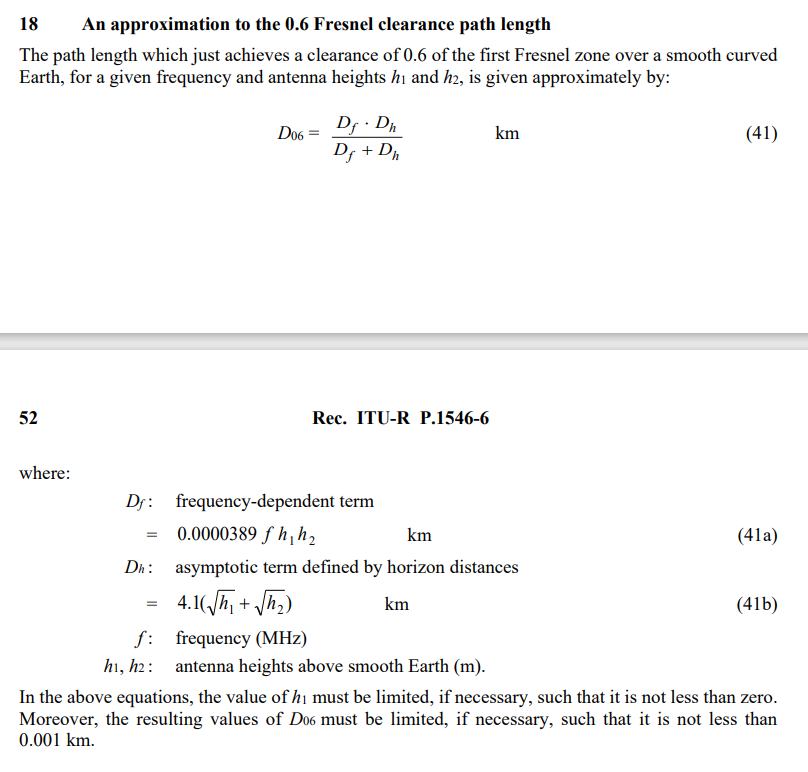

function D = D06(f,h1,h2)
    if (h1 < 0)
        h1 = 0;
    end
    Df = 0.0000389*f*h1*h2;             % equ'n (41a)
    Dh = 4.1*(sqrt(h1)+sqrt(h2));       % equ'n (41b)
    D = Df*Dh/(Df+Dh);                  % equ'n (41)
    if D < 0.001
        D = 0.001;
    end
end

### Função do cálculo do campo máximo

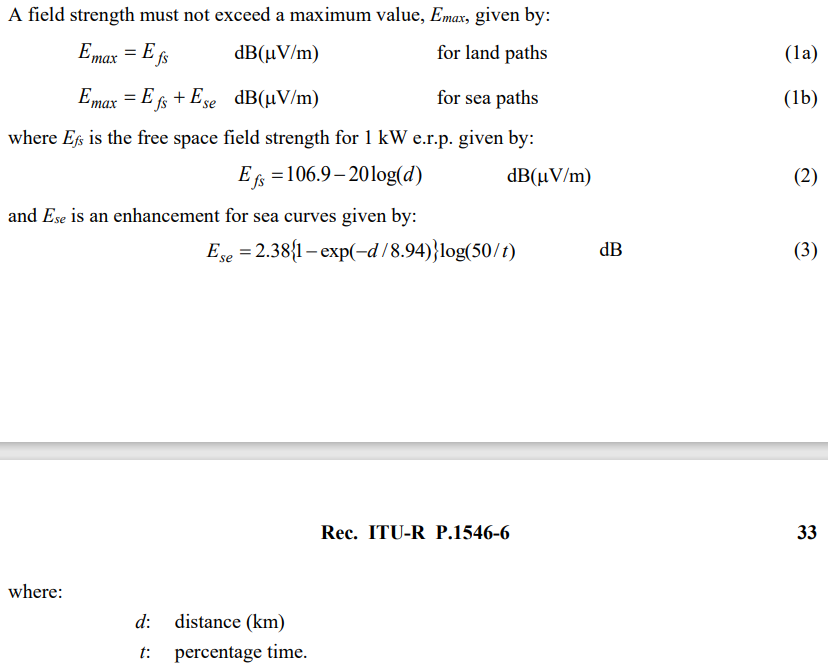

function Emax = Step_19a(t, dland, dsea, caminho_misto)
    dtotal=dland+dsea;
    
    Efs = 106.9-20*log10(dtotal); % (2)
    Ese=2.38*(1-exp(-dtotal/8.94))*log10(50/t); %(3)
    
    % Linearly interpolate between all-land and all-sea values:
    if caminho_misto == 1
        Emax=Efs+dsea*Ese/dtotal;  %(42)
    else
        if dsea == 0 % Se o caminho não for misto, e for só de terra
            Emax = Efs;
        else
            Emax = Efs + Ese;
        end
    end
end 

% Step 11: If the prediction is for a mixed path, follow the step-by-step procedure given in Annex 5, 
% § 8. This requires use of Steps 6 to 10 for paths of each propagation type. 

### Função para cálculo do campo para caminho misto

The following description of the mixed-path method uses Eland(d) and Esea(d) to represent the field  strength at distance d from the transmitting/base antenna at the representative clutter height at the  receiving/mobile antenna, R2, for all-land and all-sea paths respectively, with  interpolation/extrapolation for transmitting/base antenna height h1, frequency and percentage time, as  required.

% Fsea -> Tamanho no mar/tamanho total
function [E] = mixed_paths(Fsea,Eland, Esea)
    A0_Fsea = 1 - (1-Fsea)^(2/3);
    delta = Esea - Eland;
    V = max(linspace(1, 1+(delta/40)));
    A = A0_Fsea^V;
    E = (1-A) * Eland + A*Esea;
end

function Jv = Jl(v)
    Jv = (6.9+20*log10(sqrt(((v-0.1)^2) + 1)+v-0.1));
end

theta_eff = 0.5500

tca_receptor = 0.5500

lower_percentage = 10

higher_percentage = 50

lower_frequency = 100

higher_frequency = 600